This livescript intend to visualize the raw BOLD signal laminar dependency, the tSNR laminar dependency, and also the Z-scored BOLD, with special focus on the trial type itself.

It works with the output of the BK_ROI_creation_GROUPLVLactivationconj.m script. The output file is saved for each subject separately (see exact path below) and called interimdata_rwls_'roiname'raw.mat. The raw, sampled BOLD timeseries data from along all the vertex pairs within the ROI. There are two images here, one is the raw BOLD signal laminar dependency in the whole ROI and only in the top 200 verte pairs (from which we make the inferences).

%check the bold response layerdependency
allsubj=[7349, 7356, 7361, 7375, 7376,...
         7383, 7402, 7403, 7404,...
         7405, 7408, 7414, 7415,...
         7425, 7426, 7433, 7434,...
         7435, 7443, 7444, 7445,...
         7448, 7449, 7452, 7453,...
         7454, 7455, 7456, 7457,...
         7468, 7469, 7482, 7484, 7485];




layermeans = zeros(20, length(allsubj));

myroiname='pIns';
hemisphere={'left' 'right'};
figurelocationpath='C:\Users\lenov\Documents\layerfMRI\E_stats\images\tomanuscipt\firstdrafts\supplementary\rawBOLDlaminardependency\';
for hemishperes=1:2
    figure('Position',[100, 100, 2400, 1200]);
    plotidx=0;
    for subj=allsubj
        rwdtmtrx=loadrawdatamatrix(subj,myroiname);
        
        % load('C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7402\functionalmasks\interimdata_rwls_DLPFCraw.mat')
        plotidx=plotidx+1;
        subplot(5,7,plotidx);
        tmpdata=rwdtmtrx.interimdata_columns{1,2}{hemishperes,1};
        vertexmean=squeeze(mean(tmpdata,1));
        layermean=mean(vertexmean,2)';
        plot(1:20, layermean, '-r', 'LineWidth', 1);
        hold on
        errorbar(1:20, layermean, std(vertexmean, [], 2), 'k');
        
    
        title([ 'Subject ' num2str(subj)]);  % add a title to each subplot
        hold off
        layermeans(:, plotidx) = layermean;
    end
    
    saveas(gcf, [figurelocationpath myroiname hemisphere{hemishperes} 'layer_mean_std_eachsubj.jpg'], 'jpeg');
    
    
    figure;  % create a new figure to visualize the layermean matrix
    plot(1:20, mean(layermeans, 2), '-r', 'LineWidth', 1);
    hold on
    errorbar(1:20, mean(layermeans, 2), std(layermeans, [], 2), 'k');
    hold off
    xlabel('laminar depth (WM to CSF)');
    ylabel(' raw BOLD signal');
    title('Grand average across subjects');
    saveas(gcf, [figurelocationpath myroiname hemisphere{hemishperes} 'layer_mean_std_subjavg.jpg'], 'jpeg');
end

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7349\functionalmasks\interimdata_rwls_pInsraw.mat


Raw BOLD and also tSNR BOLD for all or only a selected number of vertices (200 is hard coded).

plotidx=0;
subplotsize=[8 4];
allsubjlayer={};
topcolumnnumber=200; %used this previously
layermeans = zeros(20, length(allsubj));

myroiname='S1';
hemisphere={'left' 'right'};
figuretype='tSNR'; %possible input: 'raw', 'tSNR', 
figurelocationpath=['C:\Users\lenov\Documents\layerfMRI\E_stats\images\tomanuscipt\firstdrafts\supplementary\' figuretype 'BOLDlaminardependency\';]

figurelocationpath = 'C:\Users\lenov\Documents\layerfMRI\E_stats\images\tomanuscipt\firstdrafts\supplementary\tSNRBOLDlaminardependency\'

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7349\functionalmasks\interimdata_rwls_S1raw.mat


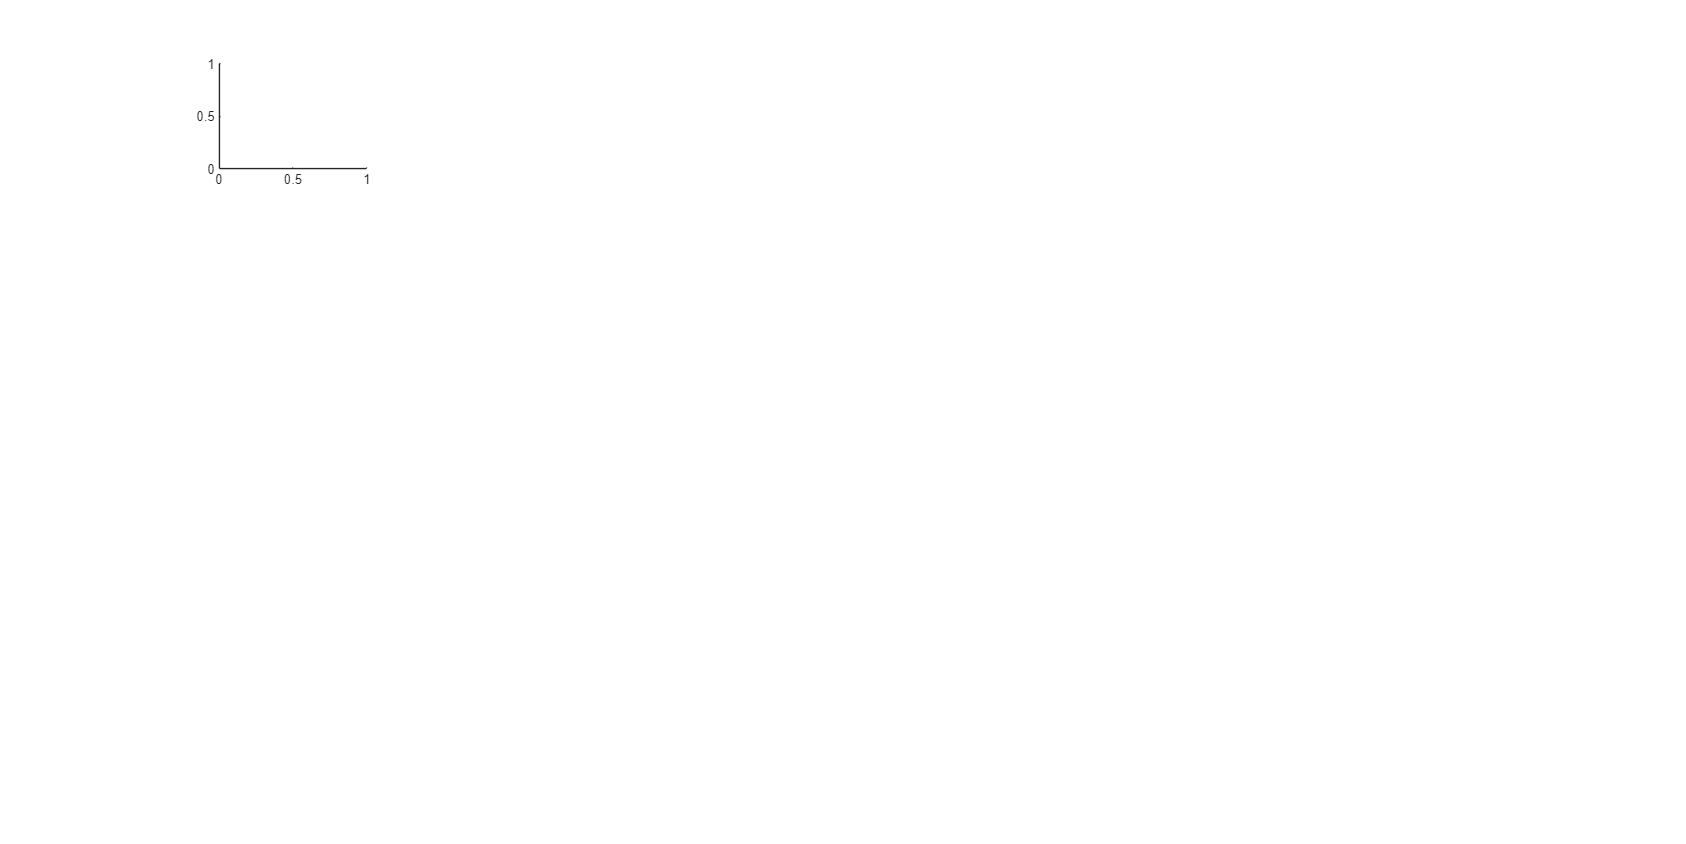

clustersize=0;
for hemishperes=1:2
    figure('Position',[100, 100, 2400, 1200]);
    plotidx=0;
    for subj=allsubj
    %     roipath='C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\';
        rwdtmtrx=loadrawdatamatrix(subj,myroiname);
    %     columnartsfile=[roipath num2str(subj{:}) '\functionalmasks\interimdata_rwls_' myroiname 'raw.mat'];
    %     if exist(columnartsfile,"file")
    %         disp([num2str(subj{:}) ' subject columnar info r'])
    %         plotidx=plotidx+1;
    plotidx=plotidx+1;
    subplot(5,7,plotidx);
    if clustersize==200
            [columnwisestat,~,~]=BK_layer_sampling_pain_study_pipeline(num2cell(subj),'glmestimate',myroiname,'raw','no','maineff');
    %         allsubjid(plotidx)=subj{:};
    %         allsubjlayer{plotidx}=layerwisestat;
    %         allsubjcoldistr{plotidx}=columndistribution;
    %         allsubjstat{plotidx}=stat;
            [top200Values, top200Indices] =maxk(columnwisestat(hemishperes).T(:,3),topcolumnnumber);
            
            % Filter the indices where the values are positive
            positiveIndices = top200Indices(top200Values > 0);
            % Check if any negative values were removed
            if length(positiveIndices) < topcolumnnumber
                warning('The top 200 values contained negative numbers. Only %d positive values are retained.', length(positiveIndices));
            end
            
            tmpdata=rwdtmtrx.interimdata_columns{1,2}{hemishperes,1};
            tmpdata=tmpdata(positiveIndices,:,:);
    elseif clustersize==0
        tmpdata=rwdtmtrx.interimdata_columns{1,2}{hemishperes,1};
    end
     
            vertexmean=squeeze(mean(tmpdata,1));
            noise_std = std(vertexmean, 0, 2);
            layermean=mean(vertexmean,2);
            tSNR=layermean./noise_std;
            if strcmp(figuretype,'raw')
                imagedata=layermean;
                plot(1:20, imagedata', '-r', 'LineWidth', 1);                
                hold on
                errorbar(1:20, imagedata', noise_std, 'k');
            elseif strcmp(figuretype,'tSNR')
                imagedata=tSNR;
                plot(1:20, imagedata', '-r', 'LineWidth', 1);
            end
            
            
        
            title([ 'Subject ' num2str(subj)]);  % add a title to each subplot
            hold off
            layermeans(:, plotidx) = imagedata';
    %     else
    %         disp([num2str(subj{:}) ' subject has  no sampled cluster'])
    %     end
    
    end
    saveas(gcf, [figurelocationpath myroiname hemisphere{hemishperes} figuretype 'layer' num2str(clustersize) 'vertices_mean_std_eachsubj.jpg'], 'jpeg');
    
    
    figure;  % create a new figure to visualize the layermean matrix
    plot(1:20, mean(layermeans, 2), '-r', 'LineWidth', 1);
    hold on
    errorbar(1:20, mean(layermeans, 2), std(layermeans, [], 2), 'k');
    hold off
    xlabel('laminar depth (WM to CSF)');
    ylabel(' raw BOLD signal');
    title('Grand average across subjects');
    saveas(gcf, [figurelocationpath myroiname hemisphere{hemishperes} figuretype 'layer' num2str(clustersize) 'vertices_mean_std_subjavg.jpg'], 'jpeg');
end

Trialwise timeseires (TS) from the raw BOLD data in all the voxels and in a subset of voxels(200 harcoded).

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7349\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7349The number of columns within the funcitonal mask: 769
Subject:7349The percent/number of columns acitvating in each run(t>0) for cognition: 27%/206
Subject:7349The percent/number of columns acitvating in each run(t>0) for pain: 64%/496
Subject:7349The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 19%/143
-------------------------------------------------------------
Subject:7349The number of columns within the funcitonal mask: 769
Subject:7349The percent/number of columns acitvating in each run(t>1) for cognition: 7%/50
Subject:7349The percent/number of columns acitvating in each run(t>1) for pain: 27%/206
Subject:7349The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 2%/19
-------------------------------------------------------------


Subject:7349The number of columns within the funcitonal mask: 1865
Subject:7349The percent/number of columns acitvating in each run(t>0) for cognition: 35%/658
Subject:7349The percent/number of columns acitvating in each run(t>0) for pain: 68%/1265
Subject:7349The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 25%/465
-------------------------------------------------------------
Subject:7349The number of columns within the funcitonal mask: 1865
Subject:7349The percent/number of columns acitvating in each run(t>1) for cognition: 13%/237
Subject:7349The percent/number of columns acitvating in each run(t>1) for pain: 36%/671
Subject:7349The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 6%/113
-------------------------------------------------------------
time for laminar activation:Elapsed time is 6.300177 seconds.
Time for one subject to process:Elapsed time is 6.353667 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7356\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7356The number of columns within the funcitonal mask: 691
Subject:7356The percent/number of columns acitvating in each run(t>0) for cognition: 61%/421
Subject:7356The percent/number of columns acitvating in each run(t>0) for pain: 45%/314
Subject:7356The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 27%/188
-------------------------------------------------------------
Subject:7356The number of columns within the funcitonal mask: 691
Subject:7356The percent/number of columns acitvating in each run(t>1) for cognition: 25%/171
Subject:7356The percent/number of columns acitvating in each run(t>1) for pain: 16%/108
Subject:7356The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/24
-------------------------------------------------------------


Subject:7356The number of columns within the funcitonal mask: 1383
Subject:7356The percent/number of columns acitvating in each run(t>0) for cognition: 58%/807
Subject:7356The percent/number of columns acitvating in each run(t>0) for pain: 47%/649
Subject:7356The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 28%/393
-------------------------------------------------------------
Subject:7356The number of columns within the funcitonal mask: 1383
Subject:7356The percent/number of columns acitvating in each run(t>1) for cognition: 23%/322
Subject:7356The percent/number of columns acitvating in each run(t>1) for pain: 16%/215
Subject:7356The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/51
-------------------------------------------------------------
time for laminar activation:Elapsed time is 4.364404 seconds.
Time for one subject to process:Elapsed time is 4.401587 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7361\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7361The number of columns within the funcitonal mask: 749
Subject:7361The percent/number of columns acitvating in each run(t>0) for cognition: 50%/378
Subject:7361The percent/number of columns acitvating in each run(t>0) for pain: 73%/550
Subject:7361The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 38%/287
-------------------------------------------------------------
Subject:7361The number of columns within the funcitonal mask: 749
Subject:7361The percent/number of columns acitvating in each run(t>1) for cognition: 17%/128
Subject:7361The percent/number of columns acitvating in each run(t>1) for pain: 39%/293
Subject:7361The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 8%/60
-------------------------------------------------------------
Subject:7361The number of columns within the funcitonal mask: 1748
Subject:7361The percent/number of columns acitvating in each run(t>0) for cognition: 47%/824
Subject:7361The perc

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7375\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7375The number of columns within the funcitonal mask: 699
Subject:7375The percent/number of columns acitvating in each run(t>0) for cognition: 51%/354
Subject:7375The percent/number of columns acitvating in each run(t>0) for pain: 41%/288
Subject:7375The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 24%/171
-------------------------------------------------------------
Subject:7375The number of columns within the funcitonal mask: 699
Subject:7375The percent/number of columns acitvating in each run(t>1) for cognition: 18%/124
Subject:7375The percent/number of columns acitvating in each run(t>1) for pain: 16%/109
Subject:7375The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/26
-------------------------------------------------------------


Subject:7375The number of columns within the funcitonal mask: 1876
Subject:7375The percent/number of columns acitvating in each run(t>0) for cognition: 45%/841
Subject:7375The percent/number of columns acitvating in each run(t>0) for pain: 58%/1080
Subject:7375The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 27%/504
-------------------------------------------------------------
Subject:7375The number of columns within the funcitonal mask: 1876
Subject:7375The percent/number of columns acitvating in each run(t>1) for cognition: 14%/272
Subject:7375The percent/number of columns acitvating in each run(t>1) for pain: 25%/467
Subject:7375The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 5%/85
-------------------------------------------------------------
time for laminar activation:Elapsed time is 5.105193 seconds.
Time for one subject to process:Elapsed time is 5.149770 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7376\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7376The number of columns within the funcitonal mask: 803
Subject:7376The percent/number of columns acitvating in each run(t>0) for cognition: 57%/458
Subject:7376The percent/number of columns acitvating in each run(t>0) for pain: 64%/510
Subject:7376The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 36%/286
-------------------------------------------------------------
Subject:7376The number of columns within the funcitonal mask: 803
Subject:7376The percent/number of columns acitvating in each run(t>1) for cognition: 20%/162
Subject:7376The percent/number of columns acitvating in each run(t>1) for pain: 27%/219
Subject:7376The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 5%/40
-------------------------------------------------------------
Subject:7376The number of columns within the funcitonal mask: 1683
Subject:7376The percent/number of columns acitvating in each run(t>0) for cognition: 46%/774
Subject:7376The perc

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7383\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7383The number of columns within the funcitonal mask: 864
Subject:7383The percent/number of columns acitvating in each run(t>0) for cognition: 67%/575
Subject:7383The percent/number of columns acitvating in each run(t>0) for pain: 45%/391
Subject:7383The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 28%/239
-------------------------------------------------------------
Subject:7383The number of columns within the funcitonal mask: 864
Subject:7383The percent/number of columns acitvating in each run(t>1) for cognition: 33%/288
Subject:7383The percent/number of columns acitvating in each run(t>1) for pain: 15%/133
Subject:7383The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/31
-------------------------------------------------------------
Subject:7383The number of columns within the funcitonal mask: 1655
Subject:7383The percent/number of columns acitvating in each run(t>0) for cognition: 60%/999
Subject:7383The perc

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7402\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7402The number of columns within the funcitonal mask: 1475
Subject:7402The percent/number of columns acitvating in each run(t>0) for cognition: 70%/1038
Subject:7402The percent/number of columns acitvating in each run(t>0) for pain: 36%/533
Subject:7402The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 25%/369
-------------------------------------------------------------
Subject:7402The number of columns within the funcitonal mask: 1475
Subject:7402The percent/number of columns acitvating in each run(t>1) for cognition: 34%/503
Subject:7402The percent/number of columns acitvating in each run(t>1) for pain: 9%/130
Subject:7402The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 2%/24
-------------------------------------------------------------
Subject:7402The number of columns within the funcitonal mask: 3258
Subject:7402The percent/number of columns acitvating in each run(t>0) for cognition: 79%/2582
Subject:7402The p

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7403\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7403The number of columns within the funcitonal mask: 792
Subject:7403The percent/number of columns acitvating in each run(t>0) for cognition: 57%/455
Subject:7403The percent/number of columns acitvating in each run(t>0) for pain: 39%/312
Subject:7403The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 23%/181
-------------------------------------------------------------
Subject:7403The number of columns within the funcitonal mask: 792
Subject:7403The percent/number of columns acitvating in each run(t>1) for cognition: 20%/161
Subject:7403The percent/number of columns acitvating in each run(t>1) for pain: 9%/68
Subject:7403The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 2%/17
-------------------------------------------------------------


Subject:7403The number of columns within the funcitonal mask: 1905
Subject:7403The percent/number of columns acitvating in each run(t>0) for cognition: 54%/1028
Subject:7403The percent/number of columns acitvating in each run(t>0) for pain: 43%/816
Subject:7403The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 22%/416
-------------------------------------------------------------
Subject:7403The number of columns within the funcitonal mask: 1905
Subject:7403The percent/number of columns acitvating in each run(t>1) for cognition: 21%/391
Subject:7403The percent/number of columns acitvating in each run(t>1) for pain: 13%/242
Subject:7403The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/48
-------------------------------------------------------------
time for laminar activation:Elapsed time is 6.005750 seconds.
Time for one subject to process:Elapsed time is 6.074162 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7404\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7404The number of columns within the funcitonal mask: 749
Subject:7404The percent/number of columns acitvating in each run(t>0) for cognition: 60%/446
Subject:7404The percent/number of columns acitvating in each run(t>0) for pain: 50%/378
Subject:7404The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 30%/221
-------------------------------------------------------------
Subject:7404The number of columns within the funcitonal mask: 749
Subject:7404The percent/number of columns acitvating in each run(t>1) for cognition: 26%/192
Subject:7404The percent/number of columns acitvating in each run(t>1) for pain: 20%/148
Subject:7404The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 5%/34
-------------------------------------------------------------
Subject:7404The number of columns within the funcitonal mask: 1443
Subject:7404The percent/number of columns acitvating in each run(t>0) for cognition: 61%/883
Subject:7404The perc

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7405\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7405The number of columns within the funcitonal mask: 738
Subject:7405The percent/number of columns acitvating in each run(t>0) for cognition: 80%/591
Subject:7405The percent/number of columns acitvating in each run(t>0) for pain: 60%/442
Subject:7405The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 48%/353
-------------------------------------------------------------
Subject:7405The number of columns within the funcitonal mask: 738
Subject:7405The percent/number of columns acitvating in each run(t>1) for cognition: 51%/375
Subject:7405The percent/number of columns acitvating in each run(t>1) for pain: 22%/159
Subject:7405The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 11%/80
-------------------------------------------------------------
Subject:7405The number of columns within the funcitonal mask: 1352
Subject:7405The percent/number of columns acitvating in each run(t>0) for cognition: 83%/1117
Subject:7405The pe

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7408\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7408The number of columns within the funcitonal mask: 867
Subject:7408The percent/number of columns acitvating in each run(t>0) for cognition: 62%/537
Subject:7408The percent/number of columns acitvating in each run(t>0) for pain: 43%/370
Subject:7408The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 25%/214
-------------------------------------------------------------
Subject:7408The number of columns within the funcitonal mask: 867
Subject:7408The percent/number of columns acitvating in each run(t>1) for cognition: 25%/218
Subject:7408The percent/number of columns acitvating in each run(t>1) for pain: 13%/117
Subject:7408The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/28
-------------------------------------------------------------
Subject:7408The number of columns within the funcitonal mask: 2238
Subject:7408The percent/number of columns acitvating in each run(t>0) for cognition: 72%/1610
Subject:7408The per

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7414\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7414The number of columns within the funcitonal mask: 738
Subject:7414The percent/number of columns acitvating in each run(t>0) for cognition: 59%/433
Subject:7414The percent/number of columns acitvating in each run(t>0) for pain: 56%/412
Subject:7414The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 32%/237
-------------------------------------------------------------
Subject:7414The number of columns within the funcitonal mask: 738
Subject:7414The percent/number of columns acitvating in each run(t>1) for cognition: 24%/175
Subject:7414The percent/number of columns acitvating in each run(t>1) for pain: 20%/144
Subject:7414The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 5%/35
-------------------------------------------------------------
Subject:7414The number of columns within the funcitonal mask: 1669
Subject:7414The percent/number of columns acitvating in each run(t>0) for cognition: 59%/977
Subject:7414The perc

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7415\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7415The number of columns within the funcitonal mask: 777
Subject:7415The percent/number of columns acitvating in each run(t>0) for cognition: 44%/339
Subject:7415The percent/number of columns acitvating in each run(t>0) for pain: 33%/257
Subject:7415The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 16%/124
-------------------------------------------------------------
Subject:7415The number of columns within the funcitonal mask: 777
Subject:7415The percent/number of columns acitvating in each run(t>1) for cognition: 15%/114
Subject:7415The percent/number of columns acitvating in each run(t>1) for pain: 8%/59
Subject:7415The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 1%/7
-------------------------------------------------------------


Subject:7415The number of columns within the funcitonal mask: 1925
Subject:7415The percent/number of columns acitvating in each run(t>0) for cognition: 42%/806
Subject:7415The percent/number of columns acitvating in each run(t>0) for pain: 38%/726
Subject:7415The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 18%/344
-------------------------------------------------------------
Subject:7415The number of columns within the funcitonal mask: 1925
Subject:7415The percent/number of columns acitvating in each run(t>1) for cognition: 13%/255
Subject:7415The percent/number of columns acitvating in each run(t>1) for pain: 11%/204
Subject:7415The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/50
-------------------------------------------------------------
time for laminar activation:Elapsed time is 4.733813 seconds.
Time for one subject to process:Elapsed time is 4.787919 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7425\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7425The number of columns within the funcitonal mask: 615
Subject:7425The percent/number of columns acitvating in each run(t>0) for cognition: 50%/309
Subject:7425The percent/number of columns acitvating in each run(t>0) for pain: 55%/337
Subject:7425The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 32%/195
-------------------------------------------------------------
Subject:7425The number of columns within the funcitonal mask: 615
Subject:7425The percent/number of columns acitvating in each run(t>1) for cognition: 24%/146
Subject:7425The percent/number of columns acitvating in each run(t>1) for pain: 21%/129
Subject:7425The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 8%/49
-------------------------------------------------------------


Subject:7425The number of columns within the funcitonal mask: 1546
Subject:7425The percent/number of columns acitvating in each run(t>0) for cognition: 46%/714
Subject:7425The percent/number of columns acitvating in each run(t>0) for pain: 50%/779
Subject:7425The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 25%/391
-------------------------------------------------------------
Subject:7425The number of columns within the funcitonal mask: 1546
Subject:7425The percent/number of columns acitvating in each run(t>1) for cognition: 17%/260
Subject:7425The percent/number of columns acitvating in each run(t>1) for pain: 18%/277
Subject:7425The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/56
-------------------------------------------------------------
time for laminar activation:Elapsed time is 4.305334 seconds.
Time for one subject to process:Elapsed time is 4.346813 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7426\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7426The number of columns within the funcitonal mask: 896
Subject:7426The percent/number of columns acitvating in each run(t>0) for cognition: 69%/622
Subject:7426The percent/number of columns acitvating in each run(t>0) for pain: 48%/430
Subject:7426The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 33%/296
-------------------------------------------------------------
Subject:7426The number of columns within the funcitonal mask: 896
Subject:7426The percent/number of columns acitvating in each run(t>1) for cognition: 35%/317
Subject:7426The percent/number of columns acitvating in each run(t>1) for pain: 15%/137
Subject:7426The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 5%/46
-------------------------------------------------------------
Subject:7426The number of columns within the funcitonal mask: 1694
Subject:7426The percent/number of columns acitvating in each run(t>0) for cognition: 60%/1008
Subject:7426The per

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7433\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7433The number of columns within the funcitonal mask: 835
Subject:7433The percent/number of columns acitvating in each run(t>0) for cognition: 46%/385
Subject:7433The percent/number of columns acitvating in each run(t>0) for pain: 51%/423
Subject:7433The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 23%/188
-------------------------------------------------------------
Subject:7433The number of columns within the funcitonal mask: 835
Subject:7433The percent/number of columns acitvating in each run(t>1) for cognition: 15%/127
Subject:7433The percent/number of columns acitvating in each run(t>1) for pain: 17%/146
Subject:7433The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/23
-------------------------------------------------------------


Subject:7433The number of columns within the funcitonal mask: 1461
Subject:7433The percent/number of columns acitvating in each run(t>0) for cognition: 46%/671
Subject:7433The percent/number of columns acitvating in each run(t>0) for pain: 49%/711
Subject:7433The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 23%/332
-------------------------------------------------------------
Subject:7433The number of columns within the funcitonal mask: 1461
Subject:7433The percent/number of columns acitvating in each run(t>1) for cognition: 15%/218
Subject:7433The percent/number of columns acitvating in each run(t>1) for pain: 18%/258
Subject:7433The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/38
-------------------------------------------------------------
time for laminar activation:Elapsed time is 4.062293 seconds.
Time for one subject to process:Elapsed time is 4.123355 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7434\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7434The number of columns within the funcitonal mask: 726
Subject:7434The percent/number of columns acitvating in each run(t>0) for cognition: 75%/548
Subject:7434The percent/number of columns acitvating in each run(t>0) for pain: 60%/432
Subject:7434The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 47%/338
-------------------------------------------------------------
Subject:7434The number of columns within the funcitonal mask: 726
Subject:7434The percent/number of columns acitvating in each run(t>1) for cognition: 36%/258
Subject:7434The percent/number of columns acitvating in each run(t>1) for pain: 22%/162
Subject:7434The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 8%/57
-------------------------------------------------------------
Subject:7434The number of columns within the funcitonal mask: 1488
Subject:7434The percent/number of columns acitvating in each run(t>0) for cognition: 61%/904
Subject:7434The perc

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7435\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7435The number of columns within the funcitonal mask: 737
Subject:7435The percent/number of columns acitvating in each run(t>0) for cognition: 67%/495
Subject:7435The percent/number of columns acitvating in each run(t>0) for pain: 42%/308
Subject:7435The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 27%/202
-------------------------------------------------------------
Subject:7435The number of columns within the funcitonal mask: 737
Subject:7435The percent/number of columns acitvating in each run(t>1) for cognition: 34%/249
Subject:7435The percent/number of columns acitvating in each run(t>1) for pain: 10%/73
Subject:7435The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/27
-------------------------------------------------------------
Subject:7435The number of columns within the funcitonal mask: 1336
Subject:7435The percent/number of columns acitvating in each run(t>0) for cognition: 77%/1027
Subject:7435The perc

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7443\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7443The number of columns within the funcitonal mask: 897
Subject:7443The percent/number of columns acitvating in each run(t>0) for cognition: 62%/552
Subject:7443The percent/number of columns acitvating in each run(t>0) for pain: 57%/515
Subject:7443The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 35%/316
-------------------------------------------------------------
Subject:7443The number of columns within the funcitonal mask: 897
Subject:7443The percent/number of columns acitvating in each run(t>1) for cognition: 26%/236
Subject:7443The percent/number of columns acitvating in each run(t>1) for pain: 23%/205
Subject:7443The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 6%/53
-------------------------------------------------------------
Subject:7443The number of columns within the funcitonal mask: 1369
Subject:7443The percent/number of columns acitvating in each run(t>0) for cognition: 51%/695
Subject:7443The perc

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7444\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7444The number of columns within the funcitonal mask: 976
Subject:7444The percent/number of columns acitvating in each run(t>0) for cognition: 70%/683
Subject:7444The percent/number of columns acitvating in each run(t>0) for pain: 59%/573
Subject:7444The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 41%/397
-------------------------------------------------------------
Subject:7444The number of columns within the funcitonal mask: 976
Subject:7444The percent/number of columns acitvating in each run(t>1) for cognition: 36%/354
Subject:7444The percent/number of columns acitvating in each run(t>1) for pain: 20%/193
Subject:7444The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 7%/69
-------------------------------------------------------------
Subject:7444The number of columns within the funcitonal mask: 2159
Subject:7444The percent/number of columns acitvating in each run(t>0) for cognition: 76%/1648
Subject:7444The per

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7445\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7445The number of columns within the funcitonal mask: 692
Subject:7445The percent/number of columns acitvating in each run(t>0) for cognition: 53%/365
Subject:7445The percent/number of columns acitvating in each run(t>0) for pain: 48%/331
Subject:7445The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 23%/159
-------------------------------------------------------------
Subject:7445The number of columns within the funcitonal mask: 692
Subject:7445The percent/number of columns acitvating in each run(t>1) for cognition: 22%/152
Subject:7445The percent/number of columns acitvating in each run(t>1) for pain: 16%/109
Subject:7445The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 2%/13
-------------------------------------------------------------


Subject:7445The number of columns within the funcitonal mask: 1635
Subject:7445The percent/number of columns acitvating in each run(t>0) for cognition: 51%/826
Subject:7445The percent/number of columns acitvating in each run(t>0) for pain: 52%/852
Subject:7445The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 26%/430
-------------------------------------------------------------
Subject:7445The number of columns within the funcitonal mask: 1635
Subject:7445The percent/number of columns acitvating in each run(t>1) for cognition: 19%/303
Subject:7445The percent/number of columns acitvating in each run(t>1) for pain: 17%/275
Subject:7445The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/44
-------------------------------------------------------------
time for laminar activation:Elapsed time is 4.038239 seconds.
Time for one subject to process:Elapsed time is 4.090148 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7448\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7448The number of columns within the funcitonal mask: 980
Subject:7448The percent/number of columns acitvating in each run(t>0) for cognition: 75%/733
Subject:7448The percent/number of columns acitvating in each run(t>0) for pain: 61%/595
Subject:7448The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 48%/466
-------------------------------------------------------------
Subject:7448The number of columns within the funcitonal mask: 980
Subject:7448The percent/number of columns acitvating in each run(t>1) for cognition: 38%/371
Subject:7448The percent/number of columns acitvating in each run(t>1) for pain: 27%/260
Subject:7448The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 12%/113
-------------------------------------------------------------
Subject:7448The number of columns within the funcitonal mask: 1698
Subject:7448The percent/number of columns acitvating in each run(t>0) for cognition: 74%/1259
Subject:7448The p

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7449\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7449The number of columns within the funcitonal mask: 963
Subject:7449The percent/number of columns acitvating in each run(t>0) for cognition: 53%/508
Subject:7449The percent/number of columns acitvating in each run(t>0) for pain: 38%/369
Subject:7449The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 21%/206
-------------------------------------------------------------
Subject:7449The number of columns within the funcitonal mask: 963
Subject:7449The percent/number of columns acitvating in each run(t>1) for cognition: 20%/191
Subject:7449The percent/number of columns acitvating in each run(t>1) for pain: 10%/101
Subject:7449The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 2%/22
-------------------------------------------------------------
Subject:7449The number of columns within the funcitonal mask: 1652
Subject:7449The percent/number of columns acitvating in each run(t>0) for cognition: 50%/818
Subject:7449The perc

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7452\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7452The number of columns within the funcitonal mask: 866
Subject:7452The percent/number of columns acitvating in each run(t>0) for cognition: 58%/502
Subject:7452The percent/number of columns acitvating in each run(t>0) for pain: 46%/398
Subject:7452The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 26%/225
-------------------------------------------------------------
Subject:7452The number of columns within the funcitonal mask: 866
Subject:7452The percent/number of columns acitvating in each run(t>1) for cognition: 23%/196
Subject:7452The percent/number of columns acitvating in each run(t>1) for pain: 13%/114
Subject:7452The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 2%/19
-------------------------------------------------------------
Subject:7452The number of columns within the funcitonal mask: 1462
Subject:7452The percent/number of columns acitvating in each run(t>0) for cognition: 53%/775
Subject:7452The perc

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7453\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7453The number of columns within the funcitonal mask: 870
Subject:7453The percent/number of columns acitvating in each run(t>0) for cognition: 48%/416
Subject:7453The percent/number of columns acitvating in each run(t>0) for pain: 53%/465
Subject:7453The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 28%/245
-------------------------------------------------------------
Subject:7453The number of columns within the funcitonal mask: 870
Subject:7453The percent/number of columns acitvating in each run(t>1) for cognition: 17%/148
Subject:7453The percent/number of columns acitvating in each run(t>1) for pain: 16%/141
Subject:7453The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/30
-------------------------------------------------------------
Subject:7453The number of columns within the funcitonal mask: 1679
Subject:7453The percent/number of columns acitvating in each run(t>0) for cognition: 47%/793
Subject:7453The perc

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7454\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7454The number of columns within the funcitonal mask: 832
Subject:7454The percent/number of columns acitvating in each run(t>0) for cognition: 62%/519
Subject:7454The percent/number of columns acitvating in each run(t>0) for pain: 50%/420
Subject:7454The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 29%/238
-------------------------------------------------------------
Subject:7454The number of columns within the funcitonal mask: 832
Subject:7454The percent/number of columns acitvating in each run(t>1) for cognition: 27%/224
Subject:7454The percent/number of columns acitvating in each run(t>1) for pain: 18%/146
Subject:7454The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/33
-------------------------------------------------------------
Subject:7454The number of columns within the funcitonal mask: 1689
Subject:7454The percent/number of columns acitvating in each run(t>0) for cognition: 64%/1078
Subject:7454The per

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7455\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7455The number of columns within the funcitonal mask: 748
Subject:7455The percent/number of columns acitvating in each run(t>0) for cognition: 51%/380
Subject:7455The percent/number of columns acitvating in each run(t>0) for pain: 62%/467
Subject:7455The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 31%/231
-------------------------------------------------------------
Subject:7455The number of columns within the funcitonal mask: 748
Subject:7455The percent/number of columns acitvating in each run(t>1) for cognition: 18%/136
Subject:7455The percent/number of columns acitvating in each run(t>1) for pain: 24%/177
Subject:7455The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 5%/34
-------------------------------------------------------------
Subject:7455The number of columns within the funcitonal mask: 1456
Subject:7455The percent/number of columns acitvating in each run(t>0) for cognition: 52%/762
Subject:7455The perc

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7456\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7456The number of columns within the funcitonal mask: 791
Subject:7456The percent/number of columns acitvating in each run(t>0) for cognition: 53%/421
Subject:7456The percent/number of columns acitvating in each run(t>0) for pain: 42%/336
Subject:7456The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 22%/173
-------------------------------------------------------------
Subject:7456The number of columns within the funcitonal mask: 791
Subject:7456The percent/number of columns acitvating in each run(t>1) for cognition: 22%/177
Subject:7456The percent/number of columns acitvating in each run(t>1) for pain: 12%/96
Subject:7456The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/21
-------------------------------------------------------------


Subject:7456The number of columns within the funcitonal mask: 1393
Subject:7456The percent/number of columns acitvating in each run(t>0) for cognition: 54%/753
Subject:7456The percent/number of columns acitvating in each run(t>0) for pain: 47%/660
Subject:7456The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 24%/338
-------------------------------------------------------------
Subject:7456The number of columns within the funcitonal mask: 1393
Subject:7456The percent/number of columns acitvating in each run(t>1) for cognition: 21%/296
Subject:7456The percent/number of columns acitvating in each run(t>1) for pain: 15%/211
Subject:7456The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/37
-------------------------------------------------------------
time for laminar activation:Elapsed time is 4.597149 seconds.
Time for one subject to process:Elapsed time is 4.645507 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7457\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7457The number of columns within the funcitonal mask: 788
Subject:7457The percent/number of columns acitvating in each run(t>0) for cognition: 61%/480
Subject:7457The percent/number of columns acitvating in each run(t>0) for pain: 49%/383
Subject:7457The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 29%/229
-------------------------------------------------------------
Subject:7457The number of columns within the funcitonal mask: 788
Subject:7457The percent/number of columns acitvating in each run(t>1) for cognition: 26%/205
Subject:7457The percent/number of columns acitvating in each run(t>1) for pain: 18%/138
Subject:7457The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/31
-------------------------------------------------------------
Subject:7457The number of columns within the funcitonal mask: 1480
Subject:7457The percent/number of columns acitvating in each run(t>0) for cognition: 57%/850
Subject:7457The perc

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7468\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7468The number of columns within the funcitonal mask: 706
Subject:7468The percent/number of columns acitvating in each run(t>0) for cognition: 51%/357
Subject:7468The percent/number of columns acitvating in each run(t>0) for pain: 58%/412
Subject:7468The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 30%/212
-------------------------------------------------------------
Subject:7468The number of columns within the funcitonal mask: 706
Subject:7468The percent/number of columns acitvating in each run(t>1) for cognition: 21%/150
Subject:7468The percent/number of columns acitvating in each run(t>1) for pain: 25%/177
Subject:7468The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 7%/47
-------------------------------------------------------------
Subject:7468The number of columns within the funcitonal mask: 1303
Subject:7468The percent/number of columns acitvating in each run(t>0) for cognition: 48%/622
Subject:7468The perc

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7469\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7469The number of columns within the funcitonal mask: 648
Subject:7469The percent/number of columns acitvating in each run(t>0) for cognition: 60%/389
Subject:7469The percent/number of columns acitvating in each run(t>0) for pain: 87%/566
Subject:7469The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 52%/338
-------------------------------------------------------------
Subject:7469The number of columns within the funcitonal mask: 648
Subject:7469The percent/number of columns acitvating in each run(t>1) for cognition: 26%/169
Subject:7469The percent/number of columns acitvating in each run(t>1) for pain: 65%/422
Subject:7469The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 16%/103
-------------------------------------------------------------
Subject:7469The number of columns within the funcitonal mask: 1483
Subject:7469The percent/number of columns acitvating in each run(t>0) for cognition: 54%/805
Subject:7469The pe

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7482\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7482The number of columns within the funcitonal mask: 870
Subject:7482The percent/number of columns acitvating in each run(t>0) for cognition: 66%/572
Subject:7482The percent/number of columns acitvating in each run(t>0) for pain: 52%/451
Subject:7482The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 32%/279
-------------------------------------------------------------
Subject:7482The number of columns within the funcitonal mask: 870
Subject:7482The percent/number of columns acitvating in each run(t>1) for cognition: 30%/263
Subject:7482The percent/number of columns acitvating in each run(t>1) for pain: 19%/161
Subject:7482The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/34
-------------------------------------------------------------
Subject:7482The number of columns within the funcitonal mask: 1628
Subject:7482The percent/number of columns acitvating in each run(t>0) for cognition: 70%/1134
Subject:7482The per

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7484\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7484The number of columns within the funcitonal mask: 794
Subject:7484The percent/number of columns acitvating in each run(t>0) for cognition: 59%/467
Subject:7484The percent/number of columns acitvating in each run(t>0) for pain: 53%/420
Subject:7484The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 30%/241
-------------------------------------------------------------
Subject:7484The number of columns within the funcitonal mask: 794
Subject:7484The percent/number of columns acitvating in each run(t>1) for cognition: 28%/226
Subject:7484The percent/number of columns acitvating in each run(t>1) for pain: 19%/148
Subject:7484The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 6%/44
-------------------------------------------------------------
Subject:7484The number of columns within the funcitonal mask: 1473
Subject:7484The percent/number of columns acitvating in each run(t>0) for cognition: 74%/1086
Subject:7484The per

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7485\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7485The number of columns within the funcitonal mask: 765
Subject:7485The percent/number of columns acitvating in each run(t>0) for cognition: 73%/562
Subject:7485The percent/number of columns acitvating in each run(t>0) for pain: 50%/381
Subject:7485The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 36%/274
-------------------------------------------------------------
Subject:7485The number of columns within the funcitonal mask: 765
Subject:7485The percent/number of columns acitvating in each run(t>1) for cognition: 40%/306
Subject:7485The percent/number of columns acitvating in each run(t>1) for pain: 19%/146
Subject:7485The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 7%/56
-------------------------------------------------------------
Subject:7485The number of columns within the funcitonal mask: 1323
Subject:7485The percent/number of columns acitvating in each run(t>0) for cognition: 67%/888
Subject:7485The perc

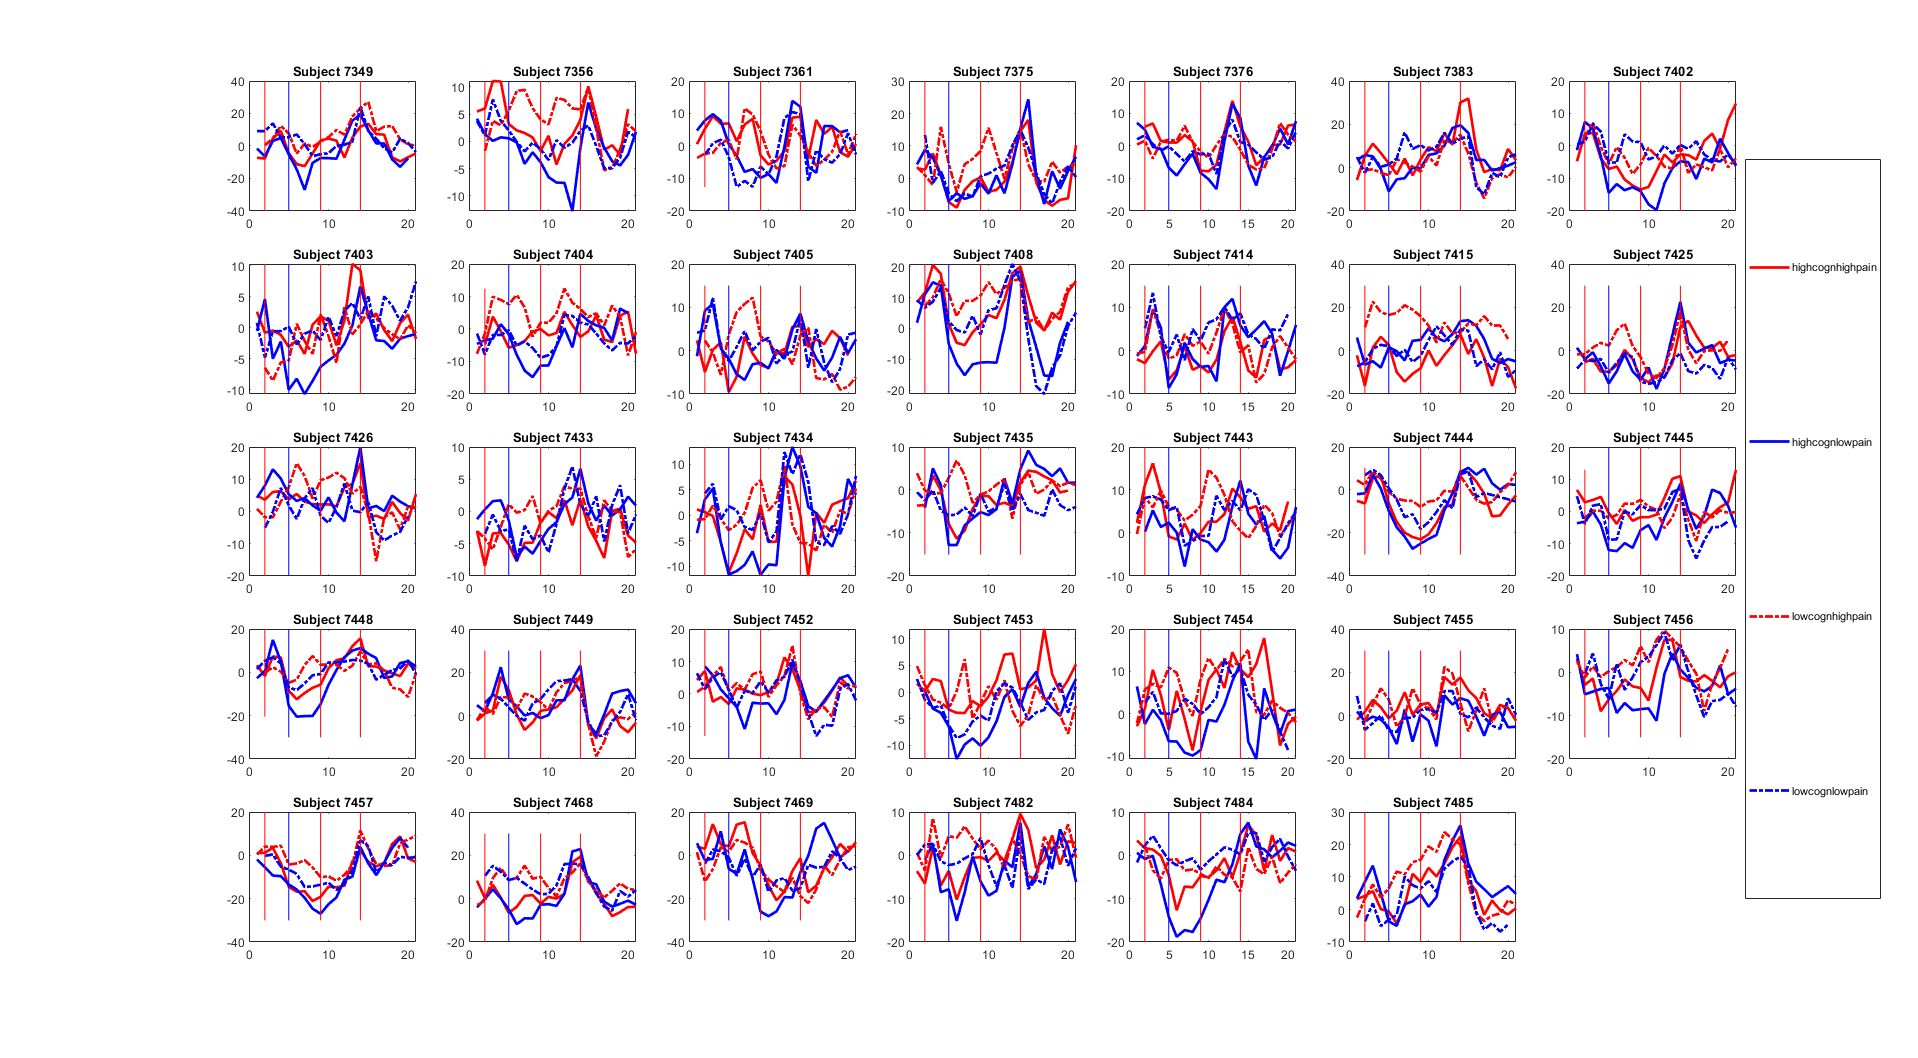

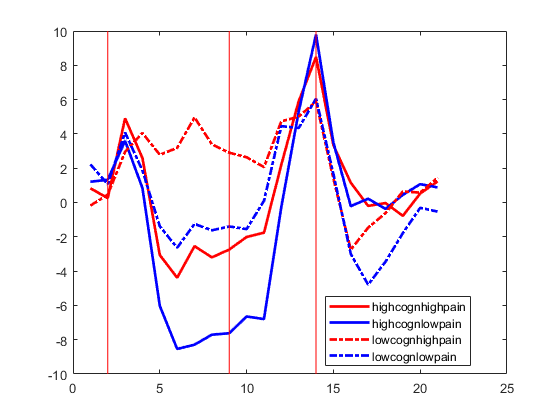

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7349\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7349The number of columns within the funcitonal mask: 769
Subject:7349The percent/number of columns acitvating in each run(t>0) for cognition: 27%/206
Subject:7349The percent/number of columns acitvating in each run(t>0) for pain: 64%/496
Subject:7349The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 19%/143
-------------------------------------------------------------
Subject:7349The number of columns within the funcitonal mask: 769
Subject:7349The percent/number of columns acitvating in each run(t>1) for cognition: 7%/50
Subject:7349The percent/number of columns acitvating in each run(t>1) for pain: 27%/206
Subject:7349The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 2%/19
-------------------------------------------------------------


Subject:7349The number of columns within the funcitonal mask: 1865
Subject:7349The percent/number of columns acitvating in each run(t>0) for cognition: 35%/658
Subject:7349The percent/number of columns acitvating in each run(t>0) for pain: 68%/1265
Subject:7349The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 25%/465
-------------------------------------------------------------
Subject:7349The number of columns within the funcitonal mask: 1865
Subject:7349The percent/number of columns acitvating in each run(t>1) for cognition: 13%/237
Subject:7349The percent/number of columns acitvating in each run(t>1) for pain: 36%/671
Subject:7349The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 6%/113
-------------------------------------------------------------
time for laminar activation:Elapsed time is 4.566510 seconds.
Time for one subject to process:Elapsed time is 4.632479 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7356\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7356The number of columns within the funcitonal mask: 691
Subject:7356The percent/number of columns acitvating in each run(t>0) for cognition: 61%/421
Subject:7356The percent/number of columns acitvating in each run(t>0) for pain: 45%/314
Subject:7356The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 27%/188
-------------------------------------------------------------
Subject:7356The number of columns within the funcitonal mask: 691
Subject:7356The percent/number of columns acitvating in each run(t>1) for cognition: 25%/171
Subject:7356The percent/number of columns acitvating in each run(t>1) for pain: 16%/108
Subject:7356The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/24
-------------------------------------------------------------


Subject:7356The number of columns within the funcitonal mask: 1383
Subject:7356The percent/number of columns acitvating in each run(t>0) for cognition: 58%/807
Subject:7356The percent/number of columns acitvating in each run(t>0) for pain: 47%/649
Subject:7356The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 28%/393
-------------------------------------------------------------
Subject:7356The number of columns within the funcitonal mask: 1383
Subject:7356The percent/number of columns acitvating in each run(t>1) for cognition: 23%/322
Subject:7356The percent/number of columns acitvating in each run(t>1) for pain: 16%/215
Subject:7356The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/51
-------------------------------------------------------------
time for laminar activation:Elapsed time is 3.836770 seconds.
Time for one subject to process:Elapsed time is 3.879508 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7361\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7361The number of columns within the funcitonal mask: 749
Subject:7361The percent/number of columns acitvating in each run(t>0) for cognition: 50%/378
Subject:7361The percent/number of columns acitvating in each run(t>0) for pain: 73%/550
Subject:7361The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 38%/287
-------------------------------------------------------------
Subject:7361The number of columns within the funcitonal mask: 749
Subject:7361The percent/number of columns acitvating in each run(t>1) for cognition: 17%/128
Subject:7361The percent/number of columns acitvating in each run(t>1) for pain: 39%/293
Subject:7361The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 8%/60
-------------------------------------------------------------
Subject:7361The number of columns within the funcitonal mask: 1748
Subject:7361The percent/number of columns acitvating in each run(t>0) for cognition: 47%/824
Subject:7361The perc

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7375\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7375The number of columns within the funcitonal mask: 699
Subject:7375The percent/number of columns acitvating in each run(t>0) for cognition: 51%/354
Subject:7375The percent/number of columns acitvating in each run(t>0) for pain: 41%/288
Subject:7375The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 24%/171
-------------------------------------------------------------
Subject:7375The number of columns within the funcitonal mask: 699
Subject:7375The percent/number of columns acitvating in each run(t>1) for cognition: 18%/124
Subject:7375The percent/number of columns acitvating in each run(t>1) for pain: 16%/109
Subject:7375The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/26
-------------------------------------------------------------


Subject:7375The number of columns within the funcitonal mask: 1876
Subject:7375The percent/number of columns acitvating in each run(t>0) for cognition: 45%/841
Subject:7375The percent/number of columns acitvating in each run(t>0) for pain: 58%/1080
Subject:7375The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 27%/504
-------------------------------------------------------------
Subject:7375The number of columns within the funcitonal mask: 1876
Subject:7375The percent/number of columns acitvating in each run(t>1) for cognition: 14%/272
Subject:7375The percent/number of columns acitvating in each run(t>1) for pain: 25%/467
Subject:7375The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 5%/85
-------------------------------------------------------------
time for laminar activation:Elapsed time is 4.299703 seconds.
Time for one subject to process:Elapsed time is 4.346617 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7376\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7376The number of columns within the funcitonal mask: 803
Subject:7376The percent/number of columns acitvating in each run(t>0) for cognition: 57%/458
Subject:7376The percent/number of columns acitvating in each run(t>0) for pain: 64%/510
Subject:7376The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 36%/286
-------------------------------------------------------------
Subject:7376The number of columns within the funcitonal mask: 803
Subject:7376The percent/number of columns acitvating in each run(t>1) for cognition: 20%/162
Subject:7376The percent/number of columns acitvating in each run(t>1) for pain: 27%/219
Subject:7376The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 5%/40
-------------------------------------------------------------
Subject:7376The number of columns within the funcitonal mask: 1683
Subject:7376The percent/number of columns acitvating in each run(t>0) for cognition: 46%/774
Subject:7376The perc

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7383\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7383The number of columns within the funcitonal mask: 864
Subject:7383The percent/number of columns acitvating in each run(t>0) for cognition: 67%/575
Subject:7383The percent/number of columns acitvating in each run(t>0) for pain: 45%/391
Subject:7383The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 28%/239
-------------------------------------------------------------
Subject:7383The number of columns within the funcitonal mask: 864
Subject:7383The percent/number of columns acitvating in each run(t>1) for cognition: 33%/288
Subject:7383The percent/number of columns acitvating in each run(t>1) for pain: 15%/133
Subject:7383The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/31
-------------------------------------------------------------
Subject:7383The number of columns within the funcitonal mask: 1655
Subject:7383The percent/number of columns acitvating in each run(t>0) for cognition: 60%/999
Subject:7383The perc

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7402\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7402The number of columns within the funcitonal mask: 1475
Subject:7402The percent/number of columns acitvating in each run(t>0) for cognition: 70%/1038
Subject:7402The percent/number of columns acitvating in each run(t>0) for pain: 36%/533
Subject:7402The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 25%/369
-------------------------------------------------------------
Subject:7402The number of columns within the funcitonal mask: 1475
Subject:7402The percent/number of columns acitvating in each run(t>1) for cognition: 34%/503
Subject:7402The percent/number of columns acitvating in each run(t>1) for pain: 9%/130
Subject:7402The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 2%/24
-------------------------------------------------------------
Subject:7402The number of columns within the funcitonal mask: 3258
Subject:7402The percent/number of columns acitvating in each run(t>0) for cognition: 79%/2582
Subject:7402The p

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7403\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7403The number of columns within the funcitonal mask: 792
Subject:7403The percent/number of columns acitvating in each run(t>0) for cognition: 57%/455
Subject:7403The percent/number of columns acitvating in each run(t>0) for pain: 39%/312
Subject:7403The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 23%/181
-------------------------------------------------------------
Subject:7403The number of columns within the funcitonal mask: 792
Subject:7403The percent/number of columns acitvating in each run(t>1) for cognition: 20%/161
Subject:7403The percent/number of columns acitvating in each run(t>1) for pain: 9%/68
Subject:7403The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 2%/17
-------------------------------------------------------------


Subject:7403The number of columns within the funcitonal mask: 1905
Subject:7403The percent/number of columns acitvating in each run(t>0) for cognition: 54%/1028
Subject:7403The percent/number of columns acitvating in each run(t>0) for pain: 43%/816
Subject:7403The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 22%/416
-------------------------------------------------------------
Subject:7403The number of columns within the funcitonal mask: 1905
Subject:7403The percent/number of columns acitvating in each run(t>1) for cognition: 21%/391
Subject:7403The percent/number of columns acitvating in each run(t>1) for pain: 13%/242
Subject:7403The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/48
-------------------------------------------------------------
time for laminar activation:Elapsed time is 4.202793 seconds.
Time for one subject to process:Elapsed time is 4.252563 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7404\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7404The number of columns within the funcitonal mask: 749
Subject:7404The percent/number of columns acitvating in each run(t>0) for cognition: 60%/446
Subject:7404The percent/number of columns acitvating in each run(t>0) for pain: 50%/378
Subject:7404The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 30%/221
-------------------------------------------------------------
Subject:7404The number of columns within the funcitonal mask: 749
Subject:7404The percent/number of columns acitvating in each run(t>1) for cognition: 26%/192
Subject:7404The percent/number of columns acitvating in each run(t>1) for pain: 20%/148
Subject:7404The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 5%/34
-------------------------------------------------------------
Subject:7404The number of columns within the funcitonal mask: 1443
Subject:7404The percent/number of columns acitvating in each run(t>0) for cognition: 61%/883
Subject:7404The perc

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7405\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7405The number of columns within the funcitonal mask: 738
Subject:7405The percent/number of columns acitvating in each run(t>0) for cognition: 80%/591
Subject:7405The percent/number of columns acitvating in each run(t>0) for pain: 60%/442
Subject:7405The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 48%/353
-------------------------------------------------------------
Subject:7405The number of columns within the funcitonal mask: 738
Subject:7405The percent/number of columns acitvating in each run(t>1) for cognition: 51%/375
Subject:7405The percent/number of columns acitvating in each run(t>1) for pain: 22%/159
Subject:7405The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 11%/80
-------------------------------------------------------------
Subject:7405The number of columns within the funcitonal mask: 1352
Subject:7405The percent/number of columns acitvating in each run(t>0) for cognition: 83%/1117
Subject:7405The pe

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7408\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7408The number of columns within the funcitonal mask: 867
Subject:7408The percent/number of columns acitvating in each run(t>0) for cognition: 62%/537
Subject:7408The percent/number of columns acitvating in each run(t>0) for pain: 43%/370
Subject:7408The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 25%/214
-------------------------------------------------------------
Subject:7408The number of columns within the funcitonal mask: 867
Subject:7408The percent/number of columns acitvating in each run(t>1) for cognition: 25%/218
Subject:7408The percent/number of columns acitvating in each run(t>1) for pain: 13%/117
Subject:7408The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/28
-------------------------------------------------------------
Subject:7408The number of columns within the funcitonal mask: 2238
Subject:7408The percent/number of columns acitvating in each run(t>0) for cognition: 72%/1610
Subject:7408The per

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7414\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7414The number of columns within the funcitonal mask: 738
Subject:7414The percent/number of columns acitvating in each run(t>0) for cognition: 59%/433
Subject:7414The percent/number of columns acitvating in each run(t>0) for pain: 56%/412
Subject:7414The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 32%/237
-------------------------------------------------------------
Subject:7414The number of columns within the funcitonal mask: 738
Subject:7414The percent/number of columns acitvating in each run(t>1) for cognition: 24%/175
Subject:7414The percent/number of columns acitvating in each run(t>1) for pain: 20%/144
Subject:7414The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 5%/35
-------------------------------------------------------------
Subject:7414The number of columns within the funcitonal mask: 1669
Subject:7414The percent/number of columns acitvating in each run(t>0) for cognition: 59%/977
Subject:7414The perc

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7415\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7415The number of columns within the funcitonal mask: 777
Subject:7415The percent/number of columns acitvating in each run(t>0) for cognition: 44%/339
Subject:7415The percent/number of columns acitvating in each run(t>0) for pain: 33%/257
Subject:7415The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 16%/124
-------------------------------------------------------------
Subject:7415The number of columns within the funcitonal mask: 777
Subject:7415The percent/number of columns acitvating in each run(t>1) for cognition: 15%/114
Subject:7415The percent/number of columns acitvating in each run(t>1) for pain: 8%/59
Subject:7415The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 1%/7
-------------------------------------------------------------


Subject:7415The number of columns within the funcitonal mask: 1925
Subject:7415The percent/number of columns acitvating in each run(t>0) for cognition: 42%/806
Subject:7415The percent/number of columns acitvating in each run(t>0) for pain: 38%/726
Subject:7415The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 18%/344
-------------------------------------------------------------
Subject:7415The number of columns within the funcitonal mask: 1925
Subject:7415The percent/number of columns acitvating in each run(t>1) for cognition: 13%/255
Subject:7415The percent/number of columns acitvating in each run(t>1) for pain: 11%/204
Subject:7415The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/50
-------------------------------------------------------------
time for laminar activation:Elapsed time is 4.341140 seconds.
Time for one subject to process:Elapsed time is 4.390035 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7425\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7425The number of columns within the funcitonal mask: 615
Subject:7425The percent/number of columns acitvating in each run(t>0) for cognition: 50%/309
Subject:7425The percent/number of columns acitvating in each run(t>0) for pain: 55%/337
Subject:7425The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 32%/195
-------------------------------------------------------------
Subject:7425The number of columns within the funcitonal mask: 615
Subject:7425The percent/number of columns acitvating in each run(t>1) for cognition: 24%/146
Subject:7425The percent/number of columns acitvating in each run(t>1) for pain: 21%/129
Subject:7425The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 8%/49
-------------------------------------------------------------


Subject:7425The number of columns within the funcitonal mask: 1546
Subject:7425The percent/number of columns acitvating in each run(t>0) for cognition: 46%/714
Subject:7425The percent/number of columns acitvating in each run(t>0) for pain: 50%/779
Subject:7425The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 25%/391
-------------------------------------------------------------
Subject:7425The number of columns within the funcitonal mask: 1546
Subject:7425The percent/number of columns acitvating in each run(t>1) for cognition: 17%/260
Subject:7425The percent/number of columns acitvating in each run(t>1) for pain: 18%/277
Subject:7425The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/56
-------------------------------------------------------------
time for laminar activation:Elapsed time is 3.553642 seconds.
Time for one subject to process:Elapsed time is 3.593092 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7426\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7426The number of columns within the funcitonal mask: 896
Subject:7426The percent/number of columns acitvating in each run(t>0) for cognition: 69%/622
Subject:7426The percent/number of columns acitvating in each run(t>0) for pain: 48%/430
Subject:7426The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 33%/296
-------------------------------------------------------------
Subject:7426The number of columns within the funcitonal mask: 896
Subject:7426The percent/number of columns acitvating in each run(t>1) for cognition: 35%/317
Subject:7426The percent/number of columns acitvating in each run(t>1) for pain: 15%/137
Subject:7426The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 5%/46
-------------------------------------------------------------
Subject:7426The number of columns within the funcitonal mask: 1694
Subject:7426The percent/number of columns acitvating in each run(t>0) for cognition: 60%/1008
Subject:7426The per

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7433\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7433The number of columns within the funcitonal mask: 835
Subject:7433The percent/number of columns acitvating in each run(t>0) for cognition: 46%/385
Subject:7433The percent/number of columns acitvating in each run(t>0) for pain: 51%/423
Subject:7433The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 23%/188
-------------------------------------------------------------
Subject:7433The number of columns within the funcitonal mask: 835
Subject:7433The percent/number of columns acitvating in each run(t>1) for cognition: 15%/127
Subject:7433The percent/number of columns acitvating in each run(t>1) for pain: 17%/146
Subject:7433The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/23
-------------------------------------------------------------


Subject:7433The number of columns within the funcitonal mask: 1461
Subject:7433The percent/number of columns acitvating in each run(t>0) for cognition: 46%/671
Subject:7433The percent/number of columns acitvating in each run(t>0) for pain: 49%/711
Subject:7433The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 23%/332
-------------------------------------------------------------
Subject:7433The number of columns within the funcitonal mask: 1461
Subject:7433The percent/number of columns acitvating in each run(t>1) for cognition: 15%/218
Subject:7433The percent/number of columns acitvating in each run(t>1) for pain: 18%/258
Subject:7433The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/38
-------------------------------------------------------------
time for laminar activation:Elapsed time is 3.801666 seconds.
Time for one subject to process:Elapsed time is 3.848942 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7434\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7434The number of columns within the funcitonal mask: 726
Subject:7434The percent/number of columns acitvating in each run(t>0) for cognition: 75%/548
Subject:7434The percent/number of columns acitvating in each run(t>0) for pain: 60%/432
Subject:7434The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 47%/338
-------------------------------------------------------------
Subject:7434The number of columns within the funcitonal mask: 726
Subject:7434The percent/number of columns acitvating in each run(t>1) for cognition: 36%/258
Subject:7434The percent/number of columns acitvating in each run(t>1) for pain: 22%/162
Subject:7434The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 8%/57
-------------------------------------------------------------
Subject:7434The number of columns within the funcitonal mask: 1488
Subject:7434The percent/number of columns acitvating in each run(t>0) for cognition: 61%/904
Subject:7434The perc

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7435\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7435The number of columns within the funcitonal mask: 737
Subject:7435The percent/number of columns acitvating in each run(t>0) for cognition: 67%/495
Subject:7435The percent/number of columns acitvating in each run(t>0) for pain: 42%/308
Subject:7435The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 27%/202
-------------------------------------------------------------
Subject:7435The number of columns within the funcitonal mask: 737
Subject:7435The percent/number of columns acitvating in each run(t>1) for cognition: 34%/249
Subject:7435The percent/number of columns acitvating in each run(t>1) for pain: 10%/73
Subject:7435The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/27
-------------------------------------------------------------
Subject:7435The number of columns within the funcitonal mask: 1336
Subject:7435The percent/number of columns acitvating in each run(t>0) for cognition: 77%/1027
Subject:7435The perc

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7443\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7443The number of columns within the funcitonal mask: 897
Subject:7443The percent/number of columns acitvating in each run(t>0) for cognition: 62%/552
Subject:7443The percent/number of columns acitvating in each run(t>0) for pain: 57%/515
Subject:7443The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 35%/316
-------------------------------------------------------------
Subject:7443The number of columns within the funcitonal mask: 897
Subject:7443The percent/number of columns acitvating in each run(t>1) for cognition: 26%/236
Subject:7443The percent/number of columns acitvating in each run(t>1) for pain: 23%/205
Subject:7443The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 6%/53
-------------------------------------------------------------
Subject:7443The number of columns within the funcitonal mask: 1369
Subject:7443The percent/number of columns acitvating in each run(t>0) for cognition: 51%/695
Subject:7443The perc

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7444\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7444The number of columns within the funcitonal mask: 976
Subject:7444The percent/number of columns acitvating in each run(t>0) for cognition: 70%/683
Subject:7444The percent/number of columns acitvating in each run(t>0) for pain: 59%/573
Subject:7444The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 41%/397
-------------------------------------------------------------
Subject:7444The number of columns within the funcitonal mask: 976
Subject:7444The percent/number of columns acitvating in each run(t>1) for cognition: 36%/354
Subject:7444The percent/number of columns acitvating in each run(t>1) for pain: 20%/193
Subject:7444The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 7%/69
-------------------------------------------------------------
Subject:7444The number of columns within the funcitonal mask: 2159
Subject:7444The percent/number of columns acitvating in each run(t>0) for cognition: 76%/1648
Subject:7444The per

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7445\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7445The number of columns within the funcitonal mask: 692
Subject:7445The percent/number of columns acitvating in each run(t>0) for cognition: 53%/365
Subject:7445The percent/number of columns acitvating in each run(t>0) for pain: 48%/331
Subject:7445The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 23%/159
-------------------------------------------------------------
Subject:7445The number of columns within the funcitonal mask: 692
Subject:7445The percent/number of columns acitvating in each run(t>1) for cognition: 22%/152
Subject:7445The percent/number of columns acitvating in each run(t>1) for pain: 16%/109
Subject:7445The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 2%/13
-------------------------------------------------------------


Subject:7445The number of columns within the funcitonal mask: 1635
Subject:7445The percent/number of columns acitvating in each run(t>0) for cognition: 51%/826
Subject:7445The percent/number of columns acitvating in each run(t>0) for pain: 52%/852
Subject:7445The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 26%/430
-------------------------------------------------------------
Subject:7445The number of columns within the funcitonal mask: 1635
Subject:7445The percent/number of columns acitvating in each run(t>1) for cognition: 19%/303
Subject:7445The percent/number of columns acitvating in each run(t>1) for pain: 17%/275
Subject:7445The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/44
-------------------------------------------------------------
time for laminar activation:Elapsed time is 4.380224 seconds.
Time for one subject to process:Elapsed time is 4.424902 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7448\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7448The number of columns within the funcitonal mask: 980
Subject:7448The percent/number of columns acitvating in each run(t>0) for cognition: 75%/733
Subject:7448The percent/number of columns acitvating in each run(t>0) for pain: 61%/595
Subject:7448The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 48%/466
-------------------------------------------------------------
Subject:7448The number of columns within the funcitonal mask: 980
Subject:7448The percent/number of columns acitvating in each run(t>1) for cognition: 38%/371
Subject:7448The percent/number of columns acitvating in each run(t>1) for pain: 27%/260
Subject:7448The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 12%/113
-------------------------------------------------------------
Subject:7448The number of columns within the funcitonal mask: 1698
Subject:7448The percent/number of columns acitvating in each run(t>0) for cognition: 74%/1259
Subject:7448The p

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7449\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7449The number of columns within the funcitonal mask: 963
Subject:7449The percent/number of columns acitvating in each run(t>0) for cognition: 53%/508
Subject:7449The percent/number of columns acitvating in each run(t>0) for pain: 38%/369
Subject:7449The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 21%/206
-------------------------------------------------------------
Subject:7449The number of columns within the funcitonal mask: 963
Subject:7449The percent/number of columns acitvating in each run(t>1) for cognition: 20%/191
Subject:7449The percent/number of columns acitvating in each run(t>1) for pain: 10%/101
Subject:7449The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 2%/22
-------------------------------------------------------------
Subject:7449The number of columns within the funcitonal mask: 1652
Subject:7449The percent/number of columns acitvating in each run(t>0) for cognition: 50%/818
Subject:7449The perc

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7452\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7452The number of columns within the funcitonal mask: 866
Subject:7452The percent/number of columns acitvating in each run(t>0) for cognition: 58%/502
Subject:7452The percent/number of columns acitvating in each run(t>0) for pain: 46%/398
Subject:7452The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 26%/225
-------------------------------------------------------------
Subject:7452The number of columns within the funcitonal mask: 866
Subject:7452The percent/number of columns acitvating in each run(t>1) for cognition: 23%/196
Subject:7452The percent/number of columns acitvating in each run(t>1) for pain: 13%/114
Subject:7452The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 2%/19
-------------------------------------------------------------
Subject:7452The number of columns within the funcitonal mask: 1462
Subject:7452The percent/number of columns acitvating in each run(t>0) for cognition: 53%/775
Subject:7452The perc

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7453\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7453The number of columns within the funcitonal mask: 870
Subject:7453The percent/number of columns acitvating in each run(t>0) for cognition: 48%/416
Subject:7453The percent/number of columns acitvating in each run(t>0) for pain: 53%/465
Subject:7453The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 28%/245
-------------------------------------------------------------
Subject:7453The number of columns within the funcitonal mask: 870
Subject:7453The percent/number of columns acitvating in each run(t>1) for cognition: 17%/148
Subject:7453The percent/number of columns acitvating in each run(t>1) for pain: 16%/141
Subject:7453The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/30
-------------------------------------------------------------
Subject:7453The number of columns within the funcitonal mask: 1679
Subject:7453The percent/number of columns acitvating in each run(t>0) for cognition: 47%/793
Subject:7453The perc

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7454\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7454The number of columns within the funcitonal mask: 832
Subject:7454The percent/number of columns acitvating in each run(t>0) for cognition: 62%/519
Subject:7454The percent/number of columns acitvating in each run(t>0) for pain: 50%/420
Subject:7454The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 29%/238
-------------------------------------------------------------
Subject:7454The number of columns within the funcitonal mask: 832
Subject:7454The percent/number of columns acitvating in each run(t>1) for cognition: 27%/224
Subject:7454The percent/number of columns acitvating in each run(t>1) for pain: 18%/146
Subject:7454The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/33
-------------------------------------------------------------
Subject:7454The number of columns within the funcitonal mask: 1689
Subject:7454The percent/number of columns acitvating in each run(t>0) for cognition: 64%/1078
Subject:7454The per

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7455\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7455The number of columns within the funcitonal mask: 748
Subject:7455The percent/number of columns acitvating in each run(t>0) for cognition: 51%/380
Subject:7455The percent/number of columns acitvating in each run(t>0) for pain: 62%/467
Subject:7455The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 31%/231
-------------------------------------------------------------
Subject:7455The number of columns within the funcitonal mask: 748
Subject:7455The percent/number of columns acitvating in each run(t>1) for cognition: 18%/136
Subject:7455The percent/number of columns acitvating in each run(t>1) for pain: 24%/177
Subject:7455The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 5%/34
-------------------------------------------------------------
Subject:7455The number of columns within the funcitonal mask: 1456
Subject:7455The percent/number of columns acitvating in each run(t>0) for cognition: 52%/762
Subject:7455The perc

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7456\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7456The number of columns within the funcitonal mask: 791
Subject:7456The percent/number of columns acitvating in each run(t>0) for cognition: 53%/421
Subject:7456The percent/number of columns acitvating in each run(t>0) for pain: 42%/336
Subject:7456The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 22%/173
-------------------------------------------------------------
Subject:7456The number of columns within the funcitonal mask: 791
Subject:7456The percent/number of columns acitvating in each run(t>1) for cognition: 22%/177
Subject:7456The percent/number of columns acitvating in each run(t>1) for pain: 12%/96
Subject:7456The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/21
-------------------------------------------------------------


Subject:7456The number of columns within the funcitonal mask: 1393
Subject:7456The percent/number of columns acitvating in each run(t>0) for cognition: 54%/753
Subject:7456The percent/number of columns acitvating in each run(t>0) for pain: 47%/660
Subject:7456The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 24%/338
-------------------------------------------------------------
Subject:7456The number of columns within the funcitonal mask: 1393
Subject:7456The percent/number of columns acitvating in each run(t>1) for cognition: 21%/296
Subject:7456The percent/number of columns acitvating in each run(t>1) for pain: 15%/211
Subject:7456The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/37
-------------------------------------------------------------
time for laminar activation:Elapsed time is 3.631493 seconds.
Time for one subject to process:Elapsed time is 3.672138 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7457\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7457The number of columns within the funcitonal mask: 788
Subject:7457The percent/number of columns acitvating in each run(t>0) for cognition: 61%/480
Subject:7457The percent/number of columns acitvating in each run(t>0) for pain: 49%/383
Subject:7457The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 29%/229
-------------------------------------------------------------
Subject:7457The number of columns within the funcitonal mask: 788
Subject:7457The percent/number of columns acitvating in each run(t>1) for cognition: 26%/205
Subject:7457The percent/number of columns acitvating in each run(t>1) for pain: 18%/138
Subject:7457The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/31
-------------------------------------------------------------
Subject:7457The number of columns within the funcitonal mask: 1480
Subject:7457The percent/number of columns acitvating in each run(t>0) for cognition: 57%/850
Subject:7457The perc

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7468\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7468The number of columns within the funcitonal mask: 706
Subject:7468The percent/number of columns acitvating in each run(t>0) for cognition: 51%/357
Subject:7468The percent/number of columns acitvating in each run(t>0) for pain: 58%/412
Subject:7468The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 30%/212
-------------------------------------------------------------
Subject:7468The number of columns within the funcitonal mask: 706
Subject:7468The percent/number of columns acitvating in each run(t>1) for cognition: 21%/150
Subject:7468The percent/number of columns acitvating in each run(t>1) for pain: 25%/177
Subject:7468The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 7%/47
-------------------------------------------------------------
Subject:7468The number of columns within the funcitonal mask: 1303
Subject:7468The percent/number of columns acitvating in each run(t>0) for cognition: 48%/622
Subject:7468The perc

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7469\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7469The number of columns within the funcitonal mask: 648
Subject:7469The percent/number of columns acitvating in each run(t>0) for cognition: 60%/389
Subject:7469The percent/number of columns acitvating in each run(t>0) for pain: 87%/566
Subject:7469The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 52%/338
-------------------------------------------------------------
Subject:7469The number of columns within the funcitonal mask: 648
Subject:7469The percent/number of columns acitvating in each run(t>1) for cognition: 26%/169
Subject:7469The percent/number of columns acitvating in each run(t>1) for pain: 65%/422
Subject:7469The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 16%/103
-------------------------------------------------------------
Subject:7469The number of columns within the funcitonal mask: 1483
Subject:7469The percent/number of columns acitvating in each run(t>0) for cognition: 54%/805
Subject:7469The pe

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7482\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7482The number of columns within the funcitonal mask: 870
Subject:7482The percent/number of columns acitvating in each run(t>0) for cognition: 66%/572
Subject:7482The percent/number of columns acitvating in each run(t>0) for pain: 52%/451
Subject:7482The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 32%/279
-------------------------------------------------------------
Subject:7482The number of columns within the funcitonal mask: 870
Subject:7482The percent/number of columns acitvating in each run(t>1) for cognition: 30%/263
Subject:7482The percent/number of columns acitvating in each run(t>1) for pain: 19%/161
Subject:7482The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/34
-------------------------------------------------------------
Subject:7482The number of columns within the funcitonal mask: 1628
Subject:7482The percent/number of columns acitvating in each run(t>0) for cognition: 70%/1134
Subject:7482The per

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7484\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7484The number of columns within the funcitonal mask: 794
Subject:7484The percent/number of columns acitvating in each run(t>0) for cognition: 59%/467
Subject:7484The percent/number of columns acitvating in each run(t>0) for pain: 53%/420
Subject:7484The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 30%/241
-------------------------------------------------------------
Subject:7484The number of columns within the funcitonal mask: 794
Subject:7484The percent/number of columns acitvating in each run(t>1) for cognition: 28%/226
Subject:7484The percent/number of columns acitvating in each run(t>1) for pain: 19%/148
Subject:7484The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 6%/44
-------------------------------------------------------------
Subject:7484The number of columns within the funcitonal mask: 1473
Subject:7484The percent/number of columns acitvating in each run(t>0) for cognition: 74%/1086
Subject:7484The per

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7485\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7485The number of columns within the funcitonal mask: 765
Subject:7485The percent/number of columns acitvating in each run(t>0) for cognition: 73%/562
Subject:7485The percent/number of columns acitvating in each run(t>0) for pain: 50%/381
Subject:7485The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 36%/274
-------------------------------------------------------------
Subject:7485The number of columns within the funcitonal mask: 765
Subject:7485The percent/number of columns acitvating in each run(t>1) for cognition: 40%/306
Subject:7485The percent/number of columns acitvating in each run(t>1) for pain: 19%/146
Subject:7485The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 7%/56
-------------------------------------------------------------
Subject:7485The number of columns within the funcitonal mask: 1323
Subject:7485The percent/number of columns acitvating in each run(t>0) for cognition: 67%/888
Subject:7485The perc

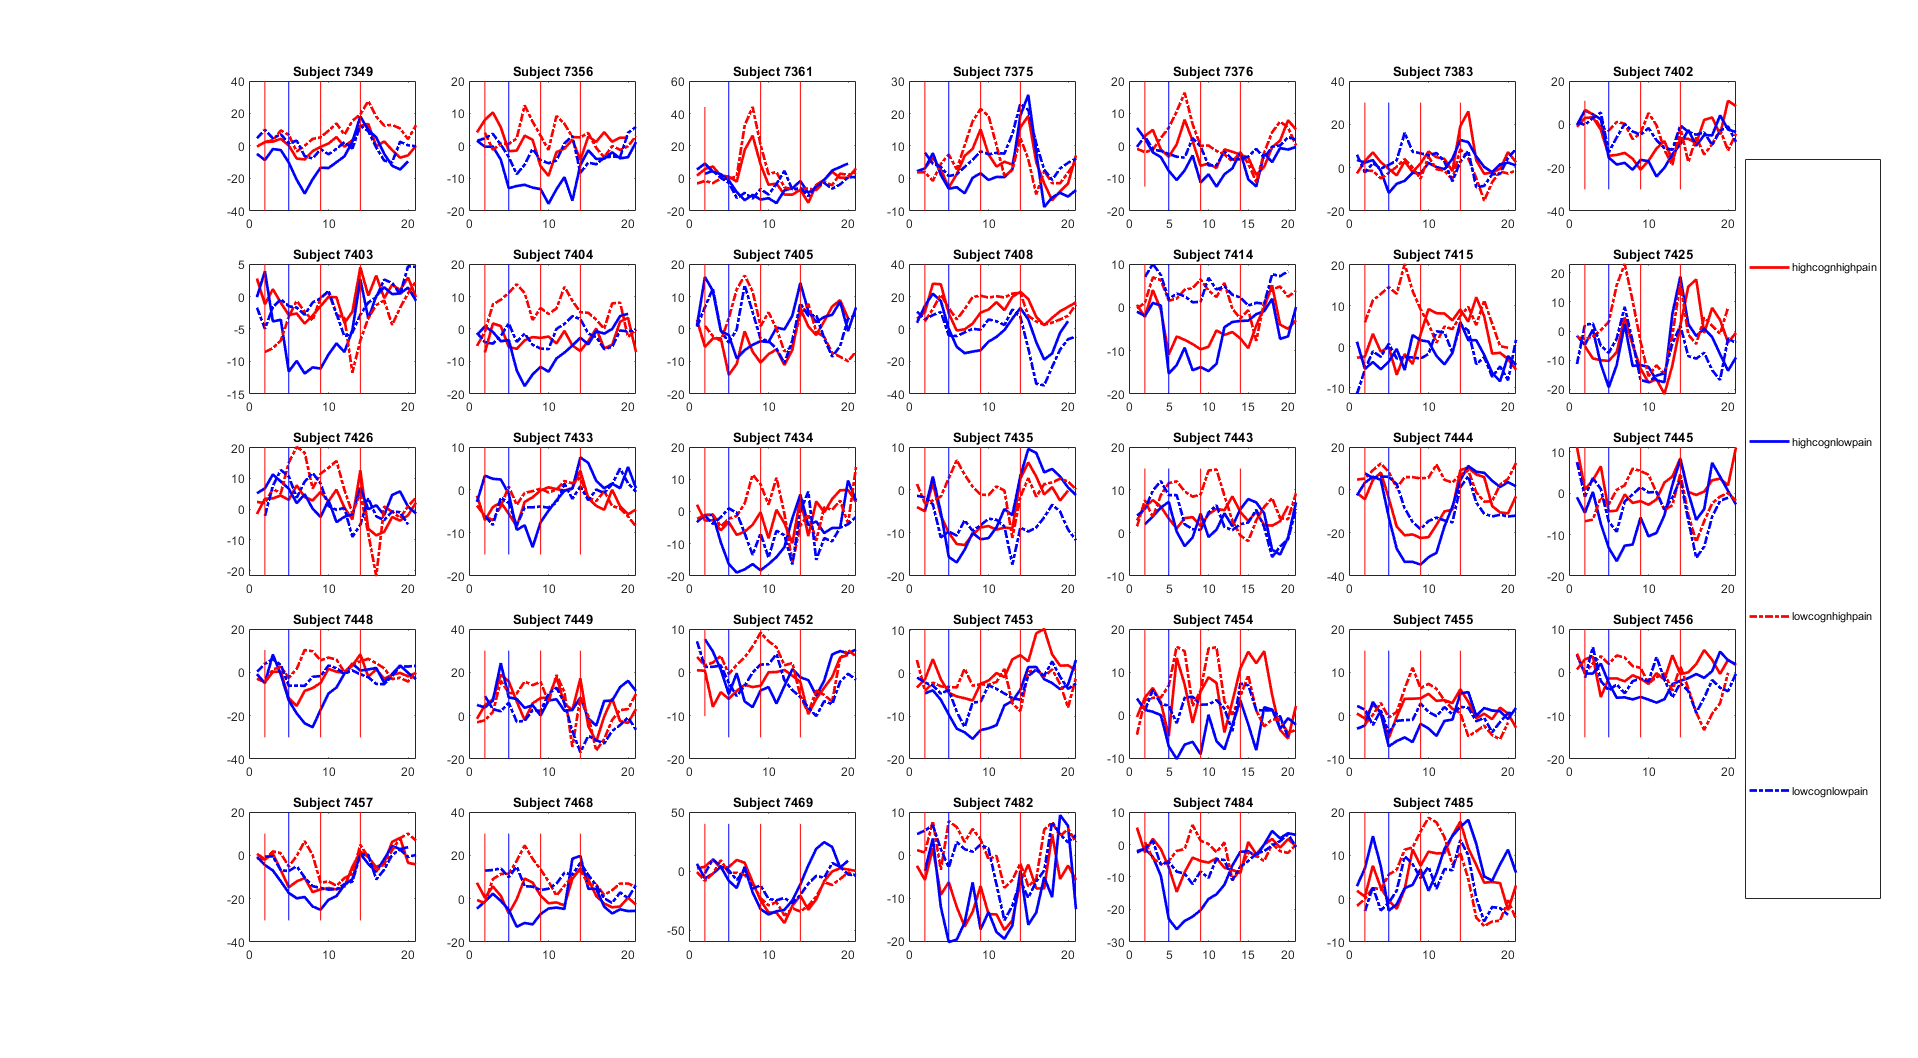

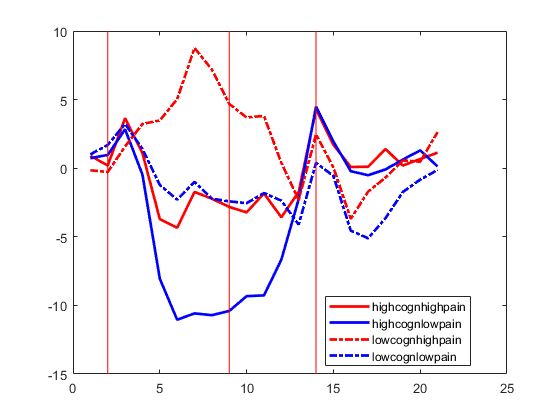

plotidx=0;
subplotsize=[8 4];
allsubjlayer={};
topcolumnnumber=200; %used this previously
layermeans = zeros(20, length(allsubj));

myroiname='S1';
hemisphere={'left' 'right'};
figuretype='raw'; %possible input: 'raw', 'tSNR',
focusofimgs='conditions'; %two possibliities: conditions; laminar
if strcmp(focusofimgs,'conditions') %the TS condition dependency(averaged across layers)
    figurelocationpath='C:\Users\lenov\Documents\layerfMRI\E_stats\images\tomanuscipt\firstdrafts\supplementary\rawboldtrialTS\';%This was the original one to save the rwaboldTSs
elseif strcmp(focusofimgs,'laminar') %the TS layer dependency (each condition separately)
    figurelocationpath='C:\Users\lenov\Documents\layerfMRI\E_stats\images\tomanuscipt\firstdrafts\supplementary\rawboldlayerdependentlTS\';% this is now the layer dependency
end
clustersize=200; %possible values: 200 - top 200 vertices, 0 - all vertices

for hemishperes=1:2
    figure('Position',[100, 100, 2400, 1200]);
    plotidx=0;
    for subj=allsubj
    %     roipath='C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\';
        rwdtmtrx=loadrawdatamatrix(subj,myroiname);
    %     columnartsfile=[roipath num2str(subj{:}) '\functionalmasks\interimdata_rwls_' myroiname 'raw.mat'];
    %     if exist(columnartsfile,"file")
    %         disp([num2str(subj{:}) ' subject columnar info r'])
    %         plotidx=plotidx+1;
    plotidx=plotidx+1;
    subplot(5,7,plotidx);
    if clustersize==200
            [columnwisestat,~,~]=BK_layer_sampling_pain_study_pipeline(num2cell(subj),'glmestimate',myroiname,'raw','no','maineff','200'); 
            %(subj,'glmestimate',region,'raw',visualize,typeofcon,selectedcolumns);
            %[S2_200vertices_wholecolumn,procesubjid,columndistr]=layervalues('S2','maineff+int','visualization','no');
    %         allsubjid(plotidx)=subj{:};
    %         allsubjlayer{plotidx}=layerwisestat;
    %         allsubjcoldistr{plotidx}=columndistribution;
    %         allsubjstat{plotidx}=stat;
            [top200Values, top200Indices] =maxk(columnwisestat(hemishperes).T(:,3),topcolumnnumber);
            
            % Filter the indices where the values are positive
            positiveIndices = top200Indices(top200Values > 0);
            % Check if any negative values were removed
            if length(positiveIndices) < topcolumnnumber
                warning('The top 200 values contained negative numbers. Only %d positive values are retained.', length(positiveIndices));
            end
            
            tmpdata=rwdtmtrx.interimdata_columns{1,2}{hemishperes,1};
            tmpdata=tmpdata(positiveIndices,:,:);

   elseif clustersize==0
            tmpdata=rwdtmtrx.interimdata_columns{1,2}{hemishperes,1};
    end
            myspm=loadtimingfile(subj);
            trialonset=findtrialonset(myspm);
            conditionnms=fieldnames(trialonset);

            %find the values corresponding for trial onset and focus on the
            %-1 to end of trial (which can be between 19 to 22 volumes)
            vertexmean=squeeze(mean(tmpdata,1));
            roimean=mean(vertexmean,1);
            sequencelength=length(roimean);
            for condition=1:length(conditionnms)
                mycond=conditionnms{condition};
                myvols=trialonset.(mycond);
                condts=[];
                for trial=1:length(myvols)
                    myvol=myvols(trial);
                    if (myvol+17)< sequencelength %this has to be put here as one subject has shorter data because of the failure of the measurement.
                        if myvol==1
                            mimi=roimean(myvol:(myvol+19));
                            mimi=[NaN,mimi];
                            restingperiod=roimean((myvol+13):(myvol+19));
                        else
                            %original, no baseline, no percent signal
                            %changecalculation
                            if myvol+19>sequencelength
                                mimi=roimean((myvol-1):end);
                                while length(mimi)~=21
                                    mimi=[mimi,NaN];
                                end
                            else
                                mimi=roimean((myvol-1):(myvol+19));
                            end
                            restingperiod=roimean((myvol-6):(myvol-1));
                        end
                        %this is the use of a baseline before adding
                        %together the conditions
%                         restingperiod=roimean((myvol-6):(myvol-1));
                        baslinedmimi=mimi-mean(restingperiod);
                        %this is calculation percent signal change
                        baslinedmimi_percchange=100*(mimi-mean(restingperiod))/std(restingperiod);
                        condts=[condts; baslinedmimi];
                    end
                end
                
                trialts.(mycond)=condts;

            end
%             noise_std = std(vertexmean, 0, 2);
%             layermean=mean(vertexmean,2);
%             tSNR=layermean./noise_std;
%             if strcmp(figuretype,'raw')
%                 imagedata=layermean;
%             elseif strcmp(figuretype,'tSNR')
%                 imagedata=tSNR;
%             end
            colourcode.pain_high_cogn_high_pain='-r';
            colourcode.pain_high_cogn_low_pain='-b';
            colourcode.pain_low_cogn_high_pain='-.r';
            colourcode.pain_low_cogn_low_pain='-.b';
            legend_entries = cell(length(conditionnms), 1);
            for condition=1:length(conditionnms)
                mycond=conditionnms{condition};
                mydata=mean(trialts.(mycond));
                line_handles(condition) = plot(mydata, colourcode.(mycond), 'LineWidth', 2,'DisplayName', mycond);
                
                hold on
                legend_entries{condition} = strrep(mycond(6:end), '_', '');
                grouplvldata(plotidx).(mycond)=mydata;
            end 
            vline(2,'r'); %this is the start of the pain stimulation, as 0sec is the anticipation (3sec is the forst start of the pain stimulation). The stimulation reaches the plateu with some delay(2sec?), also the canonical HRFis with 5.6 secdelay in the SPM.mat file, so it would mean, the max should be seen 3volume away. 
            vline(5,'b');
            vline(9,'r');
            vline(14,'r');
            legend(line_handles,legend_entries, 'Location', 'bestoutside', 'Position', [0.92, 0.15, 0.05, 0.7]);
            
            title([ 'Subject ' num2str(subj)]);  % add a title to each subplot
            hold off
%             layermeans(:, plotidx) = imagedata';
    %     else
    %         disp([num2str(subj{:}) ' subject has  no sampled cluster'])
    %     end
    
    end
    saveas(gcf, [figurelocationpath myroiname hemisphere{hemishperes} 'trialts_' num2str(clustersize) 'vertices_mean_eachsubj_baselined.jpg'], 'jpeg'); % _baselined OR _percsignchange
    
    
    figure;  % create a new figure to visualize the layermean matrix
    legend_entries = cell(length(conditionnms), 1);
    for condition=1:length(conditionnms)
        mycond=conditionnms{condition};
        mydata=mean(vertcat(grouplvldata.(mycond)),1,"omitnan");
        line_handles(condition) = plot(mydata, colourcode.(mycond), 'LineWidth', 2,'DisplayName', mycond);
%         errorbar(mydata, std(vertcat(grouplvldata.(mycond)),[],1),  colourcode.(mycond));
        hold on
        legend_entries{condition} = strrep(mycond(6:end), '_', '');
        
    end 
    vline(2,'r');
    vline(5,'b');
    vline(9,'r');
    vline(14,'r');
    legend(line_handles,legend_entries, 'Location', 'best');

%     plot(1:20, mean(layermeans, 2), '-r', 'LineWidth', 1);
%     hold on
%     errorbar(1:20, mean(layermeans, 2), std(layermeans, [], 2), 'k');
%     hold off
%     xlabel('laminar depth (WM to CSF)');
    %     ylabel(' raw BOLD signal');
%     title('Grand average across subjects');
    saveas(gcf, [figurelocationpath myroiname hemisphere{hemishperes} 'trialts_' num2str(clustersize) 'vertices_mean_subjavg_baselined.jpg'], 'jpeg');
end

This is tSNR for each condition separately. 

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7349\functionalmasks\interimdata_rwls_pInsraw.mat


Subject:7349The number of columns within the funcitonal mask: 1382
Subject:7349The percent/number of columns acitvating in each run(t>0) for cognition: 48%/658
Subject:7349The percent/number of columns acitvating in each run(t>0) for pain: 69%/950
Subject:7349The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 33%/459
-------------------------------------------------------------
Subject:7349The number of columns within the funcitonal mask: 1382
Subject:7349The percent/number of columns acitvating in each run(t>1) for cognition: 17%/230
Subject:7349The percent/number of columns acitvating in each run(t>1) for pain: 37%/515
Subject:7349The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 7%/99
-------------------------------------------------------------
Subject:7349The number of columns within the funcitonal mask: 1178
Subject:7349The percent/number of columns acitvating in each run(t>0) for cognition: 50%/590
Subject:7349The pe

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7356\functionalmasks\interimdata_rwls_pInsraw.mat


Subject:7356The number of columns within the funcitonal mask: 1429
Subject:7356The percent/number of columns acitvating in each run(t>0) for cognition: 59%/842
Subject:7356The percent/number of columns acitvating in each run(t>0) for pain: 42%/606
Subject:7356The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 25%/363
-------------------------------------------------------------
Subject:7356The number of columns within the funcitonal mask: 1429
Subject:7356The percent/number of columns acitvating in each run(t>1) for cognition: 24%/341
Subject:7356The percent/number of columns acitvating in each run(t>1) for pain: 14%/199
Subject:7356The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/63
-------------------------------------------------------------
Subject:7356The number of columns within the funcitonal mask: 1203
Subject:7356The percent/number of columns acitvating in each run(t>0) for cognition: 68%/823
Subject:7356The pe

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7361\functionalmasks\interimdata_rwls_pInsraw.mat


Subject:7361The number of columns within the funcitonal mask: 1793
Subject:7361The percent/number of columns acitvating in each run(t>0) for cognition: 59%/1065
Subject:7361The percent/number of columns acitvating in each run(t>0) for pain: 55%/991
Subject:7361The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 35%/630
-------------------------------------------------------------
Subject:7361The number of columns within the funcitonal mask: 1793
Subject:7361The percent/number of columns acitvating in each run(t>1) for cognition: 27%/489
Subject:7361The percent/number of columns acitvating in each run(t>1) for pain: 23%/407
Subject:7361The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 8%/136
-------------------------------------------------------------
Subject:7361The number of columns within the funcitonal mask: 1236
Subject:7361The percent/number of columns acitvating in each run(t>0) for cognition: 55%/684
Subject:7361The 

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7375\functionalmasks\interimdata_rwls_pInsraw.mat


Subject:7375The number of columns within the funcitonal mask: 1567
Subject:7375The percent/number of columns acitvating in each run(t>0) for cognition: 53%/835
Subject:7375The percent/number of columns acitvating in each run(t>0) for pain: 48%/759
Subject:7375The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 28%/433
-------------------------------------------------------------
Subject:7375The number of columns within the funcitonal mask: 1567
Subject:7375The percent/number of columns acitvating in each run(t>1) for cognition: 19%/305
Subject:7375The percent/number of columns acitvating in each run(t>1) for pain: 17%/260
Subject:7375The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/58
-------------------------------------------------------------
Subject:7375The number of columns within the funcitonal mask: 1276
Subject:7375The percent/number of columns acitvating in each run(t>0) for cognition: 51%/646
Subject:7375The pe

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7376\functionalmasks\interimdata_rwls_pInsraw.mat


Subject:7376The number of columns within the funcitonal mask: 1467
Subject:7376The percent/number of columns acitvating in each run(t>0) for cognition: 54%/787
Subject:7376The percent/number of columns acitvating in each run(t>0) for pain: 55%/801
Subject:7376The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 31%/454
-------------------------------------------------------------
Subject:7376The number of columns within the funcitonal mask: 1467
Subject:7376The percent/number of columns acitvating in each run(t>1) for cognition: 19%/277
Subject:7376The percent/number of columns acitvating in each run(t>1) for pain: 17%/255
Subject:7376The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/51
-------------------------------------------------------------
Subject:7376The number of columns within the funcitonal mask: 1369
Subject:7376The percent/number of columns acitvating in each run(t>0) for cognition: 48%/656
Subject:7376The pe

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7383\functionalmasks\interimdata_rwls_pInsraw.mat


Subject:7383The number of columns within the funcitonal mask: 1651
Subject:7383The percent/number of columns acitvating in each run(t>0) for cognition: 71%/1174
Subject:7383The percent/number of columns acitvating in each run(t>0) for pain: 52%/864
Subject:7383The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 38%/627
-------------------------------------------------------------
Subject:7383The number of columns within the funcitonal mask: 1651
Subject:7383The percent/number of columns acitvating in each run(t>1) for cognition: 42%/690
Subject:7383The percent/number of columns acitvating in each run(t>1) for pain: 17%/276
Subject:7383The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 7%/122
-------------------------------------------------------------
Subject:7383The number of columns within the funcitonal mask: 1138
Subject:7383The percent/number of columns acitvating in each run(t>0) for cognition: 58%/663
Subject:7383The 

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7402\functionalmasks\interimdata_rwls_pInsraw.mat


Subject:7402The number of columns within the funcitonal mask: 3216
Subject:7402The percent/number of columns acitvating in each run(t>0) for cognition: 67%/2158
Subject:7402The percent/number of columns acitvating in each run(t>0) for pain: 45%/1452
Subject:7402The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 30%/966
-------------------------------------------------------------
Subject:7402The number of columns within the funcitonal mask: 3216
Subject:7402The percent/number of columns acitvating in each run(t>1) for cognition: 31%/1000
Subject:7402The percent/number of columns acitvating in each run(t>1) for pain: 15%/487
Subject:7402The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 5%/164
-------------------------------------------------------------
Subject:7402The number of columns within the funcitonal mask: 2785
Subject:7402The percent/number of columns acitvating in each run(t>0) for cognition: 68%/1892
Subject:7402T

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7403\functionalmasks\interimdata_rwls_pInsraw.mat


Subject:7403The number of columns within the funcitonal mask: 1127
Subject:7403The percent/number of columns acitvating in each run(t>0) for cognition: 57%/645
Subject:7403The percent/number of columns acitvating in each run(t>0) for pain: 49%/552
Subject:7403The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 27%/304
-------------------------------------------------------------
Subject:7403The number of columns within the funcitonal mask: 1127
Subject:7403The percent/number of columns acitvating in each run(t>1) for cognition: 22%/253
Subject:7403The percent/number of columns acitvating in each run(t>1) for pain: 17%/190
Subject:7403The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/43
-------------------------------------------------------------
Subject:7403The number of columns within the funcitonal mask: 1163
Subject:7403The percent/number of columns acitvating in each run(t>0) for cognition: 63%/729
Subject:7403The pe

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7404\functionalmasks\interimdata_rwls_pInsraw.mat


Subject:7404The number of columns within the funcitonal mask: 1474
Subject:7404The percent/number of columns acitvating in each run(t>0) for cognition: 59%/872
Subject:7404The percent/number of columns acitvating in each run(t>0) for pain: 54%/799
Subject:7404The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 32%/476
-------------------------------------------------------------
Subject:7404The number of columns within the funcitonal mask: 1474
Subject:7404The percent/number of columns acitvating in each run(t>1) for cognition: 24%/358
Subject:7404The percent/number of columns acitvating in each run(t>1) for pain: 19%/275
Subject:7404The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 6%/83
-------------------------------------------------------------
Subject:7404The number of columns within the funcitonal mask: 1231
Subject:7404The percent/number of columns acitvating in each run(t>0) for cognition: 55%/675
Subject:7404The pe

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7405\functionalmasks\interimdata_rwls_pInsraw.mat


Subject:7405The number of columns within the funcitonal mask: 1082
Subject:7405The percent/number of columns acitvating in each run(t>0) for cognition: 73%/785
Subject:7405The percent/number of columns acitvating in each run(t>0) for pain: 53%/569
Subject:7405The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 39%/417
-------------------------------------------------------------
Subject:7405The number of columns within the funcitonal mask: 1082
Subject:7405The percent/number of columns acitvating in each run(t>1) for cognition: 40%/435
Subject:7405The percent/number of columns acitvating in each run(t>1) for pain: 18%/197
Subject:7405The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 9%/102
-------------------------------------------------------------
Subject:7405The number of columns within the funcitonal mask: 1181
Subject:7405The percent/number of columns acitvating in each run(t>0) for cognition: 78%/917
Subject:7405The p

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7408\functionalmasks\interimdata_rwls_pInsraw.mat


Subject:7408The number of columns within the funcitonal mask: 1414
Subject:7408The percent/number of columns acitvating in each run(t>0) for cognition: 66%/940
Subject:7408The percent/number of columns acitvating in each run(t>0) for pain: 55%/780
Subject:7408The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 37%/529
-------------------------------------------------------------
Subject:7408The number of columns within the funcitonal mask: 1414
Subject:7408The percent/number of columns acitvating in each run(t>1) for cognition: 33%/472
Subject:7408The percent/number of columns acitvating in each run(t>1) for pain: 21%/290
Subject:7408The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 8%/118
-------------------------------------------------------------
Subject:7408The number of columns within the funcitonal mask: 1277
Subject:7408The percent/number of columns acitvating in each run(t>0) for cognition: 61%/773
Subject:7408The p

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7414\functionalmasks\interimdata_rwls_pInsraw.mat


Subject:7414The number of columns within the funcitonal mask: 1272
Subject:7414The percent/number of columns acitvating in each run(t>0) for cognition: 59%/756
Subject:7414The percent/number of columns acitvating in each run(t>0) for pain: 55%/704
Subject:7414The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 31%/393
-------------------------------------------------------------
Subject:7414The number of columns within the funcitonal mask: 1272
Subject:7414The percent/number of columns acitvating in each run(t>1) for cognition: 23%/289
Subject:7414The percent/number of columns acitvating in each run(t>1) for pain: 20%/257
Subject:7414The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/53
-------------------------------------------------------------
Subject:7414The number of columns within the funcitonal mask: 1268
Subject:7414The percent/number of columns acitvating in each run(t>0) for cognition: 55%/698
Subject:7414The pe

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7415\functionalmasks\interimdata_rwls_pInsraw.mat


Subject:7415The number of columns within the funcitonal mask: 1196
Subject:7415The percent/number of columns acitvating in each run(t>0) for cognition: 39%/462
Subject:7415The percent/number of columns acitvating in each run(t>0) for pain: 41%/496
Subject:7415The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 18%/219
-------------------------------------------------------------
Subject:7415The number of columns within the funcitonal mask: 1196
Subject:7415The percent/number of columns acitvating in each run(t>1) for cognition: 13%/154
Subject:7415The percent/number of columns acitvating in each run(t>1) for pain: 14%/173
Subject:7415The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 2%/28
-------------------------------------------------------------
Subject:7415The number of columns within the funcitonal mask: 1232
Subject:7415The percent/number of columns acitvating in each run(t>0) for cognition: 45%/557
Subject:7415The pe

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7425\functionalmasks\interimdata_rwls_pInsraw.mat


Subject:7425The number of columns within the funcitonal mask: 1450
Subject:7425The percent/number of columns acitvating in each run(t>0) for cognition: 49%/712
Subject:7425The percent/number of columns acitvating in each run(t>0) for pain: 47%/676
Subject:7425The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 26%/378
-------------------------------------------------------------
Subject:7425The number of columns within the funcitonal mask: 1450
Subject:7425The percent/number of columns acitvating in each run(t>1) for cognition: 20%/293
Subject:7425The percent/number of columns acitvating in each run(t>1) for pain: 18%/266
Subject:7425The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 5%/73
-------------------------------------------------------------
Subject:7425The number of columns within the funcitonal mask: 1389
Subject:7425The percent/number of columns acitvating in each run(t>0) for cognition: 42%/590
Subject:7425The pe

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7426\functionalmasks\interimdata_rwls_pInsraw.mat


Subject:7426The number of columns within the funcitonal mask: 1218
Subject:7426The percent/number of columns acitvating in each run(t>0) for cognition: 62%/758
Subject:7426The percent/number of columns acitvating in each run(t>0) for pain: 55%/672
Subject:7426The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 35%/427
-------------------------------------------------------------
Subject:7426The number of columns within the funcitonal mask: 1218
Subject:7426The percent/number of columns acitvating in each run(t>1) for cognition: 29%/355
Subject:7426The percent/number of columns acitvating in each run(t>1) for pain: 23%/278
Subject:7426The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 7%/81
-------------------------------------------------------------
Subject:7426The number of columns within the funcitonal mask: 1280
Subject:7426The percent/number of columns acitvating in each run(t>0) for cognition: 58%/745
Subject:7426The pe

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7433\functionalmasks\interimdata_rwls_pInsraw.mat


Subject:7433The number of columns within the funcitonal mask: 1970
Subject:7433The percent/number of columns acitvating in each run(t>0) for cognition: 49%/971
Subject:7433The percent/number of columns acitvating in each run(t>0) for pain: 54%/1070
Subject:7433The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 26%/511
-------------------------------------------------------------
Subject:7433The number of columns within the funcitonal mask: 1970
Subject:7433The percent/number of columns acitvating in each run(t>1) for cognition: 16%/309
Subject:7433The percent/number of columns acitvating in each run(t>1) for pain: 19%/370
Subject:7433The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/53
-------------------------------------------------------------
Subject:7433The number of columns within the funcitonal mask: 1589
Subject:7433The percent/number of columns acitvating in each run(t>0) for cognition: 47%/746
Subject:7433The p

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7434\functionalmasks\interimdata_rwls_pInsraw.mat


Subject:7434The number of columns within the funcitonal mask: 1471
Subject:7434The percent/number of columns acitvating in each run(t>0) for cognition: 56%/827
Subject:7434The percent/number of columns acitvating in each run(t>0) for pain: 60%/880
Subject:7434The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 34%/493
-------------------------------------------------------------
Subject:7434The number of columns within the funcitonal mask: 1471
Subject:7434The percent/number of columns acitvating in each run(t>1) for cognition: 21%/312
Subject:7434The percent/number of columns acitvating in each run(t>1) for pain: 25%/361
Subject:7434The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 6%/88
-------------------------------------------------------------
Subject:7434The number of columns within the funcitonal mask: 1301
Subject:7434The percent/number of columns acitvating in each run(t>0) for cognition: 58%/758
Subject:7434The pe

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7435\functionalmasks\interimdata_rwls_pInsraw.mat


Subject:7435The number of columns within the funcitonal mask: 1210
Subject:7435The percent/number of columns acitvating in each run(t>0) for cognition: 59%/715
Subject:7435The percent/number of columns acitvating in each run(t>0) for pain: 47%/563
Subject:7435The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 28%/333
-------------------------------------------------------------
Subject:7435The number of columns within the funcitonal mask: 1210
Subject:7435The percent/number of columns acitvating in each run(t>1) for cognition: 31%/378
Subject:7435The percent/number of columns acitvating in each run(t>1) for pain: 17%/208
Subject:7435The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 5%/62
-------------------------------------------------------------
Subject:7435The number of columns within the funcitonal mask: 1122
Subject:7435The percent/number of columns acitvating in each run(t>0) for cognition: 56%/626
Subject:7435The pe

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7443\functionalmasks\interimdata_rwls_pInsraw.mat


Subject:7443The number of columns within the funcitonal mask: 2234
Subject:7443The percent/number of columns acitvating in each run(t>0) for cognition: 54%/1215
Subject:7443The percent/number of columns acitvating in each run(t>0) for pain: 50%/1112
Subject:7443The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 27%/600
-------------------------------------------------------------
Subject:7443The number of columns within the funcitonal mask: 2234
Subject:7443The percent/number of columns acitvating in each run(t>1) for cognition: 19%/416
Subject:7443The percent/number of columns acitvating in each run(t>1) for pain: 18%/399
Subject:7443The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/62
-------------------------------------------------------------
Subject:7443The number of columns within the funcitonal mask: 1557
Subject:7443The percent/number of columns acitvating in each run(t>0) for cognition: 53%/822
Subject:7443The 

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7444\functionalmasks\interimdata_rwls_pInsraw.mat


Subject:7444The number of columns within the funcitonal mask: 1748
Subject:7444The percent/number of columns acitvating in each run(t>0) for cognition: 64%/1121
Subject:7444The percent/number of columns acitvating in each run(t>0) for pain: 58%/1009
Subject:7444The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 36%/636
-------------------------------------------------------------
Subject:7444The number of columns within the funcitonal mask: 1748
Subject:7444The percent/number of columns acitvating in each run(t>1) for cognition: 30%/527
Subject:7444The percent/number of columns acitvating in each run(t>1) for pain: 26%/446
Subject:7444The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 8%/140
-------------------------------------------------------------
Subject:7444The number of columns within the funcitonal mask: 1737
Subject:7444The percent/number of columns acitvating in each run(t>0) for cognition: 75%/1298
Subject:7444Th

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7445\functionalmasks\interimdata_rwls_pInsraw.mat


Subject:7445The number of columns within the funcitonal mask: 1332
Subject:7445The percent/number of columns acitvating in each run(t>0) for cognition: 56%/751
Subject:7445The percent/number of columns acitvating in each run(t>0) for pain: 54%/720
Subject:7445The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 29%/384
-------------------------------------------------------------
Subject:7445The number of columns within the funcitonal mask: 1332
Subject:7445The percent/number of columns acitvating in each run(t>1) for cognition: 24%/319
Subject:7445The percent/number of columns acitvating in each run(t>1) for pain: 20%/261
Subject:7445The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 5%/62
-------------------------------------------------------------
Subject:7445The number of columns within the funcitonal mask: 1522
Subject:7445The percent/number of columns acitvating in each run(t>0) for cognition: 55%/835
Subject:7445The pe

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7448\functionalmasks\interimdata_rwls_pInsraw.mat


Subject:7448The number of columns within the funcitonal mask: 1347
Subject:7448The percent/number of columns acitvating in each run(t>0) for cognition: 71%/952
Subject:7448The percent/number of columns acitvating in each run(t>0) for pain: 62%/834
Subject:7448The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 45%/608
-------------------------------------------------------------
Subject:7448The number of columns within the funcitonal mask: 1347
Subject:7448The percent/number of columns acitvating in each run(t>1) for cognition: 34%/460
Subject:7448The percent/number of columns acitvating in each run(t>1) for pain: 27%/358
Subject:7448The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 10%/131
-------------------------------------------------------------
Subject:7448The number of columns within the funcitonal mask: 1160
Subject:7448The percent/number of columns acitvating in each run(t>0) for cognition: 70%/814
Subject:7448The 

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7449\functionalmasks\interimdata_rwls_pInsraw.mat


Subject:7449The number of columns within the funcitonal mask: 1603
Subject:7449The percent/number of columns acitvating in each run(t>0) for cognition: 50%/798
Subject:7449The percent/number of columns acitvating in each run(t>0) for pain: 44%/701
Subject:7449The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 21%/340
-------------------------------------------------------------
Subject:7449The number of columns within the funcitonal mask: 1603
Subject:7449The percent/number of columns acitvating in each run(t>1) for cognition: 18%/293
Subject:7449The percent/number of columns acitvating in each run(t>1) for pain: 15%/236
Subject:7449The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/46
-------------------------------------------------------------
Subject:7449The number of columns within the funcitonal mask: 1579
Subject:7449The percent/number of columns acitvating in each run(t>0) for cognition: 54%/848
Subject:7449The pe

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7452\functionalmasks\interimdata_rwls_pInsraw.mat


Subject:7452The number of columns within the funcitonal mask: 1266
Subject:7452The percent/number of columns acitvating in each run(t>0) for cognition: 51%/641
Subject:7452The percent/number of columns acitvating in each run(t>0) for pain: 54%/688
Subject:7452The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 28%/354
-------------------------------------------------------------
Subject:7452The number of columns within the funcitonal mask: 1266
Subject:7452The percent/number of columns acitvating in each run(t>1) for cognition: 20%/247
Subject:7452The percent/number of columns acitvating in each run(t>1) for pain: 20%/253
Subject:7452The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 5%/62
-------------------------------------------------------------
Subject:7452The number of columns within the funcitonal mask: 1107
Subject:7452The percent/number of columns acitvating in each run(t>0) for cognition: 54%/597
Subject:7452The pe

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7453\functionalmasks\interimdata_rwls_pInsraw.mat


Subject:7453The number of columns within the funcitonal mask: 1318
Subject:7453The percent/number of columns acitvating in each run(t>0) for cognition: 55%/726
Subject:7453The percent/number of columns acitvating in each run(t>0) for pain: 51%/669
Subject:7453The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 28%/374
-------------------------------------------------------------
Subject:7453The number of columns within the funcitonal mask: 1318
Subject:7453The percent/number of columns acitvating in each run(t>1) for cognition: 20%/270
Subject:7453The percent/number of columns acitvating in each run(t>1) for pain: 20%/262
Subject:7453The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/47
-------------------------------------------------------------
Subject:7453The number of columns within the funcitonal mask: 1404
Subject:7453The percent/number of columns acitvating in each run(t>0) for cognition: 52%/734
Subject:7453The pe

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7454\functionalmasks\interimdata_rwls_pInsraw.mat


Subject:7454The number of columns within the funcitonal mask: 1299
Subject:7454The percent/number of columns acitvating in each run(t>0) for cognition: 68%/882
Subject:7454The percent/number of columns acitvating in each run(t>0) for pain: 56%/725
Subject:7454The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 37%/482
-------------------------------------------------------------
Subject:7454The number of columns within the funcitonal mask: 1299
Subject:7454The percent/number of columns acitvating in each run(t>1) for cognition: 30%/390
Subject:7454The percent/number of columns acitvating in each run(t>1) for pain: 22%/285
Subject:7454The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 6%/78
-------------------------------------------------------------
Subject:7454The number of columns within the funcitonal mask: 1150
Subject:7454The percent/number of columns acitvating in each run(t>0) for cognition: 59%/680
Subject:7454The pe

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7455\functionalmasks\interimdata_rwls_pInsraw.mat


Subject:7455The number of columns within the funcitonal mask: 1245
Subject:7455The percent/number of columns acitvating in each run(t>0) for cognition: 55%/683
Subject:7455The percent/number of columns acitvating in each run(t>0) for pain: 60%/744
Subject:7455The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 35%/440
-------------------------------------------------------------
Subject:7455The number of columns within the funcitonal mask: 1245
Subject:7455The percent/number of columns acitvating in each run(t>1) for cognition: 20%/246
Subject:7455The percent/number of columns acitvating in each run(t>1) for pain: 24%/305
Subject:7455The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 6%/72
-------------------------------------------------------------
Subject:7455The number of columns within the funcitonal mask: 1014
Subject:7455The percent/number of columns acitvating in each run(t>0) for cognition: 49%/497
Subject:7455The pe

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7456\functionalmasks\interimdata_rwls_pInsraw.mat


Subject:7456The number of columns within the funcitonal mask: 1241
Subject:7456The percent/number of columns acitvating in each run(t>0) for cognition: 53%/661
Subject:7456The percent/number of columns acitvating in each run(t>0) for pain: 51%/629
Subject:7456The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 28%/349
-------------------------------------------------------------
Subject:7456The number of columns within the funcitonal mask: 1241
Subject:7456The percent/number of columns acitvating in each run(t>1) for cognition: 21%/263
Subject:7456The percent/number of columns acitvating in each run(t>1) for pain: 19%/234
Subject:7456The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 5%/56
-------------------------------------------------------------
Subject:7456The number of columns within the funcitonal mask: 1157
Subject:7456The percent/number of columns acitvating in each run(t>0) for cognition: 49%/571
Subject:7456The pe

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7457\functionalmasks\interimdata_rwls_pInsraw.mat


Subject:7457The number of columns within the funcitonal mask: 1463
Subject:7457The percent/number of columns acitvating in each run(t>0) for cognition: 55%/808
Subject:7457The percent/number of columns acitvating in each run(t>0) for pain: 52%/762
Subject:7457The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 27%/401
-------------------------------------------------------------
Subject:7457The number of columns within the funcitonal mask: 1463
Subject:7457The percent/number of columns acitvating in each run(t>1) for cognition: 20%/297
Subject:7457The percent/number of columns acitvating in each run(t>1) for pain: 20%/297
Subject:7457The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/56
-------------------------------------------------------------
Subject:7457The number of columns within the funcitonal mask: 1322
Subject:7457The percent/number of columns acitvating in each run(t>0) for cognition: 58%/770
Subject:7457The pe

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7468\functionalmasks\interimdata_rwls_pInsraw.mat


Subject:7468The number of columns within the funcitonal mask: 1160
Subject:7468The percent/number of columns acitvating in each run(t>0) for cognition: 56%/654
Subject:7468The percent/number of columns acitvating in each run(t>0) for pain: 53%/612
Subject:7468The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 29%/338
-------------------------------------------------------------
Subject:7468The number of columns within the funcitonal mask: 1160
Subject:7468The percent/number of columns acitvating in each run(t>1) for cognition: 23%/265
Subject:7468The percent/number of columns acitvating in each run(t>1) for pain: 20%/227
Subject:7468The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 5%/53
-------------------------------------------------------------
Subject:7468The number of columns within the funcitonal mask: 1103
Subject:7468The percent/number of columns acitvating in each run(t>0) for cognition: 52%/574
Subject:7468The pe

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7469\functionalmasks\interimdata_rwls_pInsraw.mat


Subject:7469The number of columns within the funcitonal mask: 1544
Subject:7469The percent/number of columns acitvating in each run(t>0) for cognition: 67%/1027
Subject:7469The percent/number of columns acitvating in each run(t>0) for pain: 73%/1131
Subject:7469The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 50%/765
-------------------------------------------------------------
Subject:7469The number of columns within the funcitonal mask: 1544
Subject:7469The percent/number of columns acitvating in each run(t>1) for cognition: 28%/435
Subject:7469The percent/number of columns acitvating in each run(t>1) for pain: 43%/658
Subject:7469The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 13%/207
-------------------------------------------------------------
Subject:7469The number of columns within the funcitonal mask: 1268
Subject:7469The percent/number of columns acitvating in each run(t>0) for cognition: 60%/763
Subject:7469Th

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7482\functionalmasks\interimdata_rwls_pInsraw.mat


Subject:7482The number of columns within the funcitonal mask: 1440
Subject:7482The percent/number of columns acitvating in each run(t>0) for cognition: 62%/892
Subject:7482The percent/number of columns acitvating in each run(t>0) for pain: 43%/612
Subject:7482The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 26%/379
-------------------------------------------------------------
Subject:7482The number of columns within the funcitonal mask: 1440
Subject:7482The percent/number of columns acitvating in each run(t>1) for cognition: 29%/419
Subject:7482The percent/number of columns acitvating in each run(t>1) for pain: 14%/199
Subject:7482The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/57
-------------------------------------------------------------
Subject:7482The number of columns within the funcitonal mask: 1299
Subject:7482The percent/number of columns acitvating in each run(t>0) for cognition: 61%/798
Subject:7482The pe

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7484\functionalmasks\interimdata_rwls_pInsraw.mat


Subject:7484The number of columns within the funcitonal mask: 1145
Subject:7484The percent/number of columns acitvating in each run(t>0) for cognition: 57%/650
Subject:7484The percent/number of columns acitvating in each run(t>0) for pain: 62%/715
Subject:7484The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 36%/412
-------------------------------------------------------------
Subject:7484The number of columns within the funcitonal mask: 1145
Subject:7484The percent/number of columns acitvating in each run(t>1) for cognition: 26%/301
Subject:7484The percent/number of columns acitvating in each run(t>1) for pain: 28%/321
Subject:7484The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 9%/99
-------------------------------------------------------------
Subject:7484The number of columns within the funcitonal mask: 1161
Subject:7484The percent/number of columns acitvating in each run(t>0) for cognition: 49%/571
Subject:7484The pe

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7485\functionalmasks\interimdata_rwls_pInsraw.mat


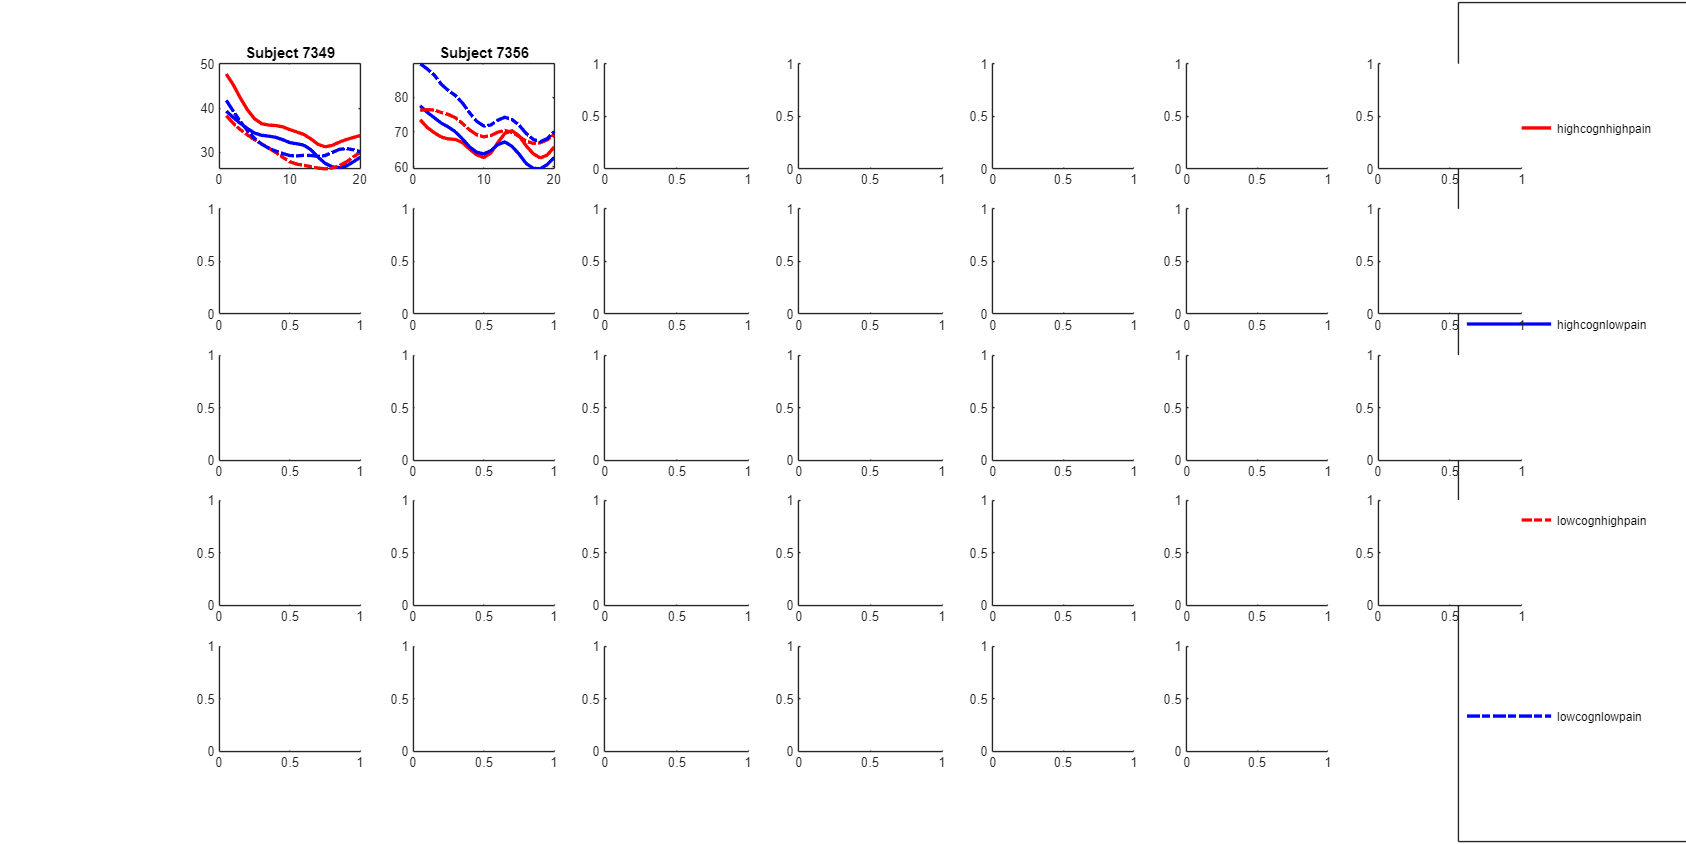

Subject:7485The number of columns within the funcitonal mask: 1251
Subject:7485The percent/number of columns acitvating in each run(t>0) for cognition: 63%/786
Subject:7485The percent/number of columns acitvating in each run(t>0) for pain: 52%/654
Subject:7485The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 32%/404
-------------------------------------------------------------
Subject:7485The number of columns within the funcitonal mask: 1251
Subject:7485The percent/number of columns acitvating in each run(t>1) for cognition: 29%/359
Subject:7485The percent/number of columns acitvating in each run(t>1) for pain: 19%/241
Subject:7485The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 6%/69
-------------------------------------------------------------
Subject:7485The number of columns within the funcitonal mask: 1262
Subject:7485The percent/number of columns acitvating in each run(t>0) for cognition: 70%/886
Subject:7485The pe

plotidx=0;
subplotsize=[8 4];
allsubjlayer={};
topcolumnnumber=200; %used this previously
layermeans = zeros(20, length(allsubj));

myroiname='pIns';
hemisphere={'left' 'right'};
% figuretype='raw'; %possible input: 'raw', 'tSNR', 
figurelocationpath='C:\Users\lenov\Documents\layerfMRI\E_stats\images\tomanuscipt\firstdrafts\supplementary\tSNRBOLD_percondition\';
clustersize=200; %possible values: 200 - top 200 vertices, 0 - all vertices


% figure('Position',[100, 100, 2400, 1200]);
plotidx=0;
for subj=allsubj

    rwdtmtrx=loadrawdatamatrix(subj,myroiname);
    plotidx=plotidx+1;
    subplot(5,7,plotidx);
    if clustersize==200
            [columnwisestat,~,~]=BK_layer_sampling_pain_study_pipeline(num2cell(subj),'glmestimate',myroiname,'raw','no','maineff',string(clustersize));
            for hemishperes=1:2
                [top200Values, top200Indices] =maxk(columnwisestat(hemishperes).T(:,3),topcolumnnumber);                    

                positiveIndices = top200Indices(top200Values > 0);
                
                tmpdata=rwdtmtrx.interimdata_columns{1,2}{hemishperes,1};
                mytmpdata{plotidx,hemishperes}=tmpdata(positiveIndices,:,:);
                
            end
    elseif clustersize==0
            tmpdata{plotidx,hemispheres}=rwdtmtrx.interimdata_columns{1,2}{hemishperes,1};
    end
    mytmpdata{plotidx,3}=subj;
end

%This is a cell to calculate the tSNR as below, but save the indiviudal ROI
%level estimate in csv, so a nicer visualization can be provded in R.
Tall=[];
for hemishperes=1:2
    for subj=allsubj

        myspm=loadtimingfile(subj);
        trialonset=findtrialonset(myspm);
        conditionnms=fieldnames(trialonset);
        vertexmean=squeeze(mean(mytmpdata{plotidx,hemishperes},1));
        roimean=mean(vertexmean,1);
            for condition=1:length(conditionnms)
                mycond=conditionnms{condition};
                myvols=trialonset.(mycond);
                condts=[];
                for trial=1:length(myvols)
                    myvol=myvols(trial);
                    if (myvol+17)<length(roimean) %this has to be put here as one subject has shorter data because of the failure of the measurement.
%                         if myvol==1
%                             mimi=vertexmean(:,myvol:(myvol+17));
%                             mimi=[repmat(NaN,20,1),mimi]
%                         else
%                             mimi=vertexmean(:,(myvol-1):(myvol+17));
%                         end
                        mimi=vertexmean(:,(myvol):(myvol+17));
                        condts=[condts, mimi];
                    end
                end
                trialts.(mycond)=condts;
                noise_std = std(condts, 0, 2);
                layermean=mean(condts,2);
                trialtSNR.(mycond)=layermean./noise_std;

            end
            trialtSNR.subjid=subj;
            trialtSNR.hemisphere=hemishperes;
            S=trialtSNR;
          n = numel(S.pain_high_cogn_high_pain);
        % Sanity check: all vector fields same length
        assert(numel(S.pain_high_cogn_low_pain)  == n && ...
               numel(S.pain_low_cogn_high_pain)  == n && ...
               numel(S.pain_low_cogn_low_pain)   == n, 'Vector field lengths must match');
        
        T = table();
        T.subjid      = repmat(S.subjid,     n, 1);
        T.hemisphere  = repmat(S.hemisphere, n, 1);
        T.layer       = (1:n)';  % optional index within struct
        T.pain_high_cogn_high_pain = S.pain_high_cogn_high_pain(:);
        T.pain_high_cogn_low_pain  = S.pain_high_cogn_low_pain(:);
        T.pain_low_cogn_high_pain  = S.pain_low_cogn_high_pain(:);
        T.pain_low_cogn_low_pain   = S.pain_low_cogn_low_pain(:);
        
        % Optional: identify which loop/struct this came from
%         T.struct_idx = repmat(k, n, 1);
        
        Tall = [Tall; T];  % concatenate

    end  
            

end

pathfortsnrdata='C:\Users\lenov\Documents\layerfMRI\E_stats\images\tomanuscipt\firstdrafts\supplementary\tSNRBOLD_percondition\tSNRdatafornicervisualization\';
writetable(Tall, [pathfortsnrdata 'pIns_trialtSNR.csv']);

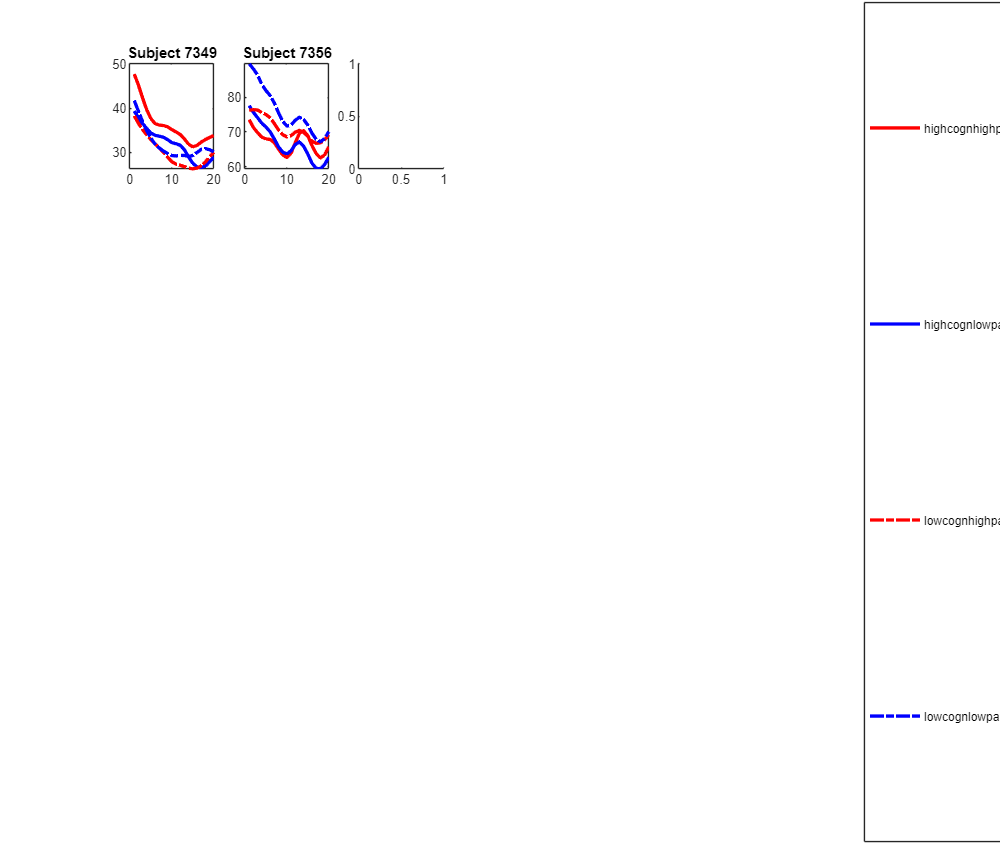

Index in position 1 exceeds array bounds. Index must not exceed 2.



for hemishperes=1:2
    figure('Position',[100, 100, 2400, 1200]);
    plotidx=0;
    for subj=allsubj

    
        plotidx=plotidx+1;
        subplot(5,7,plotidx);
    
        myspm=loadtimingfile(subj);
        trialonset=findtrialonset(myspm);
        conditionnms=fieldnames(trialonset);



            vertexmean=squeeze(mean(mytmpdata{plotidx,hemishperes},1));
            roimean=mean(vertexmean,1);
            for condition=1:length(conditionnms)
                mycond=conditionnms{condition};
                myvols=trialonset.(mycond);
                condts=[];
                for trial=1:length(myvols)
                    myvol=myvols(trial);
                    if (myvol+17)<length(roimean) %this has to be put here as one subject has shorter data because of the failure of the measurement.
%                         if myvol==1
%                             mimi=vertexmean(:,myvol:(myvol+17));
%                             mimi=[repmat(NaN,20,1),mimi]
%                         else
%                             mimi=vertexmean(:,(myvol-1):(myvol+17));
%                         end
                        mimi=vertexmean(:,(myvol):(myvol+17));
                        condts=[condts, mimi];
                    end
                end
                trialts.(mycond)=condts;
                noise_std = std(condts, 0, 2);
                layermean=mean(condts,2);
                trialtSNR.(mycond)=layermean./noise_std;

            end
%             noise_std = std(vertexmean, 0, 2);
%             layermean=mean(vertexmean,2);
%             tSNR=layermean./noise_std;
%             if strcmp(figuretype,'raw')
%                 imagedata=layermean;
%             elseif strcmp(figuretype,'tSNR')
%                 imagedata=tSNR;
%             end
            colourcode.pain_high_cogn_high_pain='-r';
            colourcode.pain_high_cogn_low_pain='-b';
            colourcode.pain_low_cogn_high_pain='-.r';
            colourcode.pain_low_cogn_low_pain='-.b';
            legend_entries = cell(length(conditionnms), 1);
            for condition=1:length(conditionnms)
                mycond=conditionnms{condition};
%                 mydata=mean(trialts.(mycond),2);
                mydata=mean(trialtSNR.(mycond),2);
                line_handles(condition) = plot(mydata, colourcode.(mycond), 'LineWidth', 2,'DisplayName', mycond);
                
                hold on
                legend_entries{condition} = strrep(mycond(6:end), '_', '');
                grouplvldata(plotidx).(mycond)=mydata;
            end 
%             vline(2,'r');
%             vline(9,'r');
%             vline(14,'r');
            legend(line_handles,legend_entries, 'Location', 'bestoutside', 'Position', [0.92, 0.15, 0.05, 0.7]);
            title([ 'Subject ' num2str(subj)]);  % add a title to each subplot
            hold off
    end  
            
            
%             layermeans(:, plotidx) = imagedata';
    %     else
    %         disp([num2str(subj{:}) ' subject has  no sampled cluster'])
    %     end
    
    
    saveas(gcf, [figurelocationpath myroiname hemisphere{hemishperes} 'trialts_' num2str(clustersize) 'vertices_mean_eachsubj.jpg'], 'jpeg');
    
    
    figure;  % create a new figure to visualize the layermean matrix
    legend_entries = cell(length(conditionnms), 1);
    for condition=1:length(conditionnms)
        mycond=conditionnms{condition};
        mydata=mean(horzcat(grouplvldata.(mycond)),2,"omitnan");
        line_handles(condition) = plot(mydata, colourcode.(mycond), 'LineWidth', 2,'DisplayName', mycond);
        errorbar(mydata, std(horzcat(grouplvldata.(mycond)),[],2),  colourcode.(mycond));
        hold on
        legend_entries{condition} = strrep(mycond(6:end), '_', '');
        
    end 
%     vline(2,'r');
%     vline(9,'r');
%     vline(14,'r');
%     legend(line_handles,legend_entries);

%     plot(1:20, mean(layermeans, 2), '-r', 'LineWidth', 1);
%     hold on
%     errorbar(1:20, mean(layermeans, 2), std(layermeans, [], 2), 'k');
%     hold off
%     xlabel('laminar depth (WM to CSF)');
%     ylabel(' raw BOLD signal');
%     title('Grand average across subjects');
    saveas(gcf, [figurelocationpath myroiname hemisphere{hemishperes} 'trialts_' num2str(clustersize) 'vertices_mean_subjavg.jpg'], 'jpeg');
end

## Calculate layer dependent BOLD response as in the Lawrence paper. See whetehr the BOLD response is biased towards the superficial layers.

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7349\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7349The number of columns within the funcitonal mask: 769
Subject:7349The percent/number of columns acitvating in each run(t>0) for cognition: 27%/206
Subject:7349The percent/number of columns acitvating in each run(t>0) for pain: 64%/496
Subject:7349The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 19%/143
-------------------------------------------------------------
Subject:7349The number of columns within the funcitonal mask: 769
Subject:7349The percent/number of columns acitvating in each run(t>1) for cognition: 7%/50
Subject:7349The percent/number of columns acitvating in each run(t>1) for pain: 27%/206
Subject:7349The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 2%/19
-------------------------------------------------------------


Subject:7349The number of columns within the funcitonal mask: 1865
Subject:7349The percent/number of columns acitvating in each run(t>0) for cognition: 35%/658
Subject:7349The percent/number of columns acitvating in each run(t>0) for pain: 68%/1265
Subject:7349The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 25%/465
-------------------------------------------------------------
Subject:7349The number of columns within the funcitonal mask: 1865
Subject:7349The percent/number of columns acitvating in each run(t>1) for cognition: 13%/237
Subject:7349The percent/number of columns acitvating in each run(t>1) for pain: 36%/671
Subject:7349The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 6%/113
-------------------------------------------------------------
time for laminar activation:Elapsed time is 5.524380 seconds.
Time for one subject to process:Elapsed time is 5.583582 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7356\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7356The number of columns within the funcitonal mask: 691
Subject:7356The percent/number of columns acitvating in each run(t>0) for cognition: 61%/421
Subject:7356The percent/number of columns acitvating in each run(t>0) for pain: 45%/314
Subject:7356The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 27%/188
-------------------------------------------------------------
Subject:7356The number of columns within the funcitonal mask: 691
Subject:7356The percent/number of columns acitvating in each run(t>1) for cognition: 25%/171
Subject:7356The percent/number of columns acitvating in each run(t>1) for pain: 16%/108
Subject:7356The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/24
-------------------------------------------------------------


Subject:7356The number of columns within the funcitonal mask: 1383
Subject:7356The percent/number of columns acitvating in each run(t>0) for cognition: 58%/807
Subject:7356The percent/number of columns acitvating in each run(t>0) for pain: 47%/649
Subject:7356The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 28%/393
-------------------------------------------------------------
Subject:7356The number of columns within the funcitonal mask: 1383
Subject:7356The percent/number of columns acitvating in each run(t>1) for cognition: 23%/322
Subject:7356The percent/number of columns acitvating in each run(t>1) for pain: 16%/215
Subject:7356The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/51
-------------------------------------------------------------
time for laminar activation:Elapsed time is 4.054084 seconds.
Time for one subject to process:Elapsed time is 4.090602 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7361\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7361The number of columns within the funcitonal mask: 749
Subject:7361The percent/number of columns acitvating in each run(t>0) for cognition: 50%/378
Subject:7361The percent/number of columns acitvating in each run(t>0) for pain: 73%/550
Subject:7361The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 38%/287
-------------------------------------------------------------
Subject:7361The number of columns within the funcitonal mask: 749
Subject:7361The percent/number of columns acitvating in each run(t>1) for cognition: 17%/128
Subject:7361The percent/number of columns acitvating in each run(t>1) for pain: 39%/293
Subject:7361The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 8%/60
-------------------------------------------------------------
Subject:7361The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7375\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7375The number of columns within the funcitonal mask: 699
Subject:7375The percent/number of columns acitvating in each run(t>0) for cognition: 51%/354
Subject:7375The percent/number of columns acitvating in each run(t>0) for pain: 41%/288
Subject:7375The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 24%/171
-------------------------------------------------------------
Subject:7375The number of columns within the funcitonal mask: 699
Subject:7375The percent/number of columns acitvating in each run(t>1) for cognition: 18%/124
Subject:7375The percent/number of columns acitvating in each run(t>1) for pain: 16%/109
Subject:7375The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/26
-------------------------------------------------------------


Subject:7375The number of columns within the funcitonal mask: 1876
Subject:7375The percent/number of columns acitvating in each run(t>0) for cognition: 45%/841
Subject:7375The percent/number of columns acitvating in each run(t>0) for pain: 58%/1080
Subject:7375The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 27%/504
-------------------------------------------------------------
Subject:7375The number of columns within the funcitonal mask: 1876
Subject:7375The percent/number of columns acitvating in each run(t>1) for cognition: 14%/272
Subject:7375The percent/number of columns acitvating in each run(t>1) for pain: 25%/467
Subject:7375The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 5%/85
-------------------------------------------------------------
time for laminar activation:Elapsed time is 4.652098 seconds.
Time for one subject to process:Elapsed time is 4.710851 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7376\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7376The number of columns within the funcitonal mask: 803
Subject:7376The percent/number of columns acitvating in each run(t>0) for cognition: 57%/458
Subject:7376The percent/number of columns acitvating in each run(t>0) for pain: 64%/510
Subject:7376The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 36%/286
-------------------------------------------------------------
Subject:7376The number of columns within the funcitonal mask: 803
Subject:7376The percent/number of columns acitvating in each run(t>1) for cognition: 20%/162
Subject:7376The percent/number of columns acitvating in each run(t>1) for pain: 27%/219
Subject:7376The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 5%/40
-------------------------------------------------------------
Subject:7376The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7383\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7383The number of columns within the funcitonal mask: 864
Subject:7383The percent/number of columns acitvating in each run(t>0) for cognition: 67%/575
Subject:7383The percent/number of columns acitvating in each run(t>0) for pain: 45%/391
Subject:7383The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 28%/239
-------------------------------------------------------------
Subject:7383The number of columns within the funcitonal mask: 864
Subject:7383The percent/number of columns acitvating in each run(t>1) for cognition: 33%/288
Subject:7383The percent/number of columns acitvating in each run(t>1) for pain: 15%/133
Subject:7383The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/31
-------------------------------------------------------------
Subject:7383The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7402\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7402The number of columns within the funcitonal mask: 1475
Subject:7402The percent/number of columns acitvating in each run(t>0) for cognition: 70%/1038
Subject:7402The percent/number of columns acitvating in each run(t>0) for pain: 36%/533
Subject:7402The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 25%/369
-------------------------------------------------------------
Subject:7402The number of columns within the funcitonal mask: 1475
Subject:7402The percent/number of columns acitvating in each run(t>1) for cognition: 34%/503
Subject:7402The percent/number of columns acitvating in each run(t>1) for pain: 9%/130
Subject:7402The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 2%/24
-------------------------------------------------------------
Subject:7402The number of columns within the f

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7403\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7403The number of columns within the funcitonal mask: 792
Subject:7403The percent/number of columns acitvating in each run(t>0) for cognition: 57%/455
Subject:7403The percent/number of columns acitvating in each run(t>0) for pain: 39%/312
Subject:7403The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 23%/181
-------------------------------------------------------------
Subject:7403The number of columns within the funcitonal mask: 792
Subject:7403The percent/number of columns acitvating in each run(t>1) for cognition: 20%/161
Subject:7403The percent/number of columns acitvating in each run(t>1) for pain: 9%/68
Subject:7403The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 2%/17
-------------------------------------------------------------


Subject:7403The number of columns within the funcitonal mask: 1905
Subject:7403The percent/number of columns acitvating in each run(t>0) for cognition: 54%/1028
Subject:7403The percent/number of columns acitvating in each run(t>0) for pain: 43%/816
Subject:7403The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 22%/416
-------------------------------------------------------------
Subject:7403The number of columns within the funcitonal mask: 1905
Subject:7403The percent/number of columns acitvating in each run(t>1) for cognition: 21%/391
Subject:7403The percent/number of columns acitvating in each run(t>1) for pain: 13%/242
Subject:7403The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/48
-------------------------------------------------------------
time for laminar activation:Elapsed time is 5.413548 seconds.
Time for one subject to process:Elapsed time is 5.465990 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7404\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7404The number of columns within the funcitonal mask: 749
Subject:7404The percent/number of columns acitvating in each run(t>0) for cognition: 60%/446
Subject:7404The percent/number of columns acitvating in each run(t>0) for pain: 50%/378
Subject:7404The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 30%/221
-------------------------------------------------------------
Subject:7404The number of columns within the funcitonal mask: 749
Subject:7404The percent/number of columns acitvating in each run(t>1) for cognition: 26%/192
Subject:7404The percent/number of columns acitvating in each run(t>1) for pain: 20%/148
Subject:7404The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 5%/34
-------------------------------------------------------------
Subject:7404The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7405\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7405The number of columns within the funcitonal mask: 738
Subject:7405The percent/number of columns acitvating in each run(t>0) for cognition: 80%/591
Subject:7405The percent/number of columns acitvating in each run(t>0) for pain: 60%/442
Subject:7405The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 48%/353
-------------------------------------------------------------
Subject:7405The number of columns within the funcitonal mask: 738
Subject:7405The percent/number of columns acitvating in each run(t>1) for cognition: 51%/375
Subject:7405The percent/number of columns acitvating in each run(t>1) for pain: 22%/159
Subject:7405The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 11%/80
-------------------------------------------------------------
Subject:7405The number of columns within the fu

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7408\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7408The number of columns within the funcitonal mask: 867
Subject:7408The percent/number of columns acitvating in each run(t>0) for cognition: 62%/537
Subject:7408The percent/number of columns acitvating in each run(t>0) for pain: 43%/370
Subject:7408The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 25%/214
-------------------------------------------------------------
Subject:7408The number of columns within the funcitonal mask: 867
Subject:7408The percent/number of columns acitvating in each run(t>1) for cognition: 25%/218
Subject:7408The percent/number of columns acitvating in each run(t>1) for pain: 13%/117
Subject:7408The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/28
-------------------------------------------------------------
Subject:7408The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7414\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7414The number of columns within the funcitonal mask: 738
Subject:7414The percent/number of columns acitvating in each run(t>0) for cognition: 59%/433
Subject:7414The percent/number of columns acitvating in each run(t>0) for pain: 56%/412
Subject:7414The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 32%/237
-------------------------------------------------------------
Subject:7414The number of columns within the funcitonal mask: 738
Subject:7414The percent/number of columns acitvating in each run(t>1) for cognition: 24%/175
Subject:7414The percent/number of columns acitvating in each run(t>1) for pain: 20%/144
Subject:7414The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 5%/35
-------------------------------------------------------------
Subject:7414The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7415\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7415The number of columns within the funcitonal mask: 777
Subject:7415The percent/number of columns acitvating in each run(t>0) for cognition: 44%/339
Subject:7415The percent/number of columns acitvating in each run(t>0) for pain: 33%/257
Subject:7415The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 16%/124
-------------------------------------------------------------
Subject:7415The number of columns within the funcitonal mask: 777
Subject:7415The percent/number of columns acitvating in each run(t>1) for cognition: 15%/114
Subject:7415The percent/number of columns acitvating in each run(t>1) for pain: 8%/59
Subject:7415The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 1%/7
-------------------------------------------------------------


Subject:7415The number of columns within the funcitonal mask: 1925
Subject:7415The percent/number of columns acitvating in each run(t>0) for cognition: 42%/806
Subject:7415The percent/number of columns acitvating in each run(t>0) for pain: 38%/726
Subject:7415The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 18%/344
-------------------------------------------------------------
Subject:7415The number of columns within the funcitonal mask: 1925
Subject:7415The percent/number of columns acitvating in each run(t>1) for cognition: 13%/255
Subject:7415The percent/number of columns acitvating in each run(t>1) for pain: 11%/204
Subject:7415The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/50
-------------------------------------------------------------
time for laminar activation:Elapsed time is 5.162775 seconds.
Time for one subject to process:Elapsed time is 5.218210 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7425\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7425The number of columns within the funcitonal mask: 615
Subject:7425The percent/number of columns acitvating in each run(t>0) for cognition: 50%/309
Subject:7425The percent/number of columns acitvating in each run(t>0) for pain: 55%/337
Subject:7425The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 32%/195
-------------------------------------------------------------
Subject:7425The number of columns within the funcitonal mask: 615
Subject:7425The percent/number of columns acitvating in each run(t>1) for cognition: 24%/146
Subject:7425The percent/number of columns acitvating in each run(t>1) for pain: 21%/129
Subject:7425The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 8%/49
-------------------------------------------------------------


Subject:7425The number of columns within the funcitonal mask: 1546
Subject:7425The percent/number of columns acitvating in each run(t>0) for cognition: 46%/714
Subject:7425The percent/number of columns acitvating in each run(t>0) for pain: 50%/779
Subject:7425The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 25%/391
-------------------------------------------------------------
Subject:7425The number of columns within the funcitonal mask: 1546
Subject:7425The percent/number of columns acitvating in each run(t>1) for cognition: 17%/260
Subject:7425The percent/number of columns acitvating in each run(t>1) for pain: 18%/277
Subject:7425The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/56
-------------------------------------------------------------
time for laminar activation:Elapsed time is 4.243146 seconds.
Time for one subject to process:Elapsed time is 4.286328 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7426\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7426The number of columns within the funcitonal mask: 896
Subject:7426The percent/number of columns acitvating in each run(t>0) for cognition: 69%/622
Subject:7426The percent/number of columns acitvating in each run(t>0) for pain: 48%/430
Subject:7426The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 33%/296
-------------------------------------------------------------
Subject:7426The number of columns within the funcitonal mask: 896
Subject:7426The percent/number of columns acitvating in each run(t>1) for cognition: 35%/317
Subject:7426The percent/number of columns acitvating in each run(t>1) for pain: 15%/137
Subject:7426The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 5%/46
-------------------------------------------------------------
Subject:7426The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7433\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7433The number of columns within the funcitonal mask: 835
Subject:7433The percent/number of columns acitvating in each run(t>0) for cognition: 46%/385
Subject:7433The percent/number of columns acitvating in each run(t>0) for pain: 51%/423
Subject:7433The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 23%/188
-------------------------------------------------------------
Subject:7433The number of columns within the funcitonal mask: 835
Subject:7433The percent/number of columns acitvating in each run(t>1) for cognition: 15%/127
Subject:7433The percent/number of columns acitvating in each run(t>1) for pain: 17%/146
Subject:7433The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/23
-------------------------------------------------------------


Subject:7433The number of columns within the funcitonal mask: 1461
Subject:7433The percent/number of columns acitvating in each run(t>0) for cognition: 46%/671
Subject:7433The percent/number of columns acitvating in each run(t>0) for pain: 49%/711
Subject:7433The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 23%/332
-------------------------------------------------------------
Subject:7433The number of columns within the funcitonal mask: 1461
Subject:7433The percent/number of columns acitvating in each run(t>1) for cognition: 15%/218
Subject:7433The percent/number of columns acitvating in each run(t>1) for pain: 18%/258
Subject:7433The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/38
-------------------------------------------------------------
time for laminar activation:Elapsed time is 4.639264 seconds.
Time for one subject to process:Elapsed time is 4.691651 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7434\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7434The number of columns within the funcitonal mask: 726
Subject:7434The percent/number of columns acitvating in each run(t>0) for cognition: 75%/548
Subject:7434The percent/number of columns acitvating in each run(t>0) for pain: 60%/432
Subject:7434The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 47%/338
-------------------------------------------------------------
Subject:7434The number of columns within the funcitonal mask: 726
Subject:7434The percent/number of columns acitvating in each run(t>1) for cognition: 36%/258
Subject:7434The percent/number of columns acitvating in each run(t>1) for pain: 22%/162
Subject:7434The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 8%/57
-------------------------------------------------------------
Subject:7434The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7435\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7435The number of columns within the funcitonal mask: 737
Subject:7435The percent/number of columns acitvating in each run(t>0) for cognition: 67%/495
Subject:7435The percent/number of columns acitvating in each run(t>0) for pain: 42%/308
Subject:7435The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 27%/202
-------------------------------------------------------------
Subject:7435The number of columns within the funcitonal mask: 737
Subject:7435The percent/number of columns acitvating in each run(t>1) for cognition: 34%/249
Subject:7435The percent/number of columns acitvating in each run(t>1) for pain: 10%/73
Subject:7435The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/27
-------------------------------------------------------------
Subject:7435The number of columns within the func

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7443\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7443The number of columns within the funcitonal mask: 897
Subject:7443The percent/number of columns acitvating in each run(t>0) for cognition: 62%/552
Subject:7443The percent/number of columns acitvating in each run(t>0) for pain: 57%/515
Subject:7443The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 35%/316
-------------------------------------------------------------
Subject:7443The number of columns within the funcitonal mask: 897
Subject:7443The percent/number of columns acitvating in each run(t>1) for cognition: 26%/236
Subject:7443The percent/number of columns acitvating in each run(t>1) for pain: 23%/205
Subject:7443The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 6%/53
-------------------------------------------------------------
Subject:7443The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7444\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7444The number of columns within the funcitonal mask: 976
Subject:7444The percent/number of columns acitvating in each run(t>0) for cognition: 70%/683
Subject:7444The percent/number of columns acitvating in each run(t>0) for pain: 59%/573
Subject:7444The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 41%/397
-------------------------------------------------------------
Subject:7444The number of columns within the funcitonal mask: 976
Subject:7444The percent/number of columns acitvating in each run(t>1) for cognition: 36%/354
Subject:7444The percent/number of columns acitvating in each run(t>1) for pain: 20%/193
Subject:7444The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 7%/69
-------------------------------------------------------------
Subject:7444The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7445\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7445The number of columns within the funcitonal mask: 692
Subject:7445The percent/number of columns acitvating in each run(t>0) for cognition: 53%/365
Subject:7445The percent/number of columns acitvating in each run(t>0) for pain: 48%/331
Subject:7445The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 23%/159
-------------------------------------------------------------
Subject:7445The number of columns within the funcitonal mask: 692
Subject:7445The percent/number of columns acitvating in each run(t>1) for cognition: 22%/152
Subject:7445The percent/number of columns acitvating in each run(t>1) for pain: 16%/109
Subject:7445The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 2%/13
-------------------------------------------------------------


Subject:7445The number of columns within the funcitonal mask: 1635
Subject:7445The percent/number of columns acitvating in each run(t>0) for cognition: 51%/826
Subject:7445The percent/number of columns acitvating in each run(t>0) for pain: 52%/852
Subject:7445The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 26%/430
-------------------------------------------------------------
Subject:7445The number of columns within the funcitonal mask: 1635
Subject:7445The percent/number of columns acitvating in each run(t>1) for cognition: 19%/303
Subject:7445The percent/number of columns acitvating in each run(t>1) for pain: 17%/275
Subject:7445The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/44
-------------------------------------------------------------
time for laminar activation:Elapsed time is 4.035369 seconds.
Time for one subject to process:Elapsed time is 4.087912 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7448\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7448The number of columns within the funcitonal mask: 980
Subject:7448The percent/number of columns acitvating in each run(t>0) for cognition: 75%/733
Subject:7448The percent/number of columns acitvating in each run(t>0) for pain: 61%/595
Subject:7448The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 48%/466
-------------------------------------------------------------
Subject:7448The number of columns within the funcitonal mask: 980
Subject:7448The percent/number of columns acitvating in each run(t>1) for cognition: 38%/371
Subject:7448The percent/number of columns acitvating in each run(t>1) for pain: 27%/260
Subject:7448The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 12%/113
-------------------------------------------------------------
Subject:7448The number of columns within the f

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7449\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7449The number of columns within the funcitonal mask: 963
Subject:7449The percent/number of columns acitvating in each run(t>0) for cognition: 53%/508
Subject:7449The percent/number of columns acitvating in each run(t>0) for pain: 38%/369
Subject:7449The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 21%/206
-------------------------------------------------------------
Subject:7449The number of columns within the funcitonal mask: 963
Subject:7449The percent/number of columns acitvating in each run(t>1) for cognition: 20%/191
Subject:7449The percent/number of columns acitvating in each run(t>1) for pain: 10%/101
Subject:7449The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 2%/22
-------------------------------------------------------------
Subject:7449The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7452\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7452The number of columns within the funcitonal mask: 866
Subject:7452The percent/number of columns acitvating in each run(t>0) for cognition: 58%/502
Subject:7452The percent/number of columns acitvating in each run(t>0) for pain: 46%/398
Subject:7452The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 26%/225
-------------------------------------------------------------
Subject:7452The number of columns within the funcitonal mask: 866
Subject:7452The percent/number of columns acitvating in each run(t>1) for cognition: 23%/196
Subject:7452The percent/number of columns acitvating in each run(t>1) for pain: 13%/114
Subject:7452The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 2%/19
-------------------------------------------------------------
Subject:7452The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7453\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7453The number of columns within the funcitonal mask: 870
Subject:7453The percent/number of columns acitvating in each run(t>0) for cognition: 48%/416
Subject:7453The percent/number of columns acitvating in each run(t>0) for pain: 53%/465
Subject:7453The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 28%/245
-------------------------------------------------------------
Subject:7453The number of columns within the funcitonal mask: 870
Subject:7453The percent/number of columns acitvating in each run(t>1) for cognition: 17%/148
Subject:7453The percent/number of columns acitvating in each run(t>1) for pain: 16%/141
Subject:7453The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/30
-------------------------------------------------------------
Subject:7453The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7454\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7454The number of columns within the funcitonal mask: 832
Subject:7454The percent/number of columns acitvating in each run(t>0) for cognition: 62%/519
Subject:7454The percent/number of columns acitvating in each run(t>0) for pain: 50%/420
Subject:7454The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 29%/238
-------------------------------------------------------------
Subject:7454The number of columns within the funcitonal mask: 832
Subject:7454The percent/number of columns acitvating in each run(t>1) for cognition: 27%/224
Subject:7454The percent/number of columns acitvating in each run(t>1) for pain: 18%/146
Subject:7454The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/33
-------------------------------------------------------------
Subject:7454The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7455\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7455The number of columns within the funcitonal mask: 748
Subject:7455The percent/number of columns acitvating in each run(t>0) for cognition: 51%/380
Subject:7455The percent/number of columns acitvating in each run(t>0) for pain: 62%/467
Subject:7455The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 31%/231
-------------------------------------------------------------
Subject:7455The number of columns within the funcitonal mask: 748
Subject:7455The percent/number of columns acitvating in each run(t>1) for cognition: 18%/136
Subject:7455The percent/number of columns acitvating in each run(t>1) for pain: 24%/177
Subject:7455The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 5%/34
-------------------------------------------------------------
Subject:7455The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7456\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7456The number of columns within the funcitonal mask: 791
Subject:7456The percent/number of columns acitvating in each run(t>0) for cognition: 53%/421
Subject:7456The percent/number of columns acitvating in each run(t>0) for pain: 42%/336
Subject:7456The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 22%/173
-------------------------------------------------------------
Subject:7456The number of columns within the funcitonal mask: 791
Subject:7456The percent/number of columns acitvating in each run(t>1) for cognition: 22%/177
Subject:7456The percent/number of columns acitvating in each run(t>1) for pain: 12%/96
Subject:7456The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/21
-------------------------------------------------------------


Subject:7456The number of columns within the funcitonal mask: 1393
Subject:7456The percent/number of columns acitvating in each run(t>0) for cognition: 54%/753
Subject:7456The percent/number of columns acitvating in each run(t>0) for pain: 47%/660
Subject:7456The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 24%/338
-------------------------------------------------------------
Subject:7456The number of columns within the funcitonal mask: 1393
Subject:7456The percent/number of columns acitvating in each run(t>1) for cognition: 21%/296
Subject:7456The percent/number of columns acitvating in each run(t>1) for pain: 15%/211
Subject:7456The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/37
-------------------------------------------------------------
time for laminar activation:Elapsed time is 4.160650 seconds.
Time for one subject to process:Elapsed time is 4.205783 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7457\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7457The number of columns within the funcitonal mask: 788
Subject:7457The percent/number of columns acitvating in each run(t>0) for cognition: 61%/480
Subject:7457The percent/number of columns acitvating in each run(t>0) for pain: 49%/383
Subject:7457The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 29%/229
-------------------------------------------------------------
Subject:7457The number of columns within the funcitonal mask: 788
Subject:7457The percent/number of columns acitvating in each run(t>1) for cognition: 26%/205
Subject:7457The percent/number of columns acitvating in each run(t>1) for pain: 18%/138
Subject:7457The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/31
-------------------------------------------------------------
Subject:7457The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7468\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7468The number of columns within the funcitonal mask: 706
Subject:7468The percent/number of columns acitvating in each run(t>0) for cognition: 51%/357
Subject:7468The percent/number of columns acitvating in each run(t>0) for pain: 58%/412
Subject:7468The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 30%/212
-------------------------------------------------------------
Subject:7468The number of columns within the funcitonal mask: 706
Subject:7468The percent/number of columns acitvating in each run(t>1) for cognition: 21%/150
Subject:7468The percent/number of columns acitvating in each run(t>1) for pain: 25%/177
Subject:7468The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 7%/47
-------------------------------------------------------------
Subject:7468The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7469\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7469The number of columns within the funcitonal mask: 648
Subject:7469The percent/number of columns acitvating in each run(t>0) for cognition: 60%/389
Subject:7469The percent/number of columns acitvating in each run(t>0) for pain: 87%/566
Subject:7469The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 52%/338
-------------------------------------------------------------
Subject:7469The number of columns within the funcitonal mask: 648
Subject:7469The percent/number of columns acitvating in each run(t>1) for cognition: 26%/169
Subject:7469The percent/number of columns acitvating in each run(t>1) for pain: 65%/422
Subject:7469The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 16%/103
-------------------------------------------------------------
Subject:7469The number of columns within the f

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7482\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7482The number of columns within the funcitonal mask: 870
Subject:7482The percent/number of columns acitvating in each run(t>0) for cognition: 66%/572
Subject:7482The percent/number of columns acitvating in each run(t>0) for pain: 52%/451
Subject:7482The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 32%/279
-------------------------------------------------------------
Subject:7482The number of columns within the funcitonal mask: 870
Subject:7482The percent/number of columns acitvating in each run(t>1) for cognition: 30%/263
Subject:7482The percent/number of columns acitvating in each run(t>1) for pain: 19%/161
Subject:7482The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/34
-------------------------------------------------------------
Subject:7482The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7484\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7484The number of columns within the funcitonal mask: 794
Subject:7484The percent/number of columns acitvating in each run(t>0) for cognition: 59%/467
Subject:7484The percent/number of columns acitvating in each run(t>0) for pain: 53%/420
Subject:7484The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 30%/241
-------------------------------------------------------------
Subject:7484The number of columns within the funcitonal mask: 794
Subject:7484The percent/number of columns acitvating in each run(t>1) for cognition: 28%/226
Subject:7484The percent/number of columns acitvating in each run(t>1) for pain: 19%/148
Subject:7484The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 6%/44
-------------------------------------------------------------
Subject:7484The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7485\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7485The number of columns within the funcitonal mask: 765
Subject:7485The percent/number of columns acitvating in each run(t>0) for cognition: 73%/562
Subject:7485The percent/number of columns acitvating in each run(t>0) for pain: 50%/381
Subject:7485The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 36%/274
-------------------------------------------------------------
Subject:7485The number of columns within the funcitonal mask: 765
Subject:7485The percent/number of columns acitvating in each run(t>1) for cognition: 40%/306
Subject:7485The percent/number of columns acitvating in each run(t>1) for pain: 19%/146
Subject:7485The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 7%/56
-------------------------------------------------------------
Subject:7485The number of columns within the fun

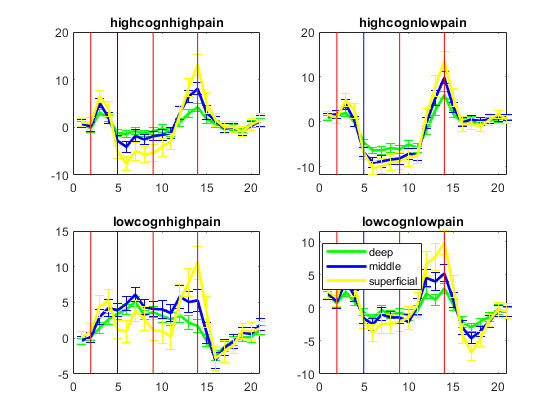

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7349\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7349The number of columns within the funcitonal mask: 769
Subject:7349The percent/number of columns acitvating in each run(t>0) for cognition: 27%/206
Subject:7349The percent/number of columns acitvating in each run(t>0) for pain: 64%/496
Subject:7349The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 19%/143
-------------------------------------------------------------
Subject:7349The number of columns within the funcitonal mask: 769
Subject:7349The percent/number of columns acitvating in each run(t>1) for cognition: 7%/50
Subject:7349The percent/number of columns acitvating in each run(t>1) for pain: 27%/206
Subject:7349The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 2%/19
-------------------------------------------------------------


Subject:7349The number of columns within the funcitonal mask: 1865
Subject:7349The percent/number of columns acitvating in each run(t>0) for cognition: 35%/658
Subject:7349The percent/number of columns acitvating in each run(t>0) for pain: 68%/1265
Subject:7349The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 25%/465
-------------------------------------------------------------
Subject:7349The number of columns within the funcitonal mask: 1865
Subject:7349The percent/number of columns acitvating in each run(t>1) for cognition: 13%/237
Subject:7349The percent/number of columns acitvating in each run(t>1) for pain: 36%/671
Subject:7349The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 6%/113
-------------------------------------------------------------
time for laminar activation:Elapsed time is 4.758951 seconds.
Time for one subject to process:Elapsed time is 4.822864 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7356\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7356The number of columns within the funcitonal mask: 691
Subject:7356The percent/number of columns acitvating in each run(t>0) for cognition: 61%/421
Subject:7356The percent/number of columns acitvating in each run(t>0) for pain: 45%/314
Subject:7356The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 27%/188
-------------------------------------------------------------
Subject:7356The number of columns within the funcitonal mask: 691
Subject:7356The percent/number of columns acitvating in each run(t>1) for cognition: 25%/171
Subject:7356The percent/number of columns acitvating in each run(t>1) for pain: 16%/108
Subject:7356The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/24
-------------------------------------------------------------


Subject:7356The number of columns within the funcitonal mask: 1383
Subject:7356The percent/number of columns acitvating in each run(t>0) for cognition: 58%/807
Subject:7356The percent/number of columns acitvating in each run(t>0) for pain: 47%/649
Subject:7356The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 28%/393
-------------------------------------------------------------
Subject:7356The number of columns within the funcitonal mask: 1383
Subject:7356The percent/number of columns acitvating in each run(t>1) for cognition: 23%/322
Subject:7356The percent/number of columns acitvating in each run(t>1) for pain: 16%/215
Subject:7356The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/51
-------------------------------------------------------------
time for laminar activation:Elapsed time is 3.607962 seconds.
Time for one subject to process:Elapsed time is 3.644379 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7361\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7361The number of columns within the funcitonal mask: 749
Subject:7361The percent/number of columns acitvating in each run(t>0) for cognition: 50%/378
Subject:7361The percent/number of columns acitvating in each run(t>0) for pain: 73%/550
Subject:7361The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 38%/287
-------------------------------------------------------------
Subject:7361The number of columns within the funcitonal mask: 749
Subject:7361The percent/number of columns acitvating in each run(t>1) for cognition: 17%/128
Subject:7361The percent/number of columns acitvating in each run(t>1) for pain: 39%/293
Subject:7361The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 8%/60
-------------------------------------------------------------
Subject:7361The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7375\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7375The number of columns within the funcitonal mask: 699
Subject:7375The percent/number of columns acitvating in each run(t>0) for cognition: 51%/354
Subject:7375The percent/number of columns acitvating in each run(t>0) for pain: 41%/288
Subject:7375The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 24%/171
-------------------------------------------------------------
Subject:7375The number of columns within the funcitonal mask: 699
Subject:7375The percent/number of columns acitvating in each run(t>1) for cognition: 18%/124
Subject:7375The percent/number of columns acitvating in each run(t>1) for pain: 16%/109
Subject:7375The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/26
-------------------------------------------------------------


Subject:7375The number of columns within the funcitonal mask: 1876
Subject:7375The percent/number of columns acitvating in each run(t>0) for cognition: 45%/841
Subject:7375The percent/number of columns acitvating in each run(t>0) for pain: 58%/1080
Subject:7375The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 27%/504
-------------------------------------------------------------
Subject:7375The number of columns within the funcitonal mask: 1876
Subject:7375The percent/number of columns acitvating in each run(t>1) for cognition: 14%/272
Subject:7375The percent/number of columns acitvating in each run(t>1) for pain: 25%/467
Subject:7375The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 5%/85
-------------------------------------------------------------
time for laminar activation:Elapsed time is 4.281071 seconds.
Time for one subject to process:Elapsed time is 4.332349 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7376\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7376The number of columns within the funcitonal mask: 803
Subject:7376The percent/number of columns acitvating in each run(t>0) for cognition: 57%/458
Subject:7376The percent/number of columns acitvating in each run(t>0) for pain: 64%/510
Subject:7376The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 36%/286
-------------------------------------------------------------
Subject:7376The number of columns within the funcitonal mask: 803
Subject:7376The percent/number of columns acitvating in each run(t>1) for cognition: 20%/162
Subject:7376The percent/number of columns acitvating in each run(t>1) for pain: 27%/219
Subject:7376The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 5%/40
-------------------------------------------------------------
Subject:7376The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7383\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7383The number of columns within the funcitonal mask: 864
Subject:7383The percent/number of columns acitvating in each run(t>0) for cognition: 67%/575
Subject:7383The percent/number of columns acitvating in each run(t>0) for pain: 45%/391
Subject:7383The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 28%/239
-------------------------------------------------------------
Subject:7383The number of columns within the funcitonal mask: 864
Subject:7383The percent/number of columns acitvating in each run(t>1) for cognition: 33%/288
Subject:7383The percent/number of columns acitvating in each run(t>1) for pain: 15%/133
Subject:7383The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/31
-------------------------------------------------------------
Subject:7383The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7402\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7402The number of columns within the funcitonal mask: 1475
Subject:7402The percent/number of columns acitvating in each run(t>0) for cognition: 70%/1038
Subject:7402The percent/number of columns acitvating in each run(t>0) for pain: 36%/533
Subject:7402The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 25%/369
-------------------------------------------------------------
Subject:7402The number of columns within the funcitonal mask: 1475
Subject:7402The percent/number of columns acitvating in each run(t>1) for cognition: 34%/503
Subject:7402The percent/number of columns acitvating in each run(t>1) for pain: 9%/130
Subject:7402The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 2%/24
-------------------------------------------------------------
Subject:7402The number of columns within the f

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7403\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7403The number of columns within the funcitonal mask: 792
Subject:7403The percent/number of columns acitvating in each run(t>0) for cognition: 57%/455
Subject:7403The percent/number of columns acitvating in each run(t>0) for pain: 39%/312
Subject:7403The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 23%/181
-------------------------------------------------------------
Subject:7403The number of columns within the funcitonal mask: 792
Subject:7403The percent/number of columns acitvating in each run(t>1) for cognition: 20%/161
Subject:7403The percent/number of columns acitvating in each run(t>1) for pain: 9%/68
Subject:7403The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 2%/17
-------------------------------------------------------------


Subject:7403The number of columns within the funcitonal mask: 1905
Subject:7403The percent/number of columns acitvating in each run(t>0) for cognition: 54%/1028
Subject:7403The percent/number of columns acitvating in each run(t>0) for pain: 43%/816
Subject:7403The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 22%/416
-------------------------------------------------------------
Subject:7403The number of columns within the funcitonal mask: 1905
Subject:7403The percent/number of columns acitvating in each run(t>1) for cognition: 21%/391
Subject:7403The percent/number of columns acitvating in each run(t>1) for pain: 13%/242
Subject:7403The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/48
-------------------------------------------------------------
time for laminar activation:Elapsed time is 4.409432 seconds.
Time for one subject to process:Elapsed time is 4.456905 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7404\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7404The number of columns within the funcitonal mask: 749
Subject:7404The percent/number of columns acitvating in each run(t>0) for cognition: 60%/446
Subject:7404The percent/number of columns acitvating in each run(t>0) for pain: 50%/378
Subject:7404The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 30%/221
-------------------------------------------------------------
Subject:7404The number of columns within the funcitonal mask: 749
Subject:7404The percent/number of columns acitvating in each run(t>1) for cognition: 26%/192
Subject:7404The percent/number of columns acitvating in each run(t>1) for pain: 20%/148
Subject:7404The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 5%/34
-------------------------------------------------------------
Subject:7404The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7405\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7405The number of columns within the funcitonal mask: 738
Subject:7405The percent/number of columns acitvating in each run(t>0) for cognition: 80%/591
Subject:7405The percent/number of columns acitvating in each run(t>0) for pain: 60%/442
Subject:7405The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 48%/353
-------------------------------------------------------------
Subject:7405The number of columns within the funcitonal mask: 738
Subject:7405The percent/number of columns acitvating in each run(t>1) for cognition: 51%/375
Subject:7405The percent/number of columns acitvating in each run(t>1) for pain: 22%/159
Subject:7405The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 11%/80
-------------------------------------------------------------
Subject:7405The number of columns within the fu

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7408\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7408The number of columns within the funcitonal mask: 867
Subject:7408The percent/number of columns acitvating in each run(t>0) for cognition: 62%/537
Subject:7408The percent/number of columns acitvating in each run(t>0) for pain: 43%/370
Subject:7408The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 25%/214
-------------------------------------------------------------
Subject:7408The number of columns within the funcitonal mask: 867
Subject:7408The percent/number of columns acitvating in each run(t>1) for cognition: 25%/218
Subject:7408The percent/number of columns acitvating in each run(t>1) for pain: 13%/117
Subject:7408The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/28
-------------------------------------------------------------
Subject:7408The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7414\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7414The number of columns within the funcitonal mask: 738
Subject:7414The percent/number of columns acitvating in each run(t>0) for cognition: 59%/433
Subject:7414The percent/number of columns acitvating in each run(t>0) for pain: 56%/412
Subject:7414The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 32%/237
-------------------------------------------------------------
Subject:7414The number of columns within the funcitonal mask: 738
Subject:7414The percent/number of columns acitvating in each run(t>1) for cognition: 24%/175
Subject:7414The percent/number of columns acitvating in each run(t>1) for pain: 20%/144
Subject:7414The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 5%/35
-------------------------------------------------------------
Subject:7414The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7415\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7415The number of columns within the funcitonal mask: 777
Subject:7415The percent/number of columns acitvating in each run(t>0) for cognition: 44%/339
Subject:7415The percent/number of columns acitvating in each run(t>0) for pain: 33%/257
Subject:7415The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 16%/124
-------------------------------------------------------------
Subject:7415The number of columns within the funcitonal mask: 777
Subject:7415The percent/number of columns acitvating in each run(t>1) for cognition: 15%/114
Subject:7415The percent/number of columns acitvating in each run(t>1) for pain: 8%/59
Subject:7415The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 1%/7
-------------------------------------------------------------


Subject:7415The number of columns within the funcitonal mask: 1925
Subject:7415The percent/number of columns acitvating in each run(t>0) for cognition: 42%/806
Subject:7415The percent/number of columns acitvating in each run(t>0) for pain: 38%/726
Subject:7415The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 18%/344
-------------------------------------------------------------
Subject:7415The number of columns within the funcitonal mask: 1925
Subject:7415The percent/number of columns acitvating in each run(t>1) for cognition: 13%/255
Subject:7415The percent/number of columns acitvating in each run(t>1) for pain: 11%/204
Subject:7415The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/50
-------------------------------------------------------------
time for laminar activation:Elapsed time is 4.396470 seconds.
Time for one subject to process:Elapsed time is 4.444742 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7425\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7425The number of columns within the funcitonal mask: 615
Subject:7425The percent/number of columns acitvating in each run(t>0) for cognition: 50%/309
Subject:7425The percent/number of columns acitvating in each run(t>0) for pain: 55%/337
Subject:7425The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 32%/195
-------------------------------------------------------------
Subject:7425The number of columns within the funcitonal mask: 615
Subject:7425The percent/number of columns acitvating in each run(t>1) for cognition: 24%/146
Subject:7425The percent/number of columns acitvating in each run(t>1) for pain: 21%/129
Subject:7425The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 8%/49
-------------------------------------------------------------


Subject:7425The number of columns within the funcitonal mask: 1546
Subject:7425The percent/number of columns acitvating in each run(t>0) for cognition: 46%/714
Subject:7425The percent/number of columns acitvating in each run(t>0) for pain: 50%/779
Subject:7425The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 25%/391
-------------------------------------------------------------
Subject:7425The number of columns within the funcitonal mask: 1546
Subject:7425The percent/number of columns acitvating in each run(t>1) for cognition: 17%/260
Subject:7425The percent/number of columns acitvating in each run(t>1) for pain: 18%/277
Subject:7425The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/56
-------------------------------------------------------------
time for laminar activation:Elapsed time is 3.706379 seconds.
Time for one subject to process:Elapsed time is 3.744392 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7426\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7426The number of columns within the funcitonal mask: 896
Subject:7426The percent/number of columns acitvating in each run(t>0) for cognition: 69%/622
Subject:7426The percent/number of columns acitvating in each run(t>0) for pain: 48%/430
Subject:7426The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 33%/296
-------------------------------------------------------------
Subject:7426The number of columns within the funcitonal mask: 896
Subject:7426The percent/number of columns acitvating in each run(t>1) for cognition: 35%/317
Subject:7426The percent/number of columns acitvating in each run(t>1) for pain: 15%/137
Subject:7426The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 5%/46
-------------------------------------------------------------
Subject:7426The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7433\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7433The number of columns within the funcitonal mask: 835
Subject:7433The percent/number of columns acitvating in each run(t>0) for cognition: 46%/385
Subject:7433The percent/number of columns acitvating in each run(t>0) for pain: 51%/423
Subject:7433The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 23%/188
-------------------------------------------------------------
Subject:7433The number of columns within the funcitonal mask: 835
Subject:7433The percent/number of columns acitvating in each run(t>1) for cognition: 15%/127
Subject:7433The percent/number of columns acitvating in each run(t>1) for pain: 17%/146
Subject:7433The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/23
-------------------------------------------------------------


Subject:7433The number of columns within the funcitonal mask: 1461
Subject:7433The percent/number of columns acitvating in each run(t>0) for cognition: 46%/671
Subject:7433The percent/number of columns acitvating in each run(t>0) for pain: 49%/711
Subject:7433The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 23%/332
-------------------------------------------------------------
Subject:7433The number of columns within the funcitonal mask: 1461
Subject:7433The percent/number of columns acitvating in each run(t>1) for cognition: 15%/218
Subject:7433The percent/number of columns acitvating in each run(t>1) for pain: 18%/258
Subject:7433The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/38
-------------------------------------------------------------
time for laminar activation:Elapsed time is 3.894611 seconds.
Time for one subject to process:Elapsed time is 3.942930 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7434\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7434The number of columns within the funcitonal mask: 726
Subject:7434The percent/number of columns acitvating in each run(t>0) for cognition: 75%/548
Subject:7434The percent/number of columns acitvating in each run(t>0) for pain: 60%/432
Subject:7434The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 47%/338
-------------------------------------------------------------
Subject:7434The number of columns within the funcitonal mask: 726
Subject:7434The percent/number of columns acitvating in each run(t>1) for cognition: 36%/258
Subject:7434The percent/number of columns acitvating in each run(t>1) for pain: 22%/162
Subject:7434The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 8%/57
-------------------------------------------------------------
Subject:7434The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7435\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7435The number of columns within the funcitonal mask: 737
Subject:7435The percent/number of columns acitvating in each run(t>0) for cognition: 67%/495
Subject:7435The percent/number of columns acitvating in each run(t>0) for pain: 42%/308
Subject:7435The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 27%/202
-------------------------------------------------------------
Subject:7435The number of columns within the funcitonal mask: 737
Subject:7435The percent/number of columns acitvating in each run(t>1) for cognition: 34%/249
Subject:7435The percent/number of columns acitvating in each run(t>1) for pain: 10%/73
Subject:7435The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/27
-------------------------------------------------------------
Subject:7435The number of columns within the func

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7443\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7443The number of columns within the funcitonal mask: 897
Subject:7443The percent/number of columns acitvating in each run(t>0) for cognition: 62%/552
Subject:7443The percent/number of columns acitvating in each run(t>0) for pain: 57%/515
Subject:7443The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 35%/316
-------------------------------------------------------------
Subject:7443The number of columns within the funcitonal mask: 897
Subject:7443The percent/number of columns acitvating in each run(t>1) for cognition: 26%/236
Subject:7443The percent/number of columns acitvating in each run(t>1) for pain: 23%/205
Subject:7443The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 6%/53
-------------------------------------------------------------
Subject:7443The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7444\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7444The number of columns within the funcitonal mask: 976
Subject:7444The percent/number of columns acitvating in each run(t>0) for cognition: 70%/683
Subject:7444The percent/number of columns acitvating in each run(t>0) for pain: 59%/573
Subject:7444The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 41%/397
-------------------------------------------------------------
Subject:7444The number of columns within the funcitonal mask: 976
Subject:7444The percent/number of columns acitvating in each run(t>1) for cognition: 36%/354
Subject:7444The percent/number of columns acitvating in each run(t>1) for pain: 20%/193
Subject:7444The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 7%/69
-------------------------------------------------------------
Subject:7444The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7445\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7445The number of columns within the funcitonal mask: 692
Subject:7445The percent/number of columns acitvating in each run(t>0) for cognition: 53%/365
Subject:7445The percent/number of columns acitvating in each run(t>0) for pain: 48%/331
Subject:7445The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 23%/159
-------------------------------------------------------------
Subject:7445The number of columns within the funcitonal mask: 692
Subject:7445The percent/number of columns acitvating in each run(t>1) for cognition: 22%/152
Subject:7445The percent/number of columns acitvating in each run(t>1) for pain: 16%/109
Subject:7445The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 2%/13
-------------------------------------------------------------


Subject:7445The number of columns within the funcitonal mask: 1635
Subject:7445The percent/number of columns acitvating in each run(t>0) for cognition: 51%/826
Subject:7445The percent/number of columns acitvating in each run(t>0) for pain: 52%/852
Subject:7445The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 26%/430
-------------------------------------------------------------
Subject:7445The number of columns within the funcitonal mask: 1635
Subject:7445The percent/number of columns acitvating in each run(t>1) for cognition: 19%/303
Subject:7445The percent/number of columns acitvating in each run(t>1) for pain: 17%/275
Subject:7445The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/44
-------------------------------------------------------------
time for laminar activation:Elapsed time is 3.854778 seconds.
Time for one subject to process:Elapsed time is 3.918064 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7448\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7448The number of columns within the funcitonal mask: 980
Subject:7448The percent/number of columns acitvating in each run(t>0) for cognition: 75%/733
Subject:7448The percent/number of columns acitvating in each run(t>0) for pain: 61%/595
Subject:7448The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 48%/466
-------------------------------------------------------------
Subject:7448The number of columns within the funcitonal mask: 980
Subject:7448The percent/number of columns acitvating in each run(t>1) for cognition: 38%/371
Subject:7448The percent/number of columns acitvating in each run(t>1) for pain: 27%/260
Subject:7448The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 12%/113
-------------------------------------------------------------
Subject:7448The number of columns within the f

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7449\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7449The number of columns within the funcitonal mask: 963
Subject:7449The percent/number of columns acitvating in each run(t>0) for cognition: 53%/508
Subject:7449The percent/number of columns acitvating in each run(t>0) for pain: 38%/369
Subject:7449The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 21%/206
-------------------------------------------------------------
Subject:7449The number of columns within the funcitonal mask: 963
Subject:7449The percent/number of columns acitvating in each run(t>1) for cognition: 20%/191
Subject:7449The percent/number of columns acitvating in each run(t>1) for pain: 10%/101
Subject:7449The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 2%/22
-------------------------------------------------------------
Subject:7449The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7452\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7452The number of columns within the funcitonal mask: 866
Subject:7452The percent/number of columns acitvating in each run(t>0) for cognition: 58%/502
Subject:7452The percent/number of columns acitvating in each run(t>0) for pain: 46%/398
Subject:7452The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 26%/225
-------------------------------------------------------------
Subject:7452The number of columns within the funcitonal mask: 866
Subject:7452The percent/number of columns acitvating in each run(t>1) for cognition: 23%/196
Subject:7452The percent/number of columns acitvating in each run(t>1) for pain: 13%/114
Subject:7452The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 2%/19
-------------------------------------------------------------
Subject:7452The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7453\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7453The number of columns within the funcitonal mask: 870
Subject:7453The percent/number of columns acitvating in each run(t>0) for cognition: 48%/416
Subject:7453The percent/number of columns acitvating in each run(t>0) for pain: 53%/465
Subject:7453The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 28%/245
-------------------------------------------------------------
Subject:7453The number of columns within the funcitonal mask: 870
Subject:7453The percent/number of columns acitvating in each run(t>1) for cognition: 17%/148
Subject:7453The percent/number of columns acitvating in each run(t>1) for pain: 16%/141
Subject:7453The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/30
-------------------------------------------------------------
Subject:7453The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7454\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7454The number of columns within the funcitonal mask: 832
Subject:7454The percent/number of columns acitvating in each run(t>0) for cognition: 62%/519
Subject:7454The percent/number of columns acitvating in each run(t>0) for pain: 50%/420
Subject:7454The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 29%/238
-------------------------------------------------------------
Subject:7454The number of columns within the funcitonal mask: 832
Subject:7454The percent/number of columns acitvating in each run(t>1) for cognition: 27%/224
Subject:7454The percent/number of columns acitvating in each run(t>1) for pain: 18%/146
Subject:7454The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/33
-------------------------------------------------------------
Subject:7454The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7455\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7455The number of columns within the funcitonal mask: 748
Subject:7455The percent/number of columns acitvating in each run(t>0) for cognition: 51%/380
Subject:7455The percent/number of columns acitvating in each run(t>0) for pain: 62%/467
Subject:7455The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 31%/231
-------------------------------------------------------------
Subject:7455The number of columns within the funcitonal mask: 748
Subject:7455The percent/number of columns acitvating in each run(t>1) for cognition: 18%/136
Subject:7455The percent/number of columns acitvating in each run(t>1) for pain: 24%/177
Subject:7455The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 5%/34
-------------------------------------------------------------
Subject:7455The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7456\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7456The number of columns within the funcitonal mask: 791
Subject:7456The percent/number of columns acitvating in each run(t>0) for cognition: 53%/421
Subject:7456The percent/number of columns acitvating in each run(t>0) for pain: 42%/336
Subject:7456The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 22%/173
-------------------------------------------------------------
Subject:7456The number of columns within the funcitonal mask: 791
Subject:7456The percent/number of columns acitvating in each run(t>1) for cognition: 22%/177
Subject:7456The percent/number of columns acitvating in each run(t>1) for pain: 12%/96
Subject:7456The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/21
-------------------------------------------------------------


Subject:7456The number of columns within the funcitonal mask: 1393
Subject:7456The percent/number of columns acitvating in each run(t>0) for cognition: 54%/753
Subject:7456The percent/number of columns acitvating in each run(t>0) for pain: 47%/660
Subject:7456The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 24%/338
-------------------------------------------------------------
Subject:7456The number of columns within the funcitonal mask: 1393
Subject:7456The percent/number of columns acitvating in each run(t>1) for cognition: 21%/296
Subject:7456The percent/number of columns acitvating in each run(t>1) for pain: 15%/211
Subject:7456The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 3%/37
-------------------------------------------------------------
time for laminar activation:Elapsed time is 3.669657 seconds.
Time for one subject to process:Elapsed time is 3.712497 seconds.


The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7457\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7457The number of columns within the funcitonal mask: 788
Subject:7457The percent/number of columns acitvating in each run(t>0) for cognition: 61%/480
Subject:7457The percent/number of columns acitvating in each run(t>0) for pain: 49%/383
Subject:7457The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 29%/229
-------------------------------------------------------------
Subject:7457The number of columns within the funcitonal mask: 788
Subject:7457The percent/number of columns acitvating in each run(t>1) for cognition: 26%/205
Subject:7457The percent/number of columns acitvating in each run(t>1) for pain: 18%/138
Subject:7457The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/31
-------------------------------------------------------------
Subject:7457The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7468\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7468The number of columns within the funcitonal mask: 706
Subject:7468The percent/number of columns acitvating in each run(t>0) for cognition: 51%/357
Subject:7468The percent/number of columns acitvating in each run(t>0) for pain: 58%/412
Subject:7468The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 30%/212
-------------------------------------------------------------
Subject:7468The number of columns within the funcitonal mask: 706
Subject:7468The percent/number of columns acitvating in each run(t>1) for cognition: 21%/150
Subject:7468The percent/number of columns acitvating in each run(t>1) for pain: 25%/177
Subject:7468The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 7%/47
-------------------------------------------------------------
Subject:7468The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7469\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7469The number of columns within the funcitonal mask: 648
Subject:7469The percent/number of columns acitvating in each run(t>0) for cognition: 60%/389
Subject:7469The percent/number of columns acitvating in each run(t>0) for pain: 87%/566
Subject:7469The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 52%/338
-------------------------------------------------------------
Subject:7469The number of columns within the funcitonal mask: 648
Subject:7469The percent/number of columns acitvating in each run(t>1) for cognition: 26%/169
Subject:7469The percent/number of columns acitvating in each run(t>1) for pain: 65%/422
Subject:7469The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 16%/103
-------------------------------------------------------------
Subject:7469The number of columns within the f

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7482\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7482The number of columns within the funcitonal mask: 870
Subject:7482The percent/number of columns acitvating in each run(t>0) for cognition: 66%/572
Subject:7482The percent/number of columns acitvating in each run(t>0) for pain: 52%/451
Subject:7482The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 32%/279
-------------------------------------------------------------
Subject:7482The number of columns within the funcitonal mask: 870
Subject:7482The percent/number of columns acitvating in each run(t>1) for cognition: 30%/263
Subject:7482The percent/number of columns acitvating in each run(t>1) for pain: 19%/161
Subject:7482The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 4%/34
-------------------------------------------------------------
Subject:7482The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7484\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7484The number of columns within the funcitonal mask: 794
Subject:7484The percent/number of columns acitvating in each run(t>0) for cognition: 59%/467
Subject:7484The percent/number of columns acitvating in each run(t>0) for pain: 53%/420
Subject:7484The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 30%/241
-------------------------------------------------------------
Subject:7484The number of columns within the funcitonal mask: 794
Subject:7484The percent/number of columns acitvating in each run(t>1) for cognition: 28%/226
Subject:7484The percent/number of columns acitvating in each run(t>1) for pain: 19%/148
Subject:7484The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 6%/44
-------------------------------------------------------------
Subject:7484The number of columns within the fun

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7485\functionalmasks\interimdata_rwls_S1raw.mat


Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Column wise stats are calculated
Subject:7485The number of columns within the funcitonal mask: 765
Subject:7485The percent/number of columns acitvating in each run(t>0) for cognition: 73%/562
Subject:7485The percent/number of columns acitvating in each run(t>0) for pain: 50%/381
Subject:7485The percent/number of columns acitvating in each run(t>0) for cognition AND pain: 36%/274
-------------------------------------------------------------
Subject:7485The number of columns within the funcitonal mask: 765
Subject:7485The percent/number of columns acitvating in each run(t>1) for cognition: 40%/306
Subject:7485The percent/number of columns acitvating in each run(t>1) for pain: 19%/146
Subject:7485The percent/number of columns acitvating in each run(t>1) for cognition AND pain: 7%/56
-------------------------------------------------------------
Subject:7485The number of columns within the fun

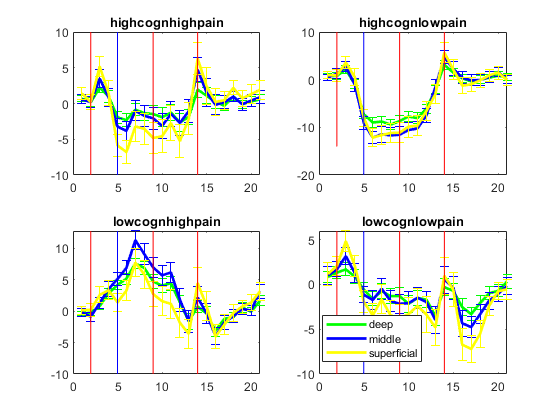


plotidx=0;
subplotsize=[8 4];
allsubjlayer={};
topcolumnnumber=200; %used this previously
layermeans = zeros(20, length(allsubj));

myroiname='S1';
hemisphere={'left' 'right'};
figuretype='raw'; %possible input: 'raw', 'tSNR',
focusofimgs='laminar'; %two possibliities: conditions; laminar
figurelocationpath='C:\Users\lenov\Documents\layerfMRI\E_stats\images\tomanuscipt\firstdrafts\supplementary\rawboldlayerdependentlTS\';% this is now the layer dependency

clustersize=200;%200; %possible values: 200 - top 200 vertices, 0 - all vertices

for hemishperes=1:2
%     figure('Position',[100, 100, 2400, 1200]);
    plotidx=0;
    for subj=allsubj
    %     roipath='C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\';
        rwdtmtrx=loadrawdatamatrix(subj,myroiname);
    %     columnartsfile=[roipath num2str(subj{:}) '\functionalmasks\interimdata_rwls_' myroiname 'raw.mat'];
    %     if exist(columnartsfile,"file")
    %         disp([num2str(subj{:}) ' subject columnar info r'])
    %         plotidx=plotidx+1;
    plotidx=plotidx+1;
%     subplot(5,7,plotidx);
    if clustersize==200
            [columnwisestat,~,~]=BK_layer_sampling_pain_study_pipeline(num2cell(subj),'glmestimate',myroiname,'raw','no','maineff','200'); 
            %(subj,'glmestimate',region,'raw',visualize,typeofcon,selectedcolumns);
            %[S2_200vertices_wholecolumn,procesubjid,columndistr]=layervalues('S2','maineff+int','visualization','no');
    %         allsubjid(plotidx)=subj{:};
    %         allsubjlayer{plotidx}=layerwisestat;
    %         allsubjcoldistr{plotidx}=columndistribution;
    %         allsubjstat{plotidx}=stat;
            [top200Values, top200Indices] =maxk(columnwisestat(hemishperes).T(:,3),topcolumnnumber);
            
            % Filter the indices where the values are positive
            positiveIndices = top200Indices(top200Values > 0);
            % Check if any negative values were removed
%             if length(positiveIndices) < topcolumnnumber
%                 warning('The top 200 values contained negative numbers. Only %d positive values are retained.', length(positiveIndices));
%             end
            
            tmpdata=rwdtmtrx.interimdata_columns{1,2}{hemishperes,1};
            tmpdata=tmpdata(positiveIndices,:,:);

   elseif clustersize==0
            tmpdata=rwdtmtrx.interimdata_columns{1,2}{hemishperes,1};
    end
            myspm=loadtimingfile(subj);
            trialonset=findtrialonset(myspm);
            conditionnms=fieldnames(trialonset);

            %find the values corresponding for trial onset and focus on the
            %-1 to end of trial (which can be between 19 to 22 volumes
            tmpdata_avgroi=squeeze(mean(tmpdata,1));
            idx = {1:7, 8:13, 14:20};
            layersmean = zeros(3, size(tmpdata_avgroi,2), 'like', tmpdata);
            for k = 1:3
                layersmean(k,:) = mean(tmpdata_avgroi(idx{k},:), 1);
            end
            
            %create a layer by timeseries matrix (this is averaged across
            %the 200 vertex pairs)
            roimean_bylayer=layersmean;
            sequencelength=size(roimean_bylayer,2);
            for condition=1:length(conditionnms)
                mycond=conditionnms{condition};
                myvols=trialonset.(mycond);
                condts=cell(3,1);
                for trial=1:length(myvols)
                    myvol=myvols(trial);
                    for mylayers=1:3
                        if (myvol+17)< sequencelength %this has to be put here as one subject has shorter data because of the failure of the measurement.
                            if myvol==1
                                mimi=roimean_bylayer(mylayers,myvol:(myvol+19));
                                mimi=[NaN,mimi];
                                restingperiod=roimean_bylayer(mylayers,(myvol+13):(myvol+19));
                            else
                                %original, no baseline, no percent signal
                                %changecalculation
                                if myvol+19>sequencelength
                                    mimi=roimean_bylayer(mylayers,(myvol-1):end);
                                    while length(mimi)~=21
                                        mimi=[mimi,NaN];
                                    end
                                else
                                    mimi=roimean_bylayer(mylayers,(myvol-1):(myvol+19));
                                end
                                restingperiod=roimean_bylayer(mylayers,(myvol-6):(myvol-1));
                            end
                            %this is the use of a baseline before adding
                            %together the conditions
    %                         restingperiod=roimean((myvol-6):(myvol-1));
                            baslinedmimi=mimi-mean(restingperiod);
                            %this is calculation percent signal change
                            baslinedmimi_percchange=100*(mimi-mean(restingperiod))/std(restingperiod);
                            condts{mylayers}=[condts{mylayers}; baslinedmimi];
                        end
                    end
                end
                
                trialts.(mycond)=condts;

            end
%             noise_std = std(vertexmean, 0, 2);
%             layermean=mean(vertexmean,2);
%             tSNR=layermean./noise_std;
%             if strcmp(figuretype,'raw')
%                 imagedata=layermean;
%             elseif strcmp(figuretype,'tSNR')
%                 imagedata=tSNR;
%             end
%             colourcode.pain_high_cogn_high_pain='-r';
%             colourcode.pain_high_cogn_low_pain='-b';
%             colourcode.pain_low_cogn_high_pain='-.r';
%             colourcode.pain_low_cogn_low_pain='-.b';
%             legend_entries = cell(length(conditionnms), 1);
            for condition=1:length(conditionnms)
                mycond=conditionnms{condition};
                for layeridx=1:3
                    mydata(layeridx,:)=mean(trialts.(mycond){layeridx,1});
                end
%                 line_handles(condition) = plot(mydata, colourcode.(mycond), 'LineWidth', 2,'DisplayName', mycond);
                
%                 hold on
%                 legend_entries{condition} = strrep(mycond(6:end), '_', '');
                grouplvldata(plotidx).(mycond)=mydata;
            end 
%             vline(2,'r'); %this is the start of the pain stimulation, as 0sec is the anticipation (3sec is the forst start of the pain stimulation). The stimulation reaches the plateu with some delay(2sec?), also the canonical HRFis with 5.6 secdelay in the SPM.mat file, so it would mean, the max should be seen 3volume away. 
%             vline(5,'b');
%             vline(9,'r');
%             vline(14,'r');
%             legend(line_handles,legend_entries, 'Location', 'bestoutside', 'Position', [0.92, 0.15, 0.05, 0.7]);
%             
%             title([ 'Subject ' num2str(subj)]);  % add a title to each subplot
%             hold off
%             layermeans(:, plotidx) = imagedata';
    %     else
    %         disp([num2str(subj{:}) ' subject has  no sampled cluster'])
    %     end
    
    end
%     saveas(gcf, [figurelocationpath myroiname hemisphere{hemishperes} 'trialts_' num2str(clustersize) 'vertices_mean_eachsubj_baselined.jpg'], 'jpeg'); % _baselined OR _percsignchange
    
    
    colourcode.deep='-g';
    colourcode.middle='-b';
    colourcode.superficial='-y';
    
    figure;  % create a new figure to visualize the layermean matrix
    layernames={'deep','middle','superficial'};
    legend_entries = cell(length(layernames), 1);
    for condition=1:length(conditionnms)
        mycond=conditionnms{condition};
        for mylayer=1:3
            for mysubj=1:size(grouplvldata,2)
                allsubjdata(mysubj,:)=grouplvldata(mysubj).(mycond)(mylayer,:);
            end
        

            mydata=mean(allsubjdata,1,"omitnan");
            mydatastd=std(allsubjdata,1,"omitnan")/sqrt(size(allsubjdata,1));
            subplot(2,2,condition)
            line_handles(mylayer) = plot(mydata, colourcode.(layernames{mylayer}), 'LineWidth', 2,'DisplayName', mycond);
            hold on 
            errorbar(1:21, mydata, mydatastd, colourcode.(layernames{mylayer}));
    %         errorbar(mydata, std(vertcat(grouplvldata.(mycond)),[],1),  colourcode.(mycond));
            hold on
            legend_entries{mylayer} = layernames{mylayer};
        end
        title(strrep(mycond(6:end), '_', ''))
        vline(2,'r');
        vline(5,'b');
        vline(9,'r');
        vline(14,'r');
        
    end 
    
    legend(line_handles,legend_entries, 'Location', 'best');

%     plot(1:20, mean(layermeans, 2), '-r', 'LineWidth', 1);
%     hold on
%     errorbar(1:20, mean(layermeans, 2), std(layermeans, [], 2), 'k');
%     hold off
%     xlabel('laminar depth (WM to CSF)');
    %     ylabel(' raw BOLD signal');
%     title('Grand average across subjects');
    saveas(gcf, [figurelocationpath myroiname hemisphere{hemishperes} 'trialts_' num2str(clustersize) 'vertices_mean_subjavg_baselined.jpg'], 'jpeg');
end

%%

asd

function rawdatamatrix = loadrawdatamatrix(subjid,roinm)
    % this is a wrapper to load subject level files.
    %   INPUTS:
    %       subjid: the subject ID of the participants (character array or numeric)
    %       roinm: the selected ROI name - possible options S1, S2, pIns,
    %       DLPFC
    if ~ischar(subjid)
        subjid = num2str(subjid);
    end
    filpath=['C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\' subjid '\functionalmasks\interimdata_rwls_' roinm 'raw.mat'];
    disp(['The loaded file path:' filpath])
    rawdatamatrix=load(filpath);


end

function SPMfile = loadtimingfile(subid)
    if subid <= 7405
        subpath = 'E:/pain_layers/main_project/derivatives/pipeline/';
    else
        subpath = 'D:/main_project/derivatives/pipeline/';
    end
    statspath = dir([subpath num2str(subid) '/ses-02/func/layers/rwls_stats_compcor_UNsmoothed_hpf180']);
    SPMfile = load([statspath(1).folder '/SPM.mat'],'SPM');
end

function trialvol = findtrialonset(myspm)
    conditionnms = {'pain_high_cogn_high_pain';
                    'pain_high_cogn_low_pain';
                    'pain_low_cogn_high_pain';
                    'pain_low_cogn_low_pain'};
    
    trialvol=struct();
    for condition=1:4 %the number of conditions
        condinquestion=conditionnms{condition};
%         idx=find(contains(myspm.SPM.xX.name, condinquestion));
        trialvolumestart=[];
        for run=1:3 %there is always three runs
            %this is necessary bc the first few subjects have no fixed length
            %run length, but we stopped manually.
            
            idx=strcmp(vertcat(myspm.SPM.Sess(run).U.name),condinquestion);
            trialvolumestartinrun=round(myspm.SPM.Sess(run).U(idx).ons)/3;
            if run==2
                lengthofrun1=length(myspm.SPM.Sess(1).row);
                trialvolumestartinrun=trialvolumestartinrun+lengthofrun1;
            elseif run==3
                lengthofrun12=length(myspm.SPM.Sess(1).row)+length(myspm.SPM.Sess(2).row);
                trialvolumestartinrun=trialvolumestartinrun+lengthofrun12;
            end
            
    
            trialvolumestart=[trialvolumestart; trialvolumestartinrun];
        end
        trialvol.(condinquestion)=trialvolumestart;
    end

end